clear all;
close all;
clc;

% % 25/04 CSHA S1 combined data
% % cut and align the neural activity based on task event written by NY
% Animal = {'tph312','tph312','tph312','tph312','tph312','tph314','tph314','tph314','tph314','tph314','tph314','tph316','tph316','tph316','tph316','tph316','tph316','tph317','tph317','tph317','tph317','tph317','tph317', ...
%     'rbp4c1173','rbp4c1173','rbp4c1173','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174', ...
%     'tph574','tph574','tph574','tph578','tph578','tph578'}; %{'tph189','tph199','tph209','tph218','tph228'}; %{'tph189','tph199','tph209','tph218','tph228'};
% % Animal = {'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'};
% Date = {'20240410','20240412','20240414','20240415','20240416','20240410','20240412','20240413','20240414','20240415','20240416','20240320','20240401','20240402','20240403','20240404','20240405','20240315','20240316','20240317','20240318','20240320','20240321', ...
%     '20250213','20250215','20250217','20250207','20250208','20250213','20250215','20250217','20250218', ...
%     '20250414','20250415','20250416','20250414','20250415','20250416'}; %{'20230421','20230530','20230817','20230817','20230817'};
% % Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715'};
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving', ...
%     'roving','roving','roving','roving','roving','roving','roving','roving','roving', ...
%     'roving','roving','roving','roving','roving','roving'}; %{'light90','light90','light90h','light90h','light90h'};
% % Key = {'switching','switching','switching','switching','switching','switching'};
% cellset_num = {0,1,2,3,4,0,1,2,3,4,5,0,1,2,3,4,5,0,1,2,3,4,5, ...
%     -1,-1,-1,-1,-1,-1,-1,-1,-1, ...
%     -1,-1,-1,-1,-1,-1}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
% % cellset_num = {0,1,2,3,4,5};
% categorize = 'layer'; %'depth'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219], ...
%     [1200,1200,1200],[0,0,0],[1200,1200,1200],[0,0,0],[1200,1200,1200],[1200,1200,1200],[0,0,0],[1200,1200,1200],[1200,1200,1200], ...
%     [240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440]}%[left, center,right] of the
% %     Inscopix imaging FOV 
% Kota_alignment = 1; %0: do not use, 1:use
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504_CSHA\20250419_S1_combined';
% % need to be fixed because reverse pattern is different between tph189 and tph199
% image_reverse = {2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2, ...
%     0,0,0,0,0,0,0,0,0, ...
%     4,4,4,4,4,4}; %{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, 2: 2024 S1, 3:2024 M1
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202504_CSHA';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250418_\'];


% % 25/04/14-16 Yuzhe-san data
% % cut and align the neural activity based on task event written by NY
% Animal = {'tph574','tph574','tph574','tph578','tph578','tph578'}; %{'tph189','tph199','tph209','tph218','tph228'};
% % Animal = {'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'};
% Date = {'20250414','20250415','20250416','20250414','20250415','20250416'}; %{'20230421','20230530','20230817','20230817','20230817'};
% % Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715'};
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving'}; %{'light90','light90','light90h','light90h','light90h'};
% % Key = {'switching','switching','switching','switching','switching','switching'};
% cellset_num = {-1,-1,-1,-1,-1,-1}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
% % cellset_num = {0,1,2,3,4,5};
% categorize = 'layer'; %'depth'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440]};
% %     Inscopix imaging FOV 
% Kota_alignment = 1; %0: do not use, 1:use
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504\250414-16_roving_all_thres25\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199
% image_reverse = {4,4,4,4,4,4}; %{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, 2: 2024 S1, 3:2024 M1
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202504';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250418_Yuzhe\'];

% % 25/05 S1 Yuzhe-san data for single animal test run
% Animal = {'C6J501'}; %{'tph574'}; 
% Date = {'20250703'}; %{'20250513'}; 
% totalTrial = 200; %150;
% Key = {''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% cellset_num = {-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[240,280,340,380,380]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% %     Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 2; % 0:all time or 1: only during trial force & position eta, 2:first index in each trial
% % 3: last force idx in each trial, 4: last force idx of CoM trial 
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = {4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202506_Abo'; %'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\'];

% % 25/05 Yuzhe-san S1 data for single animal test run
% Animal = {'tph574','tph574','tph574','tph574','tph574','tph574','tph574','tph574','tph578','tph578','tph578','tph578','tph578','tph578','tph578','tph578'}; %'tph199';'tph209'
% Date = {'20250513','20250514','20250515','20250516','20250517','20250518','20250519','20250520','20250513','20250514','20250515','20250516','20250517','20250518','20250519','20250520'}; %'20240414'; % '20230602';'20230827'
% totalTrial = 200; %150;
% Key = {'','','','','','','','','','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],...
%     [200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% %     Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 4; % 0:all time or 1: only during trial force & position eta, 2:first index in each trial
% %3: last force idx in each trial, 4: last force idx of CoM trial
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = {4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\251102_tph574_578\'];

% 25/07 S1 Yuzhe-san & Abo-kun data for multi animals
% Animal = {'tph578','tph578','tph578','tph578','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J506','C6J506','C6J506'};
Animal = {'tph578','tph578','tph578','tph578','tph578','tph578','tph578','tph578','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506'}; %{'tph574'}; 
% Date = {'20250514','20250516','20250518','20250520','20250704','20250708','20250710','20250711','20250715','20250717','20250725','20250730','20250801'};
Date = {'20250513','20250514','20250515','20250516','20250517','20250518','20250519','20250520','20250703','20250704','20250707','20250708','20250709','20250710','20250711','20250714','20250715','20250716','20250717','20250718','20250723','20250724','20250725','20250728','20250729','20250730','20250731','20250801','20250804','20250805'}; %{'20250513'}; 
totalTrial = 200; %150;
% Key = {'','','','','','','','','','','','',''}; 
Key = {'','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1};
cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],...
%     [314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],...
%     [345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148]};
layer_bounds_um = {[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],...
    [314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],...
    [345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
%     Inscopix imaging FOV % tph199:[247; 433; 358] 
Kota_alignment = 0; %0: do not use, 1:use
GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
inside_trial_eta = 1; % 0:all time or 1: only during trial force & position eta, 2:first index in each trial
% 3: last force idx in each trial, 4: last force idx of CoM trial 
% Define the folder where the CSV files are located
pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = {4,4,4,4,0,0,0,0,0,0,0,0,0};
image_reverse = {4,4,4,4,4,4,4,4,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
data_parent_dir = 'E:\Nao_behavior\202506_Abo'; %'E:\Nao_behavior\202506';
output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\'];

% plot event triggered neural activity
force_thr = 25;
position_thr = 10;
fps = 10;
before_event = 2; %1;
after_event  = 4; %2;
norm = 2; %0:no normalization or 1:normalization or 2:z scored or 3:z scored and take only significantly changed cell 
% 4:z scored by compared trials 5: z scored and align with train data
% (half) and plot with test data (half) 6: z scored by before pull neural
% activity
% ランダムシードを設定
rng(1);

% % 25/02 motor cortex data
% % cut and align the neural activity based on task event written by NY
% Animal = {'rbp4c1173','rbp4c1173','rbp4c1173','rbp4c1173','rbp4c1173','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174'}; %{'tph189','tph199','tph209','tph218','tph228'};
% % Animal = {'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'};
% Date = {'20250210','20250212','20250214','20250216','20250218','20250210','20250211','20250214','20250216'}; %{'20230421','20230530','20230817','20230817','20230817'};
% % Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715'};
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving','roving','roving','roving'}; %{'light90','light90','light90h','light90h','light90h'};
% % Key = {'switching','switching','switching','switching','switching','switching'};
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
% % cellset_num = {0,1,2,3,4,5};
% categorize = 'layer'; %'depth'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[0,0,0],[1200,1200,1200],[1200,1200,1200],[0,0,0],[1200,1200,1200],[0,0,0],[1200,1200,1200],[1200,1200,1200],[0,0,0]};
% %     Inscopix imaging FOV 
% Kota_alignment = 1; %0: do not use, 1:use
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202502_2photon\2502_2photon_M1_roving_all_thres25\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199
% image_reverse = {0,0,0,0,0,0,0,0,0}; %{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, 2: 2024 S1, 3:2024 M1
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202502_2photon';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250415_2photon\'];

% % 25/02 sensory cortex data
% % cut and align the neural activity based on task event written by NY
% Animal = {'rbp4c1173','rbp4c1173','rbp4c1173','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174'}; %{'tph189','tph199','tph209','tph218','tph228'};
% % Animal = {'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'};
% Date = {'20250213','20250215','20250217','20250207','20250208','20250213','20250215','20250217','20250218'}; %{'20230421','20230530','20230817','20230817','20230817'};
% % Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715'};
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving','roving','roving','roving'}; %{'light90','light90','light90h','light90h','light90h'};
% % Key = {'switching','switching','switching','switching','switching','switching'};
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
% % cellset_num = {0,1,2,3,4,5};
% categorize = 'layer'; %'depth'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[1200,1200,1200],[0,0,0],[1200,1200,1200],[0,0,0],[1200,1200,1200],[1200,1200,1200],[0,0,0],[1200,1200,1200],[1200,1200,1200]};
% %     Inscopix imaging FOV 
% Kota_alignment = 1; %0: do not use, 1:use
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202502_2photon\2502_2photon_S1_roving_all_thres25\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199
% image_reverse = {0,0,0,0,0,0,0,0,0}; %{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, 2: 2024 S1, 3:2024 M1
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202502_2photon';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250415_2photon\'];

% % 24/04 sensory cortex data
% % cut and align the neural activity based on task event written by NY
% Animal = {'tph312','tph312','tph312','tph312','tph312','tph314','tph314','tph314','tph314','tph314','tph314','tph316','tph316','tph316','tph316','tph316','tph316','tph317','tph317','tph317','tph317','tph317','tph317'}; %{'tph189','tph199','tph209','tph218','tph228'};
% % Animal = {'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'};
% Date = {'20240410','20240412','20240414','20240415','20240416','20240410','20240412','20240413','20240414','20240415','20240416','20240320','20240401','20240402','20240403','20240404','20240405','20240315','20240316','20240317','20240318','20240320','20240321'}; %{'20230421','20230530','20230817','20230817','20230817'};
% % Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715'};
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving'}; %{'light90','light90','light90h','light90h','light90h'};
% % Key = {'switching','switching','switching','switching','switching','switching'};
% cellset_num = {0,1,2,3,4,0,1,2,3,4,5,0,1,2,3,4,5,0,1,2,3,4,5}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
% % cellset_num = {0,1,2,3,4,5};
% categorize = 'layer'; %'depth'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219]}%[left, center,right] of the
% %     Inscopix imaging FOV 
% Kota_alignment = 1; %0: do not use, 1:use
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'C:\Users\Naohiro\Documents\Inscopix_Projects\tph312_314_316_317_thres25\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199
% image_reverse = {2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2}; %{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, 2: 2024 S1, 3:2024 M1
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202403';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250420\'];

% % 24/07 motor cortex data
% % cut and align the neural activity based on task event written by NY
% Animal = {'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'}; %{'tph189','tph199','tph209','tph218','tph228'};
% Animal = {'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'};
% Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715', '20240710', '20240711', '20240712', '20240713', '20240714', '20240715', '20240710', '20240711', '20240712', '20240713', '20240714', '20240715', '20240710', '20240711', '20240712', '20240713', '20240714', '20240715'}; %{'20230421','20230530','20230817','20230817','20230817'};
% Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715'};
% totalTrial = 150;
% Key = {'switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching'}; %{'light90','light90','light90h','light90h','light90h'};
% Key = {'switching','switching','switching','switching','switching','switching'};
% cellset_num = {0,1,2,3,4,5,0,1,2,3,4,5,0,1,2,3,4,5,0,1,2,3,4,5}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
% cellset_num = {0,1,2,3,4,5};
% categorize = 'layer'; %'depth'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[363, 498, 399],[363, 498, 399],[363, 498, 399],[363, 498, 399],[363, 498, 399],[363, 498, 399],[431, 529],[431, 529],[431, 529],[431, 529],[431, 529],[431, 529],[191, 249, 303, 380, 412, 434],[191, 249, 303, 380, 412, 434],[191, 249, 303, 380, 412, 434],[191, 249, 303, 380, 412, 434],[191, 249, 303, 380, 412, 434],[191, 249, 303, 380, 412, 434],[297, 360, 332, 245, 430, 343],[297, 360, 332, 245, 430, 343],[297, 360, 332, 245, 430, 343],[297, 360, 332, 245, 430, 343],[297, 360, 332, 245, 430, 343],[297, 360, 332, 245, 430, 343]}%[left, center,right] of the
%     Inscopix imaging FOV 
% Kota_alignment = 1; %0: do not use, 1:use
% Define the folder where the CSV files are located
% pullAlignFolderPath = 'C:\Users\Naohiro\Documents\Inscopix_Projects\Rbp4c867_875_878_879_switching_thres25\output';
% need to be fixed because reverse pattern is different between tph189 and tph199
% image_reverse = {3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3}; %{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, 2: 2024 S1, 3:2024 M1
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202407';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250418_Yuzhe\'];

% pullAlignFolderPath = '/home/naohiro/Documents/Inscopix_Projects/Rbp4c867_875_878_879_switching_thres25/output';
% working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022/';
% output_parent_dir = ['/home/naohiro/Desktop/Doya_rotation/analysis/output/241004/']; %['/home/naohiro/Desktop/Doya_rotation/analysis/output/230913/imaging_multi/'];
% data_parent_dir = '/media/naohiro/Volume/Nao_behavior/202407';
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
% data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation/202308'  filesep Date '_' Animal '_' Key]; % Linux
% image_reverse = {3,3,3,3,3,3};
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
% layer_bounds_um = {[297, 360, 332, 245, 430, 343], [297, 360, 332, 245, 430, 343], [297, 360, 332, 245, 430, 343], [297, 360, 332, 245, 430, 343], [297, 360, 332, 245, 430, 343], [297, 360, 332, 245, 430, 343]};


% uniqueDateとuniqueAnimalを取得
uniqueDate = unique(Date);
uniqueAnimal = unique(Animal);

% Outputパスのフォルダ名を生成
folder_name = [strrep(strjoin(uniqueAnimal),' ','_') '_norm' num2str(norm)];
% folder_name = [strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_norm' num2str(norm)];

% 新しいフォルダのパスを作成
output_dir = fullfile(output_parent_dir, folder_name);

% フォルダが存在しない場合は作成
if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

% パスの最後に'/'を追加
if ~endsWith(output_dir, '/')
    output_dir = [output_dir '/'];
end

% フォルダ作成およびパスを表示
disp(['フォルダが作成されました: ' output_dir]);

フォルダが作成されました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\C6J501_C6J506_tph578_norm2/


% save parameters

% ファイル名を生成
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_norm' num2str(norm) '_parameter.json'];
filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_norm' num2str(norm) '_parameter.json'];

% パラメータを構造体としてまとめる
params.Animal = Animal;
params.Date = Date;
params.totalTrial = totalTrial;
params.Key = Key;
params.cellset_num = cellset_num;
params.categorize = categorize;
params.layer_bounds_um = layer_bounds_um;
params.Kota_alignment = Kota_alignment;
params.pullAlignFolderPath = pullAlignFolderPath;
params.image_reverse = image_reverse;
params.working_directory = working_directory;
params.output_dir = output_dir;
params.data_parent_dir = data_parent_dir;
params.force_thr = force_thr;
params.position_thr = position_thr;
params.fps = fps;
params.before_event = before_event;
params.after_event = after_event;
params.norm = norm;
params.inside_trial_eta = inside_trial_eta;

% JSONファイルとして保存
jsonText = jsonencode(params);
fid = fopen(filename, 'w');
if fid == -1
    error('ファイルを開くことができませんでした。');
end
fwrite(fid, jsonText, 'char');
fclose(fid);

disp(['パラメータが保存されました: ' filename]);

パラメータが保存されました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\C6J501_C6J506_tph578_norm2/C6J501_C6J506_tph578_norm2_parameter.json


data_folders = cell(1,length(Animal));
% data_folders = [];
acc_neural_activity_data_all_sessions = cell(1,length(Animal));
acc_neural_property_data_all_sessions = cell(1,length(Animal));
trial_sessions          = cell(1,length(Animal));
resistance_sessions     = cell(1,length(Animal));
pushCorrect_sessions    = cell(1,length(Animal));
pushResistance_sessions = cell(1,length(Animal));
pullResistance_sessions = cell(1,length(Animal));
pushReward_sessions     = cell(1,length(Animal));
% correspondences_table = cell(length(Animal));
for i = 1:length(Animal)
    if i <=8 %temporal operation
       data_folders(i) = {['E:\Nao_behavior\202506' filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    else
        data_folders(i) = {['E:\Nao_behavior\202506_Abo' filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    end
    % data_folders(i) = {[data_parent_dir filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat']);    
    neural_activity_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces.csv'],'NumHeaderLines',0);
    neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
    neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces-props.csv']);
    neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
    if cellset_num{i} == -1
        acc_neural_activity_data = neural_activity_data(:,strcmp(table2array(neural_property_table(:,'Status')),'accepted'));
        acc_neural_property_data = neural_property_data(strcmp(table2array(neural_property_table(:,'Status')),'accepted'),:);
        acc_neural_activity_data_all_sessions{i} = acc_neural_activity_data;
        acc_neural_property_data_all_sessions{i} = acc_neural_property_data;
    else
        if contains(Key,'roving')
            all_neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
            correspondences_table = readtable([strjoin(data_folders(i)) filesep 'correspondences_table_roving_0.5.csv']);
        elseif contains(Key,'switching')
            all_neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces_switching-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
            correspondences_table = readtable([strjoin(data_folders(i)) filesep 'correspondences_table_switching_0.5.csv']);         
        else
            all_neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
            correspondences_table = readtable([strjoin(data_folders(i)) filesep 'correspondences_table_ordinary_0.5.csv']);
        end
        cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==int32(cell2mat(cellset_num(i))),:);
        %%% have to return the line below %%%
        global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
        % global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'undecided'));
        local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
        acc_neural_activity_data = neural_activity_data(:,local_acc_idx+1);
        acc_neural_property_data = neural_property_data(local_acc_idx+1,:);
        acc_neural_activity_data_all_sessions{i} = acc_neural_activity_data;
        acc_neural_property_data_all_sessions{i} = acc_neural_property_data;
    end
    %     load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat']);
    %     data(i,:) = behavior_sequence_fps;
    % save table as mat file %%%have to change!variable names are different
    % save([strjoin(data_folders(i)) filesep Animal(i) '_neural_activity_' Date(i) '_' Key(i) '.mat'], 'acc_neural_activity_data', 'acc_neural_property_data');    
    trial_sessions{i}          = behavior_neural_time(:,2);
    resistance_sessions{i}     = behavior_neural_time(:,5);
    pushCorrect_sessions{i}    = pushCorrect;
    pushResistance_sessions{i} = pushResistance;
    pullResistance_sessions{i} = pullResistance;
    pushReward_sessions{i}     = pushReward;
    save([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_neural_activity_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat'], 'acc_neural_activity_data', 'acc_neural_property_data');
end

% % neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);
% % neural_activity_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces.csv'],'NumHeaderLines',0);
% neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
% neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
% % neural_property_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces-props.csv']);
% neural_property_table = readtable([data_folder filesep 'cell_traces-props.csv']);
% neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
% if contains(Key,'roving')
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_roving_0.5.csv']);
% else
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_ordinary_0.5.csv']);
% end
% % all_neural_property_table = readtable([data_folder filesep 'all_cell_traces-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
% % correspondences_table = readtable([data_folder filesep 'correspondences_table_0.5.csv']); %correspondences_table_ordinary_0.5
% cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==cellset_num,:);
% %%% have to return the line below %%%
% global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
% % global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'undecided'));
% local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
% acc_neural_activity_data = neural_activity_data(:,local_acc_idx+1);
% acc_neural_property_data = neural_property_data(local_acc_idx+1,:);
% % acc_neural_activity_data = neural_activity_data(:,strcmp(table2array(neural_property_table(:,'Status')),'accepted'));
% % acc_neural_property_data = neural_property_data(strcmp(table2array(neural_property_table(:,'Status')),'accepted'),:);

sum(strcmp(table2array(neural_property_table(:,'Status')),'accepted'))

ans = 442

strcmp(neural_property_table(:,'Status'),'accepted')

ans = logical
   0


acc_neural_activity_data_all_sessions{1}

ans =    12.8408   27.3620    5.7939   24.3597   26.0793   10.8015    7.4817    2.9773   37.9037   11.5953    7.6622    5.5254   23.1812   -0.4079    6.4115    4.5125   10.0259    6.9447    2.6570    6.3164   18.4762   36.3244    3.7266    7.2499   -1.2319    4.7605    2.2479   23.9036    3.9358   18.1774    9.2520   24.6822   12.0687   -1.2140   -1.5705    6.1307   23.5875   -4.7173   16.0659    7.6408   11.0192   48.6715   23.7857    1.4303   13.6725    8.3303   -5.5958    3.4557    9.4841    1.0560
   10.9754   28.1686    3.9646   22.6374   25.9189   10.6168    9.3943    2.3517   37.9158   11.2444    7.8611    4.1805   23.1258    0.4052    6.6473    3.9019    9.9175    7.6087    1.5801    5.8919   19.1270   34.1568    4.5505    6.3313   -2.8484    4.5799    2.8444   25.3504    5.3796   18.7885    7.8167   24.9747   12.5166    0.6221    1.7601    6.3061   24.1401   -2.8491   17.7217    8.4777    9.5289   48.2407   24.4499    2.0069   15.5390    6.1951   -5.1666    3.4664   10.7714   

acc_neural_property_data_all_sessions{1}

ans =   255.0000  255.0000  255.0000   43.0000   68.0000    1.0000    7.8102    1.0000
  255.0000  255.0000  255.0000   48.0000   67.0000    1.0000    8.6023    1.0000
  255.0000  255.0000  255.0000  115.0000   57.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000  106.0000   27.0000    1.0000    7.2801    1.0000
  255.0000  255.0000  255.0000  120.0000   50.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000  115.0000   50.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000  109.0000   61.0000    1.0000    7.2111    1.0000
  255.0000  255.0000  255.0000  126.0000   60.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000  119.0000   67.0000    1.0000    8.2462    1.0000
  255.0000  255.0000  255.0000  120.0000   60.0000    1.0000    7.2111    1.0000


if Kota_alignment == 1    
    % Get a list of all CSV files in the folder
    csvFiles = dir(fullfile(pullAlignFolderPath, '*.csv'));
    
    % Initialize an empty cell array to store the matrices
    AlinmentTimingCells = {};
    
    % Loop through each CSV file and read the data
    for k = 1:length(csvFiles)
        % Get the full file name and read the CSV file
        fileName = fullfile(pullAlignFolderPath, csvFiles(k).name);
        data = table2array(readtable(fileName));
        
        % Store the data in the cell array
        AlinmentTimingCells{k} = data;
    end
end

% % plot neural activity
% % addpath([working_directory 'PCA_and_ICA\Subaxis']);
% ylimit=[0 50];
% mean_acc_neural_activity = mean(acc_neural_activity_data,2);
% figure
% % for i = 1:size(acc_neural_activity_data,2)
% %     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
%     for j = 1:size(acc_neural_activity_data,2)
%         hold on 
%         r = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,j));
%         hold off
%     end
%     alpha(r,0.1);
%     hold on
%     b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,mean_acc_neural_activity);
% %     title([brain_roi_name(i)], 'FontSize',6);
%     ylim(ylimit); 
%     ylabel('neural activity');
%     xlabel('time (sec)')
% 
% % end
% % saveas(gcf,[output_dir Animal '_' num2str(ylimit(2)) '_all_activity.png']);

uniqueDate = unique(Date);
uniqueAnimal = unique(Animal);
% % タイトルの長さをチェックし、条件に応じて変更
% max_title_length = 100; % タイトルの最大許容長さを設定
% if length(original_title) > max_title_length
%     new_title = 'default_activity_heatmap.png'; % タイトルが長すぎる場合の代替タイトル
% else
%     new_title = original_title; % タイトルが許容範囲内ならオリジナルのタイトルを使用
% end

% % plot neural activity heatmap
% addpath([working_directory 'Utility' filesep 'Subaxis']);
% climit = [0 50]
% figure
% set(gcf,'color','w');
% for i = 1:length(Animal) 
%     subaxis(length(Animal),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.06);
%     clims = climit;
%     image = transpose(acc_neural_activity_data{i});
% %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
%     imagesc(0:0.1:(size(acc_neural_activity_data{i},1)-1)/10,1:size(acc_neural_activity_data{i},2),image,clims);
% %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
%     ylabel('cell');
%     xlabel('time (sec)');
% end
% 
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_' strrep(strjoin(uniqueAnimal),' ','_') '_all_activity_heatmap.png'];
% 
% saveas(gcf,filename);
% % close all;

% addpath([working_directory 'Utility' filesep 'Subaxis']);
% example_num = 5;
% display_start = 1; %113;
% ylimit=[0 150];
% figure
% for j = 1:length(Animal)
%     for i = 1:example_num
%         subaxis(example_num,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
%         b = plot(0:0.1:(size(acc_neural_activity_data{j},1)-1)/10,acc_neural_activity_data{j}(:,display_start+i));
%     %     title([brain_roi_name(i)], 'FontSize',6);
%         ylim(ylimit); 
%         xlim([0 (size(acc_neural_activity_data{j},1)-1)/10]);
%         xlabel('');
%         ylabel('');
% %         axis off;
%         box off;
%     %     ylabel('neural activity');
%     %     xlabel('time (sec)')
%     end
% end
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_exmple_activity_traces.png'];
% saveas(gcf,filename);

% 0:0.1:(size(acc_neural_activity_data,2)-1)/10

% % plot event triggered neural activity
% force_thr = 50;
% position_thr = 10;
% fps = 10;
% before_event = 2; %1;
% after_event  = 4; %2;
% norm = 2; %0:no normalization or 1:normalization or 2:z scored or 3:z scored and take only significantly changed cell
% 
% % for i = 1:length(Animal)
% %     load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(j)) '.mat']);
% % end

% j=1;
% load([strjoin(data_folders(j)) filesep strjoin(Animal(j)) '_behavior_' strjoin(Date(j)) '_' strjoin(Key(j)) '.mat']);
% var_list = who('-file' ,[strjoin(data_folders(j)) filesep strjoin(Animal(j)) '_behavior_' strjoin(Date(j)) '_' strjoin(Key(j)) '.mat']);
% % var_list = who -file /media/naohiro/ADATA HV620S/Doya_rotation/202308/20230819_tph228_heavy90h/tph228_behavior_20230819_heavy90h.mat
% disp(var_list);

% % plot example neural activity with behaviors
% addpath([working_directory 'Utility' filesep 'Subaxis']);
% example_num = 5;
% display_start = 1; %113;
% ylimit=[0 150];
% range_max =1000;
% figure
% for j = 1:length(Animal)
%     load([strjoin(data_folders(j)) filesep strjoin(Animal(j)) '_behavior_' strjoin(Date(j)) '_' strjoin(Key(j)) '.mat']);
%     for i = 1:example_num
%         subaxis(example_num+3,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
%         b = plot(0:0.1:(range_max-1)/10,acc_neural_activity_data{j}(1:range_max,display_start+i));
%     %     title([brain_roi_name(i)], 'FontSize',6);
%         ylim(ylimit); 
%         xlim([0 (range_max-1)/10]);
%         xlabel('');
%         ylabel('');
% %         axis off;
%         box off;
%         %     ylabel('neural activity');
%     %     xlabel('time (sec)')
%     end
% 
%     for i = 1:3
%         subaxis(example_num+3,length(Animal),2*(i+example_num)+j-2, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
%         normalized_behavior = normalize_rows(transpose(behavior_neural_time(1:range_max,5+i)));
%         b = plot(0:0.1:(range_max-1)/10,normalized_behavior);
%     %     title([brain_roi_name(i)], 'FontSize',6);
%         ylim([-0.2 1.2]); 
%         xlim([0 (range_max-1)/10]);
%         xlabel('');
%         ylabel('');
% %         axis off;
%         box off;
%     %     ylabel('neural activity');
%     %     xlabel('time (sec)')
%     end
% end
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_exmple_activity_behavior_traces.png'];
% saveas(gcf,filename);

% Calc cell depth from pixel value
% image_reverse = 0; %0: tph199 type orientation, 1: arc247 type orientation
depth = cell(1,length(Animal));
if strcmp(categorize, 'depth') == 1
    for i = 1:length(Animal)        
        if image_reverse{i} == 0
            depth{i} = 1050 - acc_neural_property_data_all_sessions{i}(:,4)*1050/(1280/4);    %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
        elseif image_reverse{i} == 1
            depth{i} = 1050 - acc_neural_property_data_all_sessions{i}(:,4)*1050/(1280/4); 
        else
            depth{i} = acc_neural_property_data_all_sessions{i}(:,4)*1050/(1280/4);
    %     depth = 1100 - acc_neural_property_data(:,4)*1000/(1066/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
        end
    end
    depth_conc = depth{1};
    for i_animal = 2:length(Animal)
        depth_conc = vertcat(depth_conc, depth{i_animal});
    end
end

% determine which layer each cell belong by cell position
if strcmp(categorize, 'layer') == 1
    pointAreas_all_sessions = cell(1,length(Animal));
    for i = 1:length(Animal)
    %     layer_bounds_um = [140;250;260]; %[left, center,right] of the
    %     Inscopix imaging FOV
        layer_bounds_pix = layer_bounds_um{i} * (1280/4) /1050; 
        layer_bounds_len = length(layer_bounds_pix);
        x_pix = linspace(1, 200, layer_bounds_len);
        % y axis:acc_neural_property_data(:,4), x axis:acc_neural_property_data(:,5)
        % TODO: have to be reverse y axis and x axis depending on the orientation of
        % the image
        if image_reverse{i} == 0
            neural_locations = [acc_neural_property_data_all_sessions{i}(:,5), acc_neural_property_data_all_sessions{i}(:,4)];
        elseif image_reverse{i} == 1
            % reverse layer_bounds_pix
            % layer_bounds_pix = flip(layer_bounds_pix)
            neural_locations = [800/4 - acc_neural_property_data_all_sessions{i}(:,5), acc_neural_property_data_all_sessions{i}(:,4)];                   
        elseif image_reverse{i} == 2
            neural_locations = [800/4 - acc_neural_property_data_all_sessions{i}(:,5), 1280/4 - acc_neural_property_data_all_sessions{i}(:,4)];        
        elseif image_reverse{i} == 3
            neural_locations = [acc_neural_property_data_all_sessions{i}(:,5), 1280/4 - acc_neural_property_data_all_sessions{i}(:,4)];           
        elseif image_reverse{i} == 4
            neural_locations = [acc_neural_property_data_all_sessions{i}(:,4), 800/4 - acc_neural_property_data_all_sessions{i}(:,5)];    
            x_pix = linspace(1, 320, layer_bounds_len);
        end
        %reshape neural_locations to N*2
        % combine x_pix and layer_bounds_pix to 3*2
        linePoints = [x_pix(:), layer_bounds_pix(:)];
        % determine the layer each cell belong based on the matlab function
        % pointAreas = classifyPoints(neural_locations, linePoints);
        % --- 2. 各細胞の X 座標における境界 $Y$ 値を計算 ---
        % 細胞の X 位置における境界線の Y 閾値を線形補完で求める
        threshold_y = interp1(x_pix, layer_bounds_pix, neural_locations(:,1), 'linear', 'extrap');
        
        % --- 3. 判定ロジックの明示的定義 ---
        % 脳表面に近い（Yが小さい）方を Layer 2/3 (1)
        % 脳奥深い（Yが大きい）方を Layer 5 (0)
        pointAreas = zeros(size(neural_locations, 1), 1);
        pointAreas(neural_locations(:,2) < threshold_y) = 0; % L5: 境界より深い    
        pointAreas(neural_locations(:,2) >= threshold_y) = 1; % L2/3: 境界より浅い        
        pointAreas_all_sessions{i} = pointAreas;
        % save table as mat file %%%have to change!variable names are different
        save([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_neural_activity_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat'], 'pointAreas', '-append');     
    end
    pointAreas_conc = pointAreas_all_sessions{1};
    for i_animal = 2:length(Animal)
        pointAreas_conc = vertcat(pointAreas_conc, pointAreas_all_sessions{i_animal});
    end 
end

trial_start_act_multi_animals = cell(1,length(Animal));
trial_end_act_multi_animals   = cell(1,length(Animal));
position_act_multi_animals    = cell(1,length(Animal));
force_act_multi_animals       = cell(1,length(Animal));
force_act2_multi_animals      = cell(1,length(Animal));
reward_act_multi_animals      = cell(1,length(Animal));
trial_start_act_raw_multi_animals = cell(1,length(Animal));
trial_end_act_raw_multi_animals   = cell(1,length(Animal));
position_act_raw_multi_animals    = cell(1,length(Animal));
force_act_raw_multi_animals       = cell(1,length(Animal));
force_act2_raw_multi_animals      = cell(1,length(Animal));
reward_act_raw_multi_animals      = cell(1,length(Animal));
start_I    = cell(1,length(Animal));
end_I      = cell(1,length(Animal));
position_I = cell(1,length(Animal));
force_I    = cell(1,length(Animal));
force_I2   = cell(1,length(Animal));
reward_I   = cell(1,length(Animal));
trial_start_act_max_act_times = cell(1,length(Animal));
trial_end_act_max_act_times   = cell(1,length(Animal));
position_act_max_act_times    = cell(1,length(Animal));
force_act_max_act_times       = cell(1,length(Animal));
force2_act_max_act_times      = cell(1,length(Animal));
reward_act_max_act_times      = cell(1,length(Animal));
trial_start_idx_sessions = cell(1,length(Animal));
trial_end_idx_sessions = cell(1,length(Animal));
position_idx_sessions = cell(1,length(Animal));
force_idx_sessions = cell(1,length(Animal));
force_idx2_sessions = cell(1,length(Animal));
reward_idx_sessions = cell(1,length(Animal));
sig_cell_idxs_sessions = cell(1,length(Animal));
% indices1s = cell(1,length(Animal));
% indices2s = cell(1,length(Animal));
for i_animal = 1:length(Animal)
    load([strjoin(data_folders(i_animal)) filesep strjoin(Animal(i_animal)) '_behavior_' strjoin(Date(i_animal)) '_' strjoin(Key(i_animal)) '.mat']);
    % 'behavior_neural_time'
    trial_start = behavior_neural_time(:,3);
    trial_end   = behavior_neural_time(:,4);
    position    = behavior_neural_time(:,6);
    force       = behavior_neural_time(:,7);
    reward      = behavior_neural_time(:,8);
    % find index of each event
    trial_start_idx = find(trial_start == 1);
    trial_end_idx   = find(trial_end == 1);

    force_idx = []; % 初期化
    force_idx2 = []; % 初期化    
    if ismember(inside_trial_eta, [1, 2, 3, 4])
        
        for i = 1:length(trial_start_idx)
            current_trial_start = trial_start_idx(i);
            current_trial_end = trial_end_idx(i);
            
            % 現在のトライアルのforceデータだけを抽出
            trial_force = force(current_trial_start:current_trial_end);

            switch inside_trial_eta
                case 1
                    % --- ケース1：トライアル内のすべてのインデックスを記録 ---
                    temp_force_idx = find(trial_force > force_thr) + current_trial_start - 1;
                    force_idx = [force_idx; temp_force_idx];
                
                    temp_force_idx2 = find(trial_force < -force_thr) + current_trial_start - 1;
                    force_idx2 = [force_idx2; temp_force_idx2];
                    
                case 2
                    % --- ケース2：トライアル内の最初のインデックスのみを記録 ---
                    temp_force_idx = find(trial_force > force_thr, 1, 'first') + current_trial_start - 1;
                    if ~isempty(temp_force_idx)
                        force_idx = [force_idx; temp_force_idx];
                    end
                    
                    temp_force_idx2 = find(trial_force < -force_thr, 1, 'first') + current_trial_start - 1;
                    if ~isempty(temp_force_idx2)
                        force_idx2 = [force_idx2; temp_force_idx2];
                    end

                case 3
                    % --- ケース3：トライアル内の最後のインデックスのみを記録 ---
                    temp_force_idx = find(trial_force > force_thr, 1, 'last') + current_trial_start - 1;
                    if ~isempty(temp_force_idx)
                        force_idx = [force_idx; temp_force_idx];
                    end
                    
                    temp_force_idx2 = find(trial_force < -force_thr, 1, 'last') + current_trial_start - 1;
                    if ~isempty(temp_force_idx2)
                        force_idx2 = [force_idx2; temp_force_idx2];
                    end
                    
                case 4
                    % --- ケース4：最初と最後の符号が異なる場合のみ、最後を記録 ---
                    
                    % トライアル内のすべての閾値超えインデックスを（トライアル内相対位置で）探す
                    all_pos_idx_rel = find(trial_force > force_thr);
                    all_neg_idx_rel = find(trial_force < -force_thr);
                    
                    % すべてのインデックスを結合してソート
                    all_crossings_idx_rel = sort([all_pos_idx_rel; all_neg_idx_rel]);
                    
                    % 閾値超えが2回以上ある場合のみ処理
                    if length(all_crossings_idx_rel) >= 2
                        first_crossing_rel = all_crossings_idx_rel(1);
                        last_crossing_rel = all_crossings_idx_rel(end);
                        
                        % 最初と最後の符号を取得
                        first_sign = sign(trial_force(first_crossing_rel));
                        last_sign = sign(trial_force(last_crossing_rel));
                        
                        % 符号が異なる場合のみ、最後のインデックスを記録
                        if first_sign ~= last_sign
                            % グローバル（絶対）インデックスに変換
                            last_crossing_abs = last_crossing_rel + current_trial_start - 1;
                            
                            if last_sign == 1
                                force_idx = [force_idx; last_crossing_abs];
                            else % last_sign == -1
                                force_idx2 = [force_idx2; last_crossing_abs];
                            end
                        end
                    end
            end % switch
        end % for loop
        
    else
        % --- デフォルト：トライアルを無視し、すべてのインデックスを記録 ---
        force_idx = find(force > force_thr); 
        force_idx2 = find(force < -force_thr);
    end % if    
    % if inside_trial_eta == 1
    %     force_idx = []; % 初期化
    %     force_idx2 = []; % 初期化
    %     for i = 1:length(trial_start_idx)
    %         current_trial_start = trial_start_idx(i);
    %         current_trial_end = trial_end_idx(i);
    % 
    %         % 現在のトライアル範囲内でforce_thrより大きいforceのインデックスを見つける
    %         temp_force_idx = find(force(current_trial_start:current_trial_end) > force_thr) + current_trial_start - 1;
    %         force_idx = [force_idx; temp_force_idx]; % 既存のforce_idxに追加
    % 
    %         % 現在のトライアル範囲内で-force_thrより小さいforceのインデックスを見つける
    %         temp_force_idx2 = find(force(current_trial_start:current_trial_end) < -force_thr) + current_trial_start - 1;
    %         force_idx2 = [force_idx2; temp_force_idx2]; % 既存のforce_idx2に追加
    %     end        
    % else
    %     force_idx       = find(force > force_thr); 
    %     force_idx2       = find(force < -force_thr);
    % end
    reward_idx      = find(reward == 1); 
    position_diff   = diff(position);
    position_idx    = find(position_diff > position_thr);
    % idxs = [trial_start_idx, trial_end, force_idx, reward_idx];
    % event_acts = []; % trial_start_act, trial_end_act, force_act, reward_act
    trial_start_act = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
    trial_end_act   = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
    position_act    = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
    force_act       = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
    force_act2      = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
    reward_act      = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
    sig_cell_idxs   = cell(0,6);
    
    % only count first idx in 1 second
    temp_position_idx = position_idx(1);
    for i = 2:length(position_idx)
        if position_idx(i) - temp_position_idx(end) >= fps
            temp_position_idx(end+1) = position_idx(i);
        end
    end
    position_idx = temp_position_idx;
    
    temp_force_idx = force_idx(1);
    for i = 2:length(force_idx)
        if force_idx(i) - temp_force_idx(end) >= fps
            temp_force_idx(end+1) = force_idx(i);
        end
    end
    force_idx = temp_force_idx;
    
    temp_force_idx2 = force_idx2(1);
    for i = 2:length(force_idx2)
        if force_idx2(i) - temp_force_idx2(end) >= fps
            temp_force_idx2(end+1) = force_idx2(i);
        end
    end
    force_idx2 = temp_force_idx2;

    temp_reward_idx = reward_idx(1);
    for i = 2:length(reward_idx)
        if reward_idx(i) - temp_reward_idx(end) >= fps
            temp_reward_idx(end+1) = reward_idx(i);
        end
    end
    reward_idx = temp_reward_idx;
    
    % for i = 1:size(idxs,2)
    %     temp_event_acts = zeros(size(acc_neural_activity_data,1),fps*(before_event+after_event));
    exception_count = 0;
    trial_start_acts = {};
    for j = 1:length(trial_start_idx)
        if trial_start_idx(j)-fps*before_event<=0 | trial_start_idx(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
            exception_count = exception_count + 1;
        else
            trial_start_act = trial_start_act+transpose(acc_neural_activity_data_all_sessions{i_animal}(trial_start_idx(j)-fps*before_event:trial_start_idx(j)+fps*after_event,:)); 
            trial_start_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(trial_start_idx(j)-fps*before_event:trial_start_idx(j)+fps*after_event,:));
        end
    end
    trial_start_act = trial_start_act/(length(trial_start_idx)-exception_count);
    trial_start_acts = reshape(cell2mat(trial_start_acts),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(trial_start_act,2) length(trial_start_idx)-exception_count]); %[191 31 147]);
    if norm == 1
        trial_start_act = normalize_rows(trial_start_act);
    elseif norm ==2 || norm ==4
           trial_start_act = zscore_rows(trial_start_act); 
    elseif norm ==6
           trial_start_act = zscore_rows_by_before_pull(trial_start_act); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            [~,max_idx] = max(mean(trial_start_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_trial_start_acts = trial_start_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(trial_start_acts(i_cell,:)),squeeze(max_trial_start_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{1} = sig_cell_idx;
        end
        trial_start_act = zscore_rows(trial_start_act(find(sig_cell_idx==1),:));
    end
    trial_start_act_raw = trial_start_act;
    [M,start_I{i_animal}] = max(trial_start_act,[],2);
    trial_start_act = cat(2,start_I{i_animal},trial_start_act);
    trial_start_act = sortrows(trial_start_act);
    trial_start_act_max_act_times{i_animal} = trial_start_act(:,1)/10 -2;
    trial_start_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(trial_start_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);
        % indices1s{i_animal} = indices1; indices2s{i_animal} = indices2
        % データを分離する配列を作成
        % train_test_indice = ones(1, L); train_test_indice(indices2) = 2;
        % if i_animal == 1
        %     train_test_indices = train_test_indice;       
        % else
        %     train_test_indices = vertcat(train_test_indices, train_test_indice);
        % end         
        % 2つのテンソルに分割
        trial_start_acts_train = trial_start_acts(:, :, indices1);
        trial_start_acts_test  = trial_start_acts(:, :, indices2);
        % sort with train data
        trial_start_act_train_raw = mean(trial_start_acts_train,3);
        trial_start_act_test_raw  = mean(trial_start_acts_test,3);
        trial_len = size(trial_start_act_train_raw,2);
        [M,start_I{i_animal}] = max(trial_start_act_train_raw,[],2);
        trial_start_act = cat(2,start_I{i_animal},trial_start_act_train_raw, trial_start_act_test_raw);
        trial_start_act = sortrows(trial_start_act);
        trial_start_act_max_act_times{i_animal} = trial_start_act(:,1)/10 -2;
        trial_start_act(:,1) = [];
        trial_start_act_train = trial_start_act(:,1:trial_len);
        trial_start_act_test  = trial_start_act(:,trial_len+1:size(trial_start_act,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        trial_start_act = zscore_rows(trial_start_act_test);
    end

    exception_count = 0;
    trial_end_acts = {};
    for j = 1:length(trial_end_idx)
        if trial_end_idx(j)-fps*before_event<=0 | trial_end_idx(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
            exception_count = exception_count + 1;
        else
            trial_end_act = trial_end_act+transpose(acc_neural_activity_data_all_sessions{i_animal}(trial_end_idx(j)-fps*before_event:trial_end_idx(j)+fps*after_event,:)); 
            trial_end_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(trial_end_idx(j)-fps*before_event:trial_end_idx(j)+fps*after_event,:));
        end
    end
    trial_end_act = trial_end_act/(length(trial_end_idx)-exception_count);
    trial_end_acts = reshape(cell2mat(trial_end_acts),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(trial_end_act,2) length(trial_end_idx)-exception_count]);
    if norm == 1
        trial_end_act = normalize_rows(trial_end_act);
    elseif norm ==2
       trial_end_act = zscore_rows(trial_end_act); 
    elseif norm ==6
       trial_end_act = zscore_rows_by_before_pull(trial_end_act);        
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            [~,max_idx] = max(mean(trial_end_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_trial_end_acts = trial_end_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(trial_end_acts(i_cell,:)),squeeze(max_trial_end_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{2} = sig_cell_idx;
        end
        trial_end_act = zscore_rows(trial_end_act(find(sig_cell_idx==1),:));
    end
    trial_end_act_raw = trial_end_act;
    [M,end_I{i_animal}] = max(trial_end_act,[],2);
    trial_end_act = cat(2,end_I{i_animal},trial_end_act);
    trial_end_act = sortrows(trial_end_act);
    trial_end_act_max_act_times{i_animal} = trial_end_act(:,1)/10 -2;
    trial_end_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(trial_end_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);        
        % 2つのテンソルに分割
        trial_end_acts_train = trial_end_acts(:, :, indices1);
        trial_end_acts_test  = trial_end_acts(:, :, indices2);
        % sort with train data
        trial_end_act_train_raw = mean(trial_end_acts_train,3);
        trial_end_act_test_raw  = mean(trial_end_acts_test,3);
        trial_len = size(trial_end_act_train_raw,2);
        [M,end_I{i_animal}] = max(trial_end_act_train_raw,[],2);
        trial_end_act = cat(2,end_I{i_animal},trial_end_act_train_raw, trial_end_act_test_raw);
        trial_end_act = sortrows(trial_end_act);
        trial_end_act_max_act_times{i_animal} = trial_end_act(:,1)/10 -2;
        trial_end_act(:,1) = [];
        trial_end_act_train = trial_end_act(:,1:trial_len);
        trial_end_act_test  = trial_end_act(:,trial_len+1:size(trial_end_act,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        trial_end_act = zscore_rows(trial_end_act_test);
    end

    exception_count = 0;
    position_acts = {};
    for j = 1:length(position_idx)
        if position_idx(j)-fps*before_event<=0 | position_idx(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
            exception_count = exception_count + 1;
        else
            position_act = position_act+transpose(acc_neural_activity_data_all_sessions{i_animal}(position_idx(j)-fps*before_event:position_idx(j)+fps*after_event,:)); 
            position_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(position_idx(j)-fps*before_event:position_idx(j)+fps*after_event,:));
        end
    end
    position_act = position_act/(length(force_idx)-exception_count);
    position_acts = reshape(cell2mat(position_acts),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(position_act,2) length(position_idx)-exception_count]);
    if norm == 1
        position_act = normalize_rows(position_act);
    elseif norm ==2
           position_act = zscore_rows(position_act); 
    elseif norm ==6
       position_act = zscore_rows_by_before_pull(position_act);           
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            [~,max_idx] = max(mean(position_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_position_acts = position_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(position_acts(i_cell,:)),squeeze(max_position_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{3} = sig_cell_idx;
        end
        position_act = zscore_rows(position_act(find(sig_cell_idx==1),:));
    end
    position_act_raw = position_act;
    [M,pos_I{i_animal}] = max(position_act,[],2);
    position_act = cat(2,pos_I{i_animal},position_act);
    position_act = sortrows(position_act);
    position_act_max_act_times{i_animal} = position_act(:,1)/10 -2;
    position_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(position_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);        
        % 2つのテンソルに分割
        position_acts_train = position_acts(:, :, indices1);
        position_acts_test  = position_acts(:, :, indices2);
        % sort with train data
        position_act_train_raw = mean(position_acts_train,3);
        position_act_test_raw  = mean(position_acts_test,3);
        trial_len = size(position_act_train_raw,2);
        [M,position_I{i_animal}] = max(position_act_train_raw,[],2);
        position_act = cat(2,position_I{i_animal},position_act_train_raw, position_act_test_raw);
        position_act = sortrows(position_act);
        position_act_max_act_times{i_animal} = position_act(:,1)/10 -2;
        position_act(:,1) = [];
        position_act_train = position_act(:,1:trial_len);
        position_act_test  = position_act(:,trial_len+1:size(position_act,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        position_act = zscore_rows(position_act_test);
    end    
    
    exception_count = 0;
    force_acts = {};
    for j = 1:length(force_idx)
        if force_idx(j)-fps*before_event<=0 | force_idx(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
            exception_count = exception_count + 1;
        else
            force_act = force_act+transpose(acc_neural_activity_data_all_sessions{i_animal}(force_idx(j)-fps*before_event:force_idx(j)+fps*after_event,:)); 
            force_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(force_idx(j)-fps*before_event:force_idx(j)+fps*after_event,:));
        end
    end
    force_act = force_act/(length(force_idx)-exception_count);
    force_acts = reshape(cell2mat(force_acts),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(force_act,2) length(force_idx)-exception_count]); %-1]);
    if norm == 1
        force_act = normalize_rows(force_act);
    elseif norm ==2
           force_act = zscore_rows(force_act); 
    elseif norm ==6
       force_act = zscore_rows_by_before_pull(force_act);           
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            [~,max_idx] = max(mean(force_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_force_acts = force_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(force_acts(i_cell,:)),squeeze(max_force_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{4} = sig_cell_idx;
        end
        force_act = zscore_rows(force_act(find(sig_cell_idx==1),:));
    elseif norm == 7
        % --- 設定: 検定の基準 ---
        alpha_val = 0.005; % 有意水準 (必要に応じて 1e-5 等に変更してください)
        idx_zero = fps * before_event + 1;
        % イベント後1秒間の探索範囲
        search_range = idx_zero : idx_zero+fps; %min(idx_zero + fps, size(acc_neural_activity_data_all_sessions{i_animal}, 2)); 
        baseline_range = 1 : idx_zero - 1;
        
        sig_cell_idxs_sess = cell(1, 8); % 1-6は既存互換, 7=PullDown, 8=PushDown

        % --- A. Pull (Force) の判定 ---
        sig_up = zeros(1, size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        sig_down = zeros(1, size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            % 平均波形とベースライン
            avg_trace = mean(force_acts(i_cell, :, :), 3);
            trial_baselines = squeeze(mean(force_acts(i_cell, baseline_range, :), 2));
            
            % 1. 有意に上昇 (Activation)
            [~, rel_max] = max(avg_trace(search_range));
            max_idx = search_range(rel_max);
            peak_vals = squeeze(force_acts(i_cell, max_idx, :));
            h_up = ttest(peak_vals, mean(trial_baselines), 'Tail', 'right', 'Alpha', alpha_val);
            if ~isnan(h_up) && h_up == 1
                sig_up(i_cell) = 1;
            end
            
            % 2. 有意に下降 (Suppression)
            [~, rel_min] = min(avg_trace(search_range));
            min_idx = search_range(rel_min);
            trough_vals = squeeze(force_acts(i_cell, min_idx, :));
            h_down =ttest(trough_vals, mean(trial_baselines), 'Tail', 'left', 'Alpha', alpha_val);
            if ~isnan(h_down) && h_down == 1
                sig_down(i_cell) = 1;
            end
        end
        sig_cell_idxs{4} = sig_up;   % Pull Up (既存の場所)
        sig_cell_idxs{7} = sig_down; % Pull Down (新規)
        
        % Plot用に有意な細胞（Upのみ）でソート・正規化 (Z-score)
        force_act = zscore_rows(force_act(find(sig_up==1), :));       
    end
    force_act_raw = force_act;
    [M,force_I{i_animal}] = max(force_act,[],2);
    force_act = cat(2,force_I{i_animal},force_act);
    force_act = sortrows(force_act);
    force_act_max_act_times{i_animal} = force_act(:,1)/10 -2;
    force_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(force_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);         
        % 2つのテンソルに分割
        force_acts_train = force_acts(:, :, indices1);
        force_acts_test  = force_acts(:, :, indices2);
        % sort with train data
        force_act_train_raw = mean(force_acts_train,3);
        force_act_test_raw  = mean(force_acts_test,3);
        trial_len = size(force_act_train_raw,2);
        [M,force_I{i_animal}] = max(force_act_train_raw,[],2);
        force_act = cat(2,force_I{i_animal},force_act_train_raw, force_act_test_raw);
        force_act = sortrows(force_act);
        force_act_max_act_times{i_animal} = force_act(:,1)/10 -2;
        force_act(:,1) = [];
        force_act_train = force_act(:,1:trial_len);
        force_act_test  = force_act(:,trial_len+1:size(force_act,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        force_act = zscore_rows(force_act_test);
    end    

    exception_count = 0;
    force_acts2 = {};
    for j = 1:length(force_idx2)
        if force_idx2(j)-fps*before_event<=0 | force_idx2(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
            exception_count = exception_count + 1;
        else
            force_act2 = force_act2+transpose(acc_neural_activity_data_all_sessions{i_animal}(force_idx2(j)-fps*before_event:force_idx2(j)+fps*after_event,:)); 
            force_acts2{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(force_idx2(j)-fps*before_event:force_idx2(j)+fps*after_event,:));
        end
    end
    force_act2 = force_act2/(length(force_idx2)-exception_count);
    force_acts2 = reshape(cell2mat(force_acts2),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(force_act2,2) length(force_idx2)-exception_count]); %-1]);
    if norm == 1
        force_act2 = normalize_rows(force_act2);
    elseif norm ==2
           force_act2 = zscore_rows(force_act2); 
    elseif norm ==6
       force_act2 = zscore_rows_by_before_pull(force_act2);           
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            [~,max_idx] = max(mean(force_acts2(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_force_acts2 = force_acts2(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(force_acts(i_cell,:)),squeeze(max_force_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{6} = sig_cell_idx;
        end
        force_act2 = zscore_rows(force_act2(find(sig_cell_idx==1),:));
    elseif norm == 7
        % --- B. Push (Force2) の判定 ---
        sig_up2 = zeros(1, size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        sig_down2 = zeros(1, size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            avg_trace = mean(force_acts2(i_cell, :, :), 3);
            trial_baselines = squeeze(mean(force_acts2(i_cell, baseline_range, :), 2));
            
            % 1. 有意に上昇
            [~, rel_max] = max(avg_trace(search_range));
            max_idx = search_range(rel_max);
            peak_vals = squeeze(force_acts2(i_cell, max_idx, :));
            if ttest(peak_vals, mean(trial_baselines), 'Tail', 'right', 'Alpha', alpha_val)
                sig_up2(i_cell) = 1;
            end
            
            % 2. 有意に下降
            [~, rel_min] = min(avg_trace(search_range));
            min_idx = search_range(rel_min);
            trough_vals = squeeze(force_acts2(i_cell, min_idx, :));
            if ttest(trough_vals, mean(trial_baselines), 'Tail', 'left', 'Alpha', alpha_val)
                sig_down2(i_cell) = 1;
            end
        end
        sig_cell_idxs{6} = sig_up2;  % Push Up (既存)
        sig_cell_idxs{8} = sig_down2; % Push Down (新規)
        
        force_act2 = zscore_rows(force_act2(find(sig_up2==1), :));        
    end
    force_act2_raw = force_act2;
    [M,force_I2{i_animal}] = max(force_act2,[],2);
    force_act2 = cat(2,force_I2{i_animal},force_act2);
    force_act2 = sortrows(force_act2);
    force_act2_max_act_times{i_animal} = force_act2(:,1)/10 -2;
    force_act2(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(force_acts2, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);         
        % 2つのテンソルに分割
        force_acts2_train = force_acts2(:, :, indices1);
        force_acts2_test  = force_acts2(:, :, indices2);
        % sort with train data
        force_act2_train_raw = mean(force_acts2_train,3);
        force_act2_test_raw  = mean(force_acts2_test,3);
        trial_len = size(force_act2_train_raw,2);
        [M,force_I2{i_animal}] = max(force_act2_train_raw,[],2);
        force_act2 = cat(2,force_I2{i_animal},force_act2_train_raw, force_act2_test_raw);
        force_act2 = sortrows(force_act2);
        force_act2_max_act_times{i_animal} = force_act2(:,1)/10 -2;
        force_act2(:,1) = [];
        force_act2_train = force_act2(:,1:trial_len);
        force_act2_test  = force_act2(:,trial_len+1:size(force_act2,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        force_act2 = zscore_rows(force_act2_test);
    end    

    exception_count = 0;
    reward_acts = {};
    for j = 1:length(reward_idx)
        if reward_idx(j)-fps*before_event<=0 | reward_idx(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
            exception_count = exception_count + 1;
        else
            reward_act = reward_act+transpose(acc_neural_activity_data_all_sessions{i_animal}(reward_idx(j)-fps*before_event:reward_idx(j)+fps*after_event,:)); 
            reward_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(reward_idx(j)-fps*before_event:reward_idx(j)+fps*after_event,:));
        end
    end
    reward_act = reward_act/(length(reward_idx)-exception_count);
    reward_acts = reshape(cell2mat(reward_acts),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(reward_act,2) length(reward_idx)-exception_count]);
    if norm == 1
        reward_act = normalize_rows(reward_act);
    elseif norm ==2
       reward_act = zscore_rows(reward_act); 
    elseif norm ==6
       reward_act = zscore_rows_by_before_pull(reward_act);       
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
            [~,max_idx] = max(mean(reward_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_reward_acts = reward_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(reward_acts(i_cell,:)),squeeze(max_reward_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{5} = sig_cell_idx;
        end
        reward_act = zscore_rows(reward_act(find(sig_cell_idx==1),:));
        % save table as mat file
        save([strjoin(data_folders(i_animal)) filesep strjoin(Animal(i_animal)) '_neural_activity_' strjoin(Date(i_animal)) '_' strjoin(Key(i_animal)) '.mat'], 'sig_cell_idxs', '-append');  
    end
    reward_act_raw = reward_act;
    [M,reward_I{i_animal}] = max(reward_act,[],2);
    reward_act = cat(2,reward_I{i_animal},reward_act);
    reward_act = sortrows(reward_act);
    reward_act_max_act_times{i_animal} = reward_act(:,1)/10 -2;
    reward_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(reward_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);         
        % 2つのテンソルに分割
        reward_acts_train = reward_acts(:, :, indices1);
        reward_acts_test  = reward_acts(:, :, indices2);
        % sort with train data
        reward_act_train_raw = mean(reward_acts_train, 3);
        reward_act_test_raw  = mean(reward_acts_test, 3);
        trial_len = size(reward_act_train_raw, 2);
        [M, reward_I{i_animal}] = max(reward_act_train_raw, [], 2);
        reward_act = cat(2, reward_I{i_animal}, reward_act_train_raw, reward_act_test_raw);
        reward_act = sortrows(reward_act);
        reward_act_max_act_times{i_animal} = reward_act(:, 1) / 10 - 2;
        reward_act(:, 1) = [];
        reward_act_train = reward_act(:, 1:trial_len);
        reward_act_test  = reward_act(:, trial_len+1:size(reward_act, 2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        reward_act = zscore_rows(reward_act_test);
    end    

    trial_start_act_multi_animals{i_animal} = trial_start_act;
    trial_end_act_multi_animals{i_animal}   = trial_end_act;
    position_act_multi_animals{i_animal}    = position_act;
    force_act_multi_animals{i_animal}       = force_act;
    force_act2_multi_animals{i_animal}      = force_act2;    
    reward_act_multi_animals{i_animal}      = reward_act;
    trial_start_act_raw_multi_animals{i_animal} = trial_start_act_raw;
    trial_end_act_raw_multi_animals{i_animal}   = trial_end_act_raw;
    position_act_raw_multi_animals{i_animal}    = position_act_raw;
    force_act_raw_multi_animals{i_animal}       = force_act_raw;
    force_act2_raw_multi_animals{i_animal}       = force_act2_raw;
    reward_act_raw_multi_animals{i_animal}      = reward_act_raw;

    if norm == 5
        trial_start_act_train_raw_multi_animals{i_animal} = trial_start_act_train_raw;
        trial_end_act_train_raw_multi_animals{i_animal}   = trial_end_act_train_raw;
        position_act_train_raw_multi_animals{i_animal}    = position_act_train_raw;
        force_act_train_raw_multi_animals{i_animal}       = force_act_train_raw;
        force_act2_train_raw_multi_animals{i_animal}      = force_act2_train_raw;        
        reward_act_train_raw_multi_animals{i_animal}      = reward_act_train_raw;   
        trial_start_act_test_raw_multi_animals{i_animal}  = zscore_rows(trial_start_act_test_raw);
        trial_end_act_test_raw_multi_animals{i_animal}    = zscore_rows(trial_end_act_test_raw);
        position_act_test_raw_multi_animals{i_animal}     = zscore_rows(position_act_test_raw);
        force_act_test_raw_multi_animals{i_animal}        = zscore_rows(force_act_test_raw);
        force_act2_test_raw_multi_animals{i_animal}       = zscore_rows(force_act2_test_raw);        
        reward_act_test_raw_multi_animals{i_animal}       = zscore_rows(reward_act_test_raw);           
    end

    trial_start_idx_sessions{i_animal} = trial_start_idx;
    trial_end_idx_sessions{i_animal} = trial_end_idx;
    position_idx_sessions{i_animal} = position_idx;
    force_idx_sessions{i_animal} = force_idx;
    force_idx2_sessions{i_animal} = force_idx2;    
    reward_idx_sessions{i_animal} = reward_idx;

    sig_cell_idxs_sessions{i_animal} = sig_cell_idxs;
%     if i_animal == 1
%         trial_start_act_multi_animals = trial_start_act;
%         trial_end_act_multi_animals   = trial_end_act;
%         position_act_multi_animals    = positon_act;
%         force_act_multi_animals       = force_act;
%         reward_act_multi_animals      = reward_act;
%     else
%         trial_start_act_multi_animals = [trial_start_act_multi_animals; trial_start_act];
%         trial_end_act_multi_animals   = [trial_end_act_multi_animals; trial_end_act];
%         position_act_multi_animals    = [position_act_multi_animals; positon_act];
%         force_act_multi_animals       = [force_act_multi_animals; force_act];
%         reward_act_multi_animals      = [reward_act_multi_animals; reward_act];        
%     end
end

if norm == 7
    fprintf('\n========== Animal-based Statistical Analysis ==========\n');
    
    titles = {'Pull Activation', 'Pull Suppression', 'Push Activation', 'Push Suppression'};
    num_animals = length(Animal);
    
    % 個体ごとの割合を格納する行列 [Animal x Layer(L23, L5) x Category(4)]
    animal_props = nan(num_animals, 2, 4);
    
    for i = 1:num_animals
        pA = pointAreas_all_sessions{i};
        sigs = sig_cell_idxs_sessions{i};
        if isempty(pA) || length(sigs) < 8, continue; end
        
        idx_L23 = (pA(:) == 1);
        idx_L5  = (pA(:) == 0);
        
        % この個体における各層の細胞数
        n_L23 = sum(idx_L23);
        n_L5  = sum(idx_L5);
        
        if n_L23 == 0 || n_L5 == 0, continue; end
        
        % 各カテゴリ(Pull-Up, Down, Push-Up, Down)の割合を算出
        target_sigs = {sigs{4}, sigs{7}, sigs{6}, sigs{8}};
        for k = 1:4
            d = target_sigs{k}(:);
            animal_props(i, 1, k) = sum(d(idx_L23)) / n_L23; % L2/3 の割合
            animal_props(i, 2, k) = sum(d(idx_L5)) / n_L5;  % L5 の割合
        end
    end

    % --- 統計計算とプロット用データの抽出 ---
    mean_props = squeeze(nanmean(animal_props, 1)); % [Layer x Category]
    sem_props  = squeeze(nanstd(animal_props, 0, 1) ./ sqrt(sum(~isnan(animal_props(:,1,1)))));

    % プロット
    figure('Name', 'Animal-based Comparison', 'Color', 'w', 'Position', [100, 100, 1000, 500]);
    % bar は [Category x Layer] の形式にするため転置
    b = bar(mean_props' * 100, 'grouped');
    hold on;
    
    b(1).FaceColor = [0 0.7 0];   % L2/3: 緑
    b(2).FaceColor = [0 0.4 0.8]; % L5: 青
    
    % エラーバー (各個体の割合のSEM)
    ngroups = 4;
    nbars = 2;
    groupwidth = min(0.8, nbars/(nbars + 1.5));
    for i = 1:nbars
        x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
        errorbar(x, mean_props(i,:) * 100, sem_props(i,:) * 100, 'k', 'linestyle', 'none', 'LineWidth', 1.5);
    end

    % 統計検定 (個体単位の Paired t-test)
    for k = 1:4
        l23_vals = animal_props(:, 1, k);
        l5_vals  = animal_props(:, 2, k);
        
        % NaN（その個体に細胞がいなかった場合）を除外して検定
        valid = ~isnan(l23_vals) & ~isnan(l5_vals);
        [h, p] = ttest(l23_vals(valid), l5_vals(valid)); % 対応のあるt検定
        
        fprintf('[%s] Mean L2/3: %.1f%%, L5: %.1f%% | p = %.4f (N=%d animals)\n', ...
            titles{k}, mean_props(1,k)*100, mean_props(2,k)*100, p, sum(valid));
            
        % 有意差のスターを表示
        if p < 0.05
            plot(k, max(mean_props(:,k)*100 + sem_props(:,k)*100) + 5, '*k', 'MarkerSize', 10);
        end
    end

    set(gca, 'XTickLabel', titles, 'FontSize', 12);
    ylabel('Mean Responsive Cells per Animal (%)');
    title('Layer Comparison (Animal-wise Average & SEM)');
    legend({'Layer 2/3', 'Layer 5'}, 'Location', 'northeast');
    grid on;
    ylim([0 max(mean_props(:)*100 + sem_props(:)*100) + 15]);
    hold off;

    filename = [output_dir 'Layer_Comparison_Stats.png'];
    saveas(gcf,filename);    
end

trial_start_act_conc = trial_start_act_raw_multi_animals{1};
trial_end_act_conc   = trial_end_act_raw_multi_animals{1};
position_act_conc    = position_act_raw_multi_animals{1};
force_act_conc       = force_act_raw_multi_animals{1};
force_act2_conc      = force_act2_raw_multi_animals{1};
reward_act_conc      = reward_act_raw_multi_animals{1};
trial_start_act_max_act_times_conc = trial_start_act_max_act_times{1};
trial_end_act_max_act_times_conc   = trial_end_act_max_act_times{1};
position_act_max_act_times_conc    = position_act_max_act_times{1};
force_act_max_act_times_conc       = force_act_max_act_times{1};
force_act2_max_act_times_conc      = force_act2_max_act_times{1};
reward_act_max_act_times_conc      = reward_act_max_act_times{1};
sig_cell_idxs_conc = sig_cell_idxs_sessions{1};
for i_animal = 2:length(Animal)
    trial_start_act_conc = vertcat(trial_start_act_conc, trial_start_act_raw_multi_animals{i_animal});
    trial_end_act_conc = vertcat(trial_end_act_conc, trial_end_act_raw_multi_animals{i_animal});
    position_act_conc = vertcat(position_act_conc, position_act_raw_multi_animals{i_animal});
    force_act_conc = vertcat(force_act_conc, force_act_raw_multi_animals{i_animal});
    force_act2_conc = vertcat(force_act2_conc, force_act2_raw_multi_animals{i_animal});
    reward_act_conc = vertcat(reward_act_conc, reward_act_raw_multi_animals{i_animal});
    trial_start_act_max_act_times_conc = vertcat(trial_start_act_max_act_times_conc, trial_start_act_max_act_times{i_animal});
    trial_end_act_max_act_times_conc   = vertcat(trial_end_act_max_act_times_conc, trial_end_act_max_act_times{i_animal});
    position_act_max_act_times_conc    = vertcat(position_act_max_act_times_conc, position_act_max_act_times{i_animal});
    force_act_max_act_times_conc       = vertcat(force_act_max_act_times_conc, force_act_max_act_times{i_animal});
    force_act2_max_act_times_conc      = vertcat(force_act2_max_act_times_conc, force_act2_max_act_times{i_animal});
    reward_act_max_act_times_conc      = vertcat(reward_act_max_act_times_conc, reward_act_max_act_times{i_animal});
    if norm == 3
        for i = 1:5
            sig_cell_idxs_conc{i} = horzcat(sig_cell_idxs_conc{i}, sig_cell_idxs_sessions{i_animal}{i});
        end
    end
end

if norm == 5
    trial_start_act_train_conc = trial_start_act_train_raw_multi_animals{1};
    trial_end_act_train_conc   = trial_end_act_train_raw_multi_animals{1};
    position_act_train_conc    = position_act_train_raw_multi_animals{1};
    force_act_train_conc       = force_act_train_raw_multi_animals{1};
    force_act2_train_conc      = force_act2_train_raw_multi_animals{1};    
    reward_act_train_conc      = reward_act_train_raw_multi_animals{1};
    trial_start_act_test_conc  = trial_start_act_test_raw_multi_animals{1};
    trial_end_act_test_conc    = trial_end_act_test_raw_multi_animals{1};
    position_act_test_conc     = position_act_test_raw_multi_animals{1};
    force_act_test_conc        = force_act_test_raw_multi_animals{1};
    force_act2_test_conc       = force_act2_test_raw_multi_animals{1};    
    reward_act_test_conc       = reward_act_test_raw_multi_animals{1};    
    for i_animal = 2:length(Animal)
        trial_start_act_train_conc = vertcat(trial_start_act_train_conc, trial_start_act_train_raw_multi_animals{i_animal});
        trial_end_act_train_conc   = vertcat(trial_end_act_train_conc, trial_end_act_train_raw_multi_animals{i_animal});
        position_act_train_conc    = vertcat(position_act_train_conc, position_act_train_raw_multi_animals{i_animal});
        force_act_train_conc       = vertcat(force_act_train_conc, force_act_train_raw_multi_animals{i_animal});
        force_act2_train_conc       = vertcat(force_act2_train_conc, force_act2_train_raw_multi_animals{i_animal});
        reward_act_train_conc      = vertcat(reward_act_train_conc, reward_act_train_raw_multi_animals{i_animal});
        trial_start_act_test_conc  = vertcat(trial_start_act_test_conc, trial_start_act_test_raw_multi_animals{i_animal});
        trial_end_act_test_conc    = vertcat(trial_end_act_test_conc, trial_end_act_test_raw_multi_animals{i_animal});
        position_act_test_conc     = vertcat(position_act_test_conc, position_act_test_raw_multi_animals{i_animal});
        force_act_test_conc        = vertcat(force_act_test_conc, force_act_test_raw_multi_animals{i_animal});
        force_act2_test_conc        = vertcat(force_act2_test_conc, force_act2_test_raw_multi_animals{i_animal});
        reward_act_test_conc       = vertcat(reward_act_test_conc, reward_act_test_raw_multi_animals{i_animal});        
    end
end
    % trial_start_act_train_raw = mean(trial_start_acts_train,3);
    % trial_start_act_test_raw
        % trial_start_act_conc = trial_start_act_multi_animals{1};
% trial_end_act_conc   = trial_end_act_multi_animals{1};
% position_act_conc    = position_act_multi_animals{1};
% force_act_conc       = force_act_multi_animals{1};
% reward_act_conc      = reward_act_multi_animals{1};
% trial_start_act_max_act_times_conc = trial_start_act_max_act_times{1};
% trial_end_act_max_act_times_conc   = trial_end_act_max_act_times{1};
% position_act_max_act_times_conc    = position_act_max_act_times{1};
% force_act_max_act_times_conc       = force_act_max_act_times{1};
% reward_act_max_act_times_conc      = reward_act_max_act_times{1};
% for i_animal = 2:length(Animal)
%     trial_start_act_conc = vertcat(trial_start_act_conc, trial_start_act_multi_animals{i_animal});
%     trial_end_act_conc = vertcat(trial_end_act_conc, trial_end_act_multi_animals{i_animal});
%     position_act_conc = vertcat(position_act_conc, position_act_multi_animals{i_animal});
%     force_act_conc = vertcat(force_act_conc, force_act_multi_animals{i_animal});
%     reward_act_conc = vertcat(reward_act_conc, reward_act_multi_animals{i_animal});
%     trial_start_act_max_act_times_conc = vertcat(trial_start_act_max_act_times_conc, trial_start_act_max_act_times{i_animal});
%     trial_end_act_max_act_times_conc   = vertcat(trial_end_act_max_act_times_conc, trial_end_act_max_act_times{i_animal});
%     position_act_max_act_times_conc    = vertcat(position_act_max_act_times_conc, position_act_max_act_times{i_animal});
%     force_act_max_act_times_conc       = vertcat(force_act_max_act_times_conc, force_act_max_act_times{i_animal});
%     reward_act_max_act_times_conc      = vertcat(reward_act_max_act_times_conc, reward_act_max_act_times{i_animal});
% end

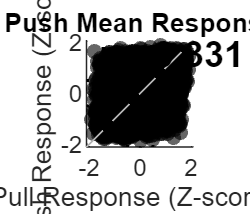

%% 2. レバー応答 (Push vs Pull) の比較と分類プロット

% --- 設定 ---
start_col = 20; % 解析に使用するウィンドウの開始フレーム
end_col = 30;   % 解析に使用するウィンドウの終了フレーム
threshold_low = -0.5; % Z-scoreの下限閾値
threshold_high = 0.5; % Z-scoreの上限閾値

% --- 平均活動の計算 (結合データを使用) ---
% force_act_conc (Pull) と force_act2_conc (Push) を使用
mean_force_act = mean(force_act_conc(:, start_col:end_col), 2);  % Pull response
mean_force_act2 = mean(force_act2_conc(:, start_col:end_col), 2); % Push response

% --- 散布図のプロット ---
figure('Name', 'Lever Push vs Pull Response', 'Color', 'w', 'Position', [100, 100, 700, 600]);
scatter(mean_force_act, mean_force_act2, 25, 'filled', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'none', 'MarkerFaceAlpha', 0.6);

% タイトルと軸ラベル
title('Lever Pull vs Push Mean Response (All Animals)');
xlabel('Pull Response (Z-scored)');
ylabel('Push Response (Z-scored)');

% 軸の調整
all_data = [mean_force_act; mean_force_act2];
min_val = min(all_data) - 0.2;
max_val = max(all_data) + 0.2;
% 見やすくするために範囲を固定したい場合は以下を有効化
% min_val = -2.0; max_val = 2.0; 

xlim([min_val max_val]);
ylim([min_val max_val]);
axis square; % 正方形プロット
hold on;

% 閾値ラインの描画 (グリッド代わり)
plot([threshold_high threshold_high], ylim, 'k:', 'LineWidth', 1); % X = 0.5
plot([threshold_low threshold_low], ylim, 'k:', 'LineWidth', 1);   % X = -0.5
plot(xlim, [threshold_high threshold_high], 'k:', 'LineWidth', 1); % Y = 0.5
plot(xlim, [threshold_low threshold_low], 'k:', 'LineWidth', 1);   % Y = -0.5
plot([min_val max_val], [min_val max_val], 'k--', 'Color', [0.7 0.7 0.7]); % X=Y線

% 相関係数の計算と表示
valid_idx = ~isnan(mean_force_act) & ~isnan(mean_force_act2);
[r, p_val] = corr(mean_force_act(valid_idx), mean_force_act2(valid_idx));
text(min_val + 0.5, max_val - 0.5, sprintf('r = %.3f', r), 'FontSize', 12, 'FontWeight', 'bold');

hold off;
% 保存
saveas(gcf, [output_dir 'AllAnimals_PushPull_Scatter.png']);

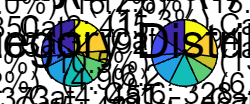



%% 3. 細胞のカテゴリー分類 (1-9)
num_cells = length(mean_force_act);
cell_cats = NaN(num_cells, 1);

for i = 1:num_cells
    val_pull = mean_force_act(i);
    val_push = mean_force_act2(i);
    
    if isnan(val_pull) || isnan(val_push), continue; end
    
    % X軸 (Pull) の判定
    if val_pull < threshold_low
        cat_x = 1; % Suppression
    elseif val_pull > threshold_high
        cat_x = 3; % Activation
    else
        cat_x = 2; % No response
    end
    
    % Y軸 (Push) の判定
    if val_push < threshold_low
        cat_y = 1; % Suppression
    elseif val_push > threshold_high
        cat_y = 3; % Activation
    else
        cat_y = 2; % No response
    end
    
    % 1~9 のカテゴリIDに変換
    % (Row-major order: 1=Low/Low, 2=Mid/Low, 3=High/Low, ...)
    cell_cats(i) = (cat_y - 1) * 3 + cat_x;
end

%% 4. 層ごとの割合プロット (円グラフ)

% 層のID定義 (通常: 1=Layer2/3, 0=Layer5 と仮定)
% pointAreas_conc が結合されている前提
unique_layers = unique(pointAreas_conc(~isnan(pointAreas_conc)));
layer_names = containers.Map({0, 1}, {'Layer 5', 'Layer 2/3'});
colors_cat = parula(9); % カテゴリ用のカラーマップ

figure('Name', 'Category Distribution by Layer', 'Color', 'w', 'Position', [100, 100, 1200, 500]);

for i = 1:length(unique_layers)
    curr_layer = unique_layers(i);
    
    % この層に属する細胞のインデックス
    idx_layer = (pointAreas_conc == curr_layer);
    
    % この層のカテゴリ分布を取得
    cats_in_layer = cell_cats(idx_layer);
    cats_in_layer = cats_in_layer(~isnan(cats_in_layer)); % NaN除去
    
    total_cells = length(cats_in_layer);
    counts = zeros(1, 9);
    for c = 1:9
        counts(c) = sum(cats_in_layer == c);
    end
    pcts = counts / total_cells * 100;
    
    % --- 円グラフの作成 ---
    subplot(1, length(unique_layers), i);
    
    % ラベル作成 (カウントと%を表示)
    labels = arrayfun(@(c) sprintf('Cat%d: %d\n(%.1f%%)', c, counts(c), pcts(c)), 1:9, 'UniformOutput', false);
    
    % 0%のカテゴリはラベルを非表示にする
    labels(pcts == 0) = {''};
    
    p = pie(counts, labels);
    
    % タイトル
    if isKey(layer_names, curr_layer)
        l_name = layer_names(curr_layer);
    else
        l_name = sprintf('Layer ID %d', curr_layer);
    end
    title(sprintf('%s (n=%d)', l_name, total_cells), 'FontSize', 14, 'FontWeight', 'bold');
end

% 凡例の説明図を追加 (別ウィンドウまたは空きスペース)
sgtitle('Lever Response Category Distribution (Pull vs Push)', 'FontSize', 16);

% 保存
saveas(gcf, [output_dir 'AllAnimals_Layer_Category_Pie.png']);


%% 5. カテゴリの意味を出力
fprintf('\n--- Category Definitions ---\n');


--- Category Definitions ---


fprintf('Cat 1: Pull(-), Push(-)\n');

Cat 1: Pull(-), Push(-)


fprintf('Cat 2: Pull(0), Push(-)\n');

Cat 2: Pull(0), Push(-)


fprintf('Cat 3: Pull(+), Push(-)\n');

Cat 3: Pull(+), Push(-)


fprintf('Cat 4: Pull(-), Push(0)\n');

Cat 4: Pull(-), Push(0)


fprintf('Cat 5: Pull(0), Push(0) [Non-responsive]\n');

Cat 5: Pull(0), Push(0) [Non-responsive]


fprintf('Cat 6: Pull(+), Push(0) [Pull Only]\n');

Cat 6: Pull(+), Push(0) [Pull Only]


fprintf('Cat 7: Pull(-), Push(+)\n');

Cat 7: Pull(-), Push(+)


fprintf('Cat 8: Pull(0), Push(+) [Push Only]\n');

Cat 8: Pull(0), Push(+) [Push Only]


fprintf('Cat 9: Pull(+), Push(+) [Both Active]\n');

Cat 9: Pull(+), Push(+) [Both Active]


% caluculate ETA of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    pull_sig_cell_idxs   = cell(0,length(AlinmentTimingCells)+1);
    pull_actss = cell(0,length(AlinmentTimingCells)+1);
    % pull_Is = cell(0,length(AlinmentTimingCells)+1);
    pull_actss_train = cell(0,length(AlinmentTimingCells)+1);
    pull_act_store = cell(length(AlinmentTimingCells),length(Animal));
    for i = 1:length(AlinmentTimingCells)
        for k_animal = 1:length(Animal)
            pull_act      = zeros(size(acc_neural_activity_data_all_sessions{k_animal},2),fps*(before_event+after_event)+1);
            exception_count = 0;
            pull_acts = {};
            pull_idx = AlinmentTimingCells{i};
            for j = 1:size(pull_idx,2)
                if pull_idx(k_animal,j)-fps*before_event<=0 | pull_idx(k_animal,j)+fps*after_event>size(acc_neural_activity_data_all_sessions{k_animal},1)
                    exception_count = exception_count + 1;
                else
                    pull_act = pull_act+transpose(acc_neural_activity_data_all_sessions{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:)); 
                    pull_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:));
                end
            end
            pull_act = pull_act/(size(pull_idx,2)-exception_count);
            pull_acts = reshape(cell2mat(pull_acts),[size(acc_neural_activity_data_all_sessions{k_animal}, 2) size(pull_act,2) size(pull_idx,2)-exception_count]);
            if norm == 1
                pull_act = normalize_rows(pull_act);
            elseif norm ==2
               pull_act = zscore_rows(pull_act); 
            elseif norm ==6
               pull_act = zscore_rows_by_before_pull(pull_act);               
            elseif norm == 4
               if i == 1 | i == 3 | i == 4
                   pull_act_store{i,k_animal} = pull_act;
                   pull_act = zscore_rows(pull_act); 
               elseif i == 2
                   pull_act = zscore_rows_by_diff_matrix(pull_act,pull_act_store{1,k_animal});
               elseif i == 5 | i == 6
                   pull_act = zscore_rows_by_diff_matrix(pull_act,pull_act_store{i-2,k_animal});
               end                         
            elseif norm ==3
                % sig_all, pull_activated-deactivated,
                % pred_activated-deactivated,
                % surprise_activated-deactivated
                sig_cell_idx = zeros(7,size(acc_neural_activity_data_all_sessions{k_animal}, 2));               
                for i_cell = 1:size(acc_neural_activity_data_all_sessions{k_animal}, 2)
                    for l_sig = 1:7
                        if l_sig == 1
                            [~,maxmin_idx] = max(mean(pull_acts(i_cell,:,:),3)); 
                        elseif l_sig == 2
                            [~,maxmin_idx] = max(mean(pull_acts(i_cell,21:40,:),3));
                            maxmin_idx = maxmin_idx+20;
                        elseif l_sig == 3
                            [~,maxmin_idx] = min(mean(pull_acts(i_cell,21:40,:),3));
                            maxmin_idx = maxmin_idx+20;
                        elseif l_sig == 4
                            [~,maxmin_idx] = max(mean(pull_acts(i_cell,1:20,:),3));
                        elseif l_sig == 5
                            [~,maxmin_idx] = min(mean(pull_acts(i_cell,1:20,:),3)); 
                        elseif l_sig == 6
                            [~,maxmin_idx] = max(mean(pull_acts(i_cell,21:25,:),3));
                            maxmin_idx = maxmin_idx+20;
                        elseif l_sig == 7
                            [~,maxmin_idx] = min(mean(pull_acts(i_cell,21:25,:),3));    
                            maxmin_idx = maxmin_idx+20;
                        end
                        maxmin_pull_acts = pull_acts(i_cell,maxmin_idx,:);
                        [h,p] = ttest2(squeeze(pull_acts(i_cell,:)),squeeze(maxmin_pull_acts),'Vartype','unequal');
                        if h == 1
                            sig_cell_idx(l_sig,i_cell) = 1;
                        else
                            sig_cell_idx(l_sig,i_cell) = 0;
                        end
                    end
                    % pull_sig_cell_idxs{i} = sig_cell_idx;
                end
                pull_act = zscore_rows(pull_act(find(sig_cell_idx(1,:)==1),:));
            elseif norm == 5
                % separete train and test of trial_start_acts
                L = size(pull_acts, 3);
                % 最後の次元に基づいてランダムにインデックスをシャッフル
                indices = randperm(L);        
                % インデックスを2つのグループに分ける
                half_L1 = ceil(L / 2); % (L+1)/2のサイズ
                half_L2 = floor(L / 2); % (L-1)/2のサイズ        
                indices1 = indices(1:half_L1);
                indices2 = indices(half_L1+1:end);         
                % 2つのテンソルに分割
                pull_acts_train = pull_acts(:, :, indices1);
                pull_acts_test  = pull_acts(:, :, indices2);
                % sort with train data
                pull_act_train_raw = mean(pull_acts_train, 3);
                pull_act_test_raw  = mean(pull_acts_test, 3);
                pull_act_train = zscore_rows(pull_act_train_raw);
                pull_act_test  = zscore_rows(pull_act_test_raw);
                pull_act       = zscore_rows(pull_act_test_raw);                
            end

            if k_animal == 1
                pull_act_multi_animals = pull_act;
                if norm == 5
                    pull_act_train_multi_animals = pull_act_train;
                elseif norm == 3
                    sig_cell_idx_multi_animals = sig_cell_idx;
                end
            else
                pull_act_multi_animals = vertcat(pull_act_multi_animals,pull_act);
                if norm == 5
                    pull_act_train_multi_animals = vertcat(pull_act_train_multi_animals,pull_act_train);
                elseif norm == 3
                    sig_cell_idx_multi_animals = horzcat(sig_cell_idx_multi_animals,sig_cell_idx);
                end
            end            
            % [M,pull_I{k_animal}] = max(pull_act,[],2);
            % pull_act = cat(2,pull_I{k_animal},pull_act);
            % pull_act = sortrows(pull_act);
            % pull_act_max_act_times{k_animal} = pull_act(:,1)/10 -2;
            % pull_act(:,1) = [];     
        end
           
        pull_actss{i} = pull_act_multi_animals;
        if norm == 5
            pull_actss_train{i} = pull_act_train_multi_animals;
        elseif norm == 3
            pull_sig_cell_idxs{i} = sig_cell_idx_multi_animals;
        end
        % pull_Is{i} = pull_I;
    end
    % add heavy light combined pull timing
    for k_animal = 1:length(Animal)
        pull_act      = zeros(size(acc_neural_activity_data_all_sessions{k_animal},2),fps*(before_event+after_event)+1);
        exception_count = 0;
        pull_acts = {};
        pull_idx = [AlinmentTimingCells{1},AlinmentTimingCells{2}];
        for j = 1:size(pull_idx,2)
            if pull_idx(k_animal,j)-fps*before_event<=0 | pull_idx(k_animal,j)+fps*after_event>size(acc_neural_activity_data_all_sessions{k_animal},1)
                exception_count = exception_count + 1;
            else
                pull_act = pull_act+transpose(acc_neural_activity_data_all_sessions{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:)); 
                pull_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:));
            end
        end
        pull_act = pull_act/(size(pull_idx,2)-exception_count);
        pull_acts = reshape(cell2mat(pull_acts),[size(acc_neural_activity_data_all_sessions{k_animal}, 2) size(pull_act,2) size(pull_idx,2)-exception_count]);
        if norm == 1
            pull_act = normalize_rows(pull_act);
        elseif norm ==2 || norm == 4
           pull_act = zscore_rows(pull_act); 
        elseif norm ==6
           pull_act = zscore_rows_by_before_pull(pull_act);           
        elseif norm ==3
            % sig_all, pull_activated-deactivated,
            % pred_activated-deactivated,
            % surprise_activated-deactivated
            sig_cell_idx = zeros(7,size(acc_neural_activity_data_all_sessions{k_animal}, 2));               
            for i_cell = 1:size(acc_neural_activity_data_all_sessions{k_animal}, 2)
                for l_sig = 1:7
                    if l_sig == 1
                        [~,maxmin_idx] = max(mean(pull_acts(i_cell,:,:),3)); 
                    elseif l_sig == 2
                        [~,maxmin_idx] = max(mean(pull_acts(i_cell,21:40,:),3));
                        maxmin_idx = maxmin_idx+20;
                    elseif l_sig == 3
                        [~,maxmin_idx] = min(mean(pull_acts(i_cell,21:40,:),3));
                        maxmin_idx = maxmin_idx+20;
                    elseif l_sig == 4
                        [~,maxmin_idx] = max(mean(pull_acts(i_cell,1:20,:),3));
                    elseif l_sig == 5
                        [~,maxmin_idx] = min(mean(pull_acts(i_cell,1:20,:),3)); 
                    elseif l_sig == 6
                        [~,maxmin_idx] = max(mean(pull_acts(i_cell,21:25,:),3));
                        maxmin_idx = maxmin_idx+20;
                    elseif l_sig == 7
                        [~,maxmin_idx] = min(mean(pull_acts(i_cell,21:25,:),3));    
                        maxmin_idx = maxmin_idx+20;
                    end
                    maxmin_pull_acts = pull_acts(i_cell,maxmin_idx,:);
                    [h,p] = ttest2(squeeze(pull_acts(i_cell,:)),squeeze(maxmin_pull_acts),'Vartype','unequal');
                    if h == 1
                        sig_cell_idx(l_sig,i_cell) = 1;
                    else
                        sig_cell_idx(l_sig,i_cell) = 0;
                    end
                end
                % pull_sig_cell_idxs{i+1} = sig_cell_idx;
            end
            pull_act = zscore_rows(pull_act(find(sig_cell_idx(1,:)==1),:));            
        elseif norm == 5
            % separete train and test of trial_start_acts
            L = size(pull_acts, 3);
            % 最後の次元に基づいてランダムにインデックスをシャッフル
            indices = randperm(L);        
            % インデックスを2つのグループに分ける
            half_L1 = ceil(L / 2); % (L+1)/2のサイズ
            half_L2 = floor(L / 2); % (L-1)/2のサイズ        
            indices1 = indices(1:half_L1);
            indices2 = indices(half_L1+1:end);         
            % 2つのテンソルに分割
            pull_acts_train = pull_acts(:, :, indices1);
            pull_acts_test  = pull_acts(:, :, indices2);
            % sort with train data
            pull_act_train_raw = mean(pull_acts_train, 3);
            pull_act_test_raw  = mean(pull_acts_test, 3);
            pull_act_train = zscore_rows(pull_act_train_raw);
            pull_act_test  = zscore_rows(pull_act_test_raw);
            pull_act       = zscore_rows(pull_act_test_raw);             
        end

        if k_animal == 1
            pull_act_multi_animals = pull_act;
            if norm == 5
                pull_act_train_multi_animals = pull_act_train;
            elseif norm == 3
                sig_cell_idx_multi_animals = sig_cell_idx;                
            end            
        else
            pull_act_multi_animals = vertcat(pull_act_multi_animals,pull_act);
            if norm == 5
                pull_act_train_multi_animals = vertcat(pull_act_train_multi_animals,pull_act_train);
            elseif norm == 3
                sig_cell_idx_multi_animals = horzcat(sig_cell_idx_multi_animals,sig_cell_idx);                
            end            
        end            
        % [M,pull_I{k_animal}] = max(pull_act,[],2);
        % pull_act = cat(2,pull_I{k_animal},pull_act);
        % pull_act = sortrows(pull_act);
        % pull_act_max_act_times{k_animal} = pull_act(:,1)/10 -2;
        % pull_act(:,1) = [];
    end
    pull_actss{i+1} = pull_act_multi_animals;
    % pull_Is{i+1} = pull_I;
    if norm == 5
        pull_actss_train{i+1} = pull_act_train_multi_animals;
    elseif norm == 3
        pull_sig_cell_idxs{i+1} = sig_cell_idx_multi_animals;        
    end    
end

% write eta code by categrizing neurons by layers

if strcmp(categorize, 'layer') == 1
    % align concatenated eta neural activities
    [M,trial_start_i] = max(trial_start_act_conc,[],2);
    [M,trial_end_i] = max(trial_end_act_conc,[],2);  
    [M,position_i] = max(position_act_conc,[],2);
    [M,force_i] = max(force_act_conc,[],2);
    [M,force2_i] = max(force_act2_conc,[],2);
    [M,reward_i] = max(reward_act_conc,[],2);

    if norm==3
        trial_start_act_conc = cat(2, trial_start_i,pointAreas_conc(find(sig_cell_idxs_conc{1} == 1)) ,trial_start_act_conc);
        trial_end_act_conc = cat(2, trial_end_i,pointAreas_conc(find(sig_cell_idxs_conc{2} == 1)) ,trial_end_act_conc);
        position_act_conc = cat(2, position_i,pointAreas_conc(find(sig_cell_idxs_conc{3} == 1)) ,position_act_conc);
        force_act_conc = cat(2, force_i,pointAreas_conc(find(sig_cell_idxs_conc{4} == 1)) ,force_act_conc);
        force_act2_conc = cat(2, force2_i,pointAreas_conc(find(sig_cell_idxs_conc{6} == 1)) ,force_act2_conc);
        reward_act_conc = cat(2, reward_i,pointAreas_conc(find(sig_cell_idxs_conc{5} == 1)) ,reward_act_conc);
    else
        trial_start_act_conc = cat(2, trial_start_i,pointAreas_conc ,trial_start_act_conc);
        trial_end_act_conc = cat(2, trial_end_i,pointAreas_conc ,trial_end_act_conc);
        position_act_conc = cat(2, position_i,pointAreas_conc ,position_act_conc);
        force_act_conc = cat(2, force_i,pointAreas_conc ,force_act_conc);
        force_act2_conc = cat(2, force2_i,pointAreas_conc ,force_act2_conc);
        reward_act_conc = cat(2, reward_i,pointAreas_conc ,reward_act_conc);
    end

    trial_start_act_conc =   sortrows(trial_start_act_conc);
    trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startAreas = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];

    trial_end_act_conc =   sortrows(trial_end_act_conc);
    trial_end_act_max_act_time_conc = trial_end_act_conc(:,1)/10 -2;
    endAreas = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];  

    position_act_conc =   sortrows(position_act_conc);
    position_act_max_act_time_conc = position_act_conc(:,1)/10 -2;
    positionAreas = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];    

    force_act_conc =   sortrows(force_act_conc);
    force_act_max_act_time_conc = force_act_conc(:,1)/10 -2;
    forceAreas = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];    

    force_act2_conc =   sortrows(force_act2_conc);
    force_act2_max_act_time_conc = force_act2_conc(:,1)/10 -2;
    forceAreas2 = force_act2_conc(:,2);
    force_act2_conc(:,1:2) = [];        

    reward_act_conc =   sortrows(reward_act_conc);
    reward_act_max_act_time_conc = reward_act_conc(:,1)/10 -2;
    rewardAreas = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];    

    % specify layer specific activity
    trial_start_act_layer23_conc = trial_start_act_conc(find(startAreas == 1),:);
    trial_start_act_layer5_conc  = trial_start_act_conc(find(startAreas == 0),:);
    trial_end_act_layer23_conc = trial_end_act_conc(find(endAreas == 1),:);
    trial_end_act_layer5_conc  = trial_end_act_conc(find(endAreas == 0),:);
    position_act_layer23_conc = position_act_conc(find(positionAreas == 1),:);
    position_act_layer5_conc  = position_act_conc(find(positionAreas == 0),:);
    force_act_layer23_conc = force_act_conc(find(forceAreas == 1),:);
    force_act_layer5_conc  = force_act_conc(find(forceAreas == 0),:);
    force_act2_layer23_conc = force_act2_conc(find(forceAreas2 == 1),:);
    force_act2_layer5_conc  = force_act2_conc(find(forceAreas2 == 0),:);    
    reward_act_layer23_conc = reward_act_conc(find(rewardAreas == 1),:);
    reward_act_layer5_conc  = reward_act_conc(find(rewardAreas == 0),:);
end

if strcmp(categorize, 'layer') == 1 & norm == 5
    % align concatenated eta neural activities
    % pointAreas_train_conc = pointAreas_conc(find(train_test_indices==1));
    % pointAreas_test_conc  = pointAreas_conc(find(train_test_indices==2));

    [M,trial_start_i] = max(trial_start_act_train_conc,[],2);
    trial_start_act_conc = cat(2, trial_start_i,pointAreas_conc ,trial_start_act_train_conc, trial_start_act_test_conc);
    trial_start_act_conc =   sortrows(trial_start_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startAreas_train = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];
    trial_len = size(trial_start_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    trial_start_act_test_conc  = trial_start_act_conc(:,trial_len+1:size(trial_start_act_conc,2));  
    trial_start_act_conc = trial_start_act_test_conc; 

    [M,trial_end_i] = max(trial_end_act_train_conc,[],2);
    trial_end_act_conc = cat(2, trial_end_i,pointAreas_conc ,trial_end_act_train_conc, trial_end_act_test_conc);
    trial_end_act_conc =   sortrows(trial_end_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    endAreas_train = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];
    trial_len = size(trial_end_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    trial_end_act_test_conc  = trial_end_act_conc(:,trial_len+1:size(trial_end_act_conc,2));  
    trial_end_act_conc = trial_end_act_test_conc;    

    [M,position_i] = max(position_act_train_conc,[],2);
    position_act_conc = cat(2, position_i,pointAreas_conc ,position_act_train_conc, position_act_test_conc);
    position_act_conc =   sortrows(position_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    positionAreas_train = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];
    trial_len = size(position_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    position_act_test_conc  = position_act_conc(:,trial_len+1:size(position_act_conc,2));  
    position_act_conc = position_act_test_conc; 

    [M,force_i] = max(force_act_train_conc,[],2);
    force_act_conc = cat(2, force_i,pointAreas_conc ,force_act_train_conc, force_act_test_conc);
    force_act_conc =   sortrows(force_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    forceAreas_train = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];
    trial_len = size(force_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    force_act_test_conc  = force_act_conc(:,trial_len+1:size(force_act_conc,2));  
    force_act_conc = force_act_test_conc;   

    [M,force2_i] = max(force_act2_train_conc,[],2);
    force_act2_conc = cat(2, force2_i,pointAreas_conc ,force_act2_train_conc, force_act2_test_conc);
    force_act2_conc =   sortrows(force_act2_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    forceAreas2_train = force_act2_conc(:,2);
    force_act2_conc(:,1:2) = [];
    trial_len = size(force_act2_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    force_act2_test_conc  = force_act2_conc(:,trial_len+1:size(force_act2_conc,2));  
    force_act2_conc = force_act2_test_conc;     

    [M,reward_i] = max(reward_act_train_conc,[],2);
    reward_act_conc = cat(2, reward_i,pointAreas_conc ,reward_act_train_conc, reward_act_test_conc);
    reward_act_conc =   sortrows(reward_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    rewardAreas_train = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];
    trial_len = size(reward_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    reward_act_test_conc  = reward_act_conc(:,trial_len+1:size(reward_act_conc,2));  
    reward_act_conc = reward_act_test_conc;      

    % specify layer specific activity
    trial_start_act_layer23_conc = trial_start_act_test_conc(find(startAreas_train == 1),:);
    trial_start_act_layer5_conc  = trial_start_act_test_conc(find(startAreas_train == 0),:);    
    trial_end_act_layer23_conc   = trial_end_act_test_conc(find(endAreas_train == 1),:);
    trial_end_act_layer5_conc    = trial_end_act_test_conc(find(endAreas_train == 0),:);  
    position_act_layer23_conc    = position_act_test_conc(find(positionAreas_train == 1),:);
    position_act_layer5_conc     = position_act_test_conc(find(positionAreas_train == 0),:);    
    force_act_layer23_conc       = force_act_test_conc(find(forceAreas_train == 1),:);
    force_act_layer5_conc        = force_act_test_conc(find(forceAreas_train == 0),:);  
    force_act2_layer23_conc       = force_act2_test_conc(find(forceAreas2_train == 1),:);
    force_act2_layer5_conc        = force_act2_test_conc(find(forceAreas2_train == 0),:); 
    reward_act_layer23_conc      = reward_act_test_conc(find(rewardAreas_train == 1),:);
    reward_act_layer5_conc       = reward_act_test_conc(find(rewardAreas_train == 0),:);      

    % zscore and return only test data
    % trial_start_act_raw = trial_start_act_test_raw;
    % trial_start_act = zscore_rows(trial_start_act_test);
end

% write eta code by categrizing neurons by layers for Kota (pull) timing alignment
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    num_conditions = length(AlinmentTimingCells)+1;
    pull_act_layer23_cells   = cell(0,num_conditions);
    pull_act_layer5_cells    = cell(0,num_conditions);
    pullAreass   = cell(0,num_conditions);
    pull_actss_ordered = cell(0,num_conditions);
    if norm == 5
        for i = 1:num_conditions
            pull_act_test_multi_animals = pull_actss{i};
            pull_act_train_multi_animals = pull_actss_train{i};            
        % align concatenated eta neural activities
            [M,pull_i] = max(pull_act_train_multi_animals,[],2);
            pull_act_multi_animals = cat(2, pull_i,pointAreas_conc ,pull_act_train_multi_animals,pull_act_test_multi_animals);
            pull_act_multi_animals = sortrows(pull_act_multi_animals);
            % pull_act_max_act_time_multi_animals = pull_act_multi_animals(:,1)/10 -2;
            pullAreas = pull_act_multi_animals(:,2);
            pull_act_multi_animals(:,1:2) = [];
            trial_len = size(pull_act_train_multi_animals,2);
            pull_act_multi_animals_test = pull_act_multi_animals(:,trial_len+1:size(pull_act_multi_animals,2));
            pull_actss_ordered{i} = pull_act_multi_animals_test;
    
            pull_act_layer23_cells{i} = pull_act_multi_animals_test(find(pullAreas == 1),:); 
            pull_act_layer5_cells{i}  = pull_act_multi_animals_test(find(pullAreas == 0),:);
            pullAreass{i} = pullAreas;
        end
    else
        for i = 1:num_conditions
            pull_act_multi_animals = pull_actss{i};
        % align concatenated eta neural activities
            [M,pull_i] = max(pull_act_multi_animals,[],2);

            if norm==3
                pull_act_multi_animals = cat(2, pull_i,pointAreas_conc(find(pull_sig_cell_idxs{i}(1,:) == 1)) ,pull_act_multi_animals);
            else
                pull_act_multi_animals = cat(2, pull_i,pointAreas_conc ,pull_act_multi_animals);
            end

            pull_act_multi_animals = sortrows(pull_act_multi_animals);
            % pull_act_max_act_time_multi_animals = pull_act_multi_animals(:,1)/10 -2;
            pullAreas = pull_act_multi_animals(:,2);
            pull_act_multi_animals(:,1:2) = [];
            pull_actss_ordered{i} = pull_act_multi_animals;
    
            pull_act_layer23_cells{i} = pull_act_multi_animals(find(pullAreas == 1),:); %% TODO: need to modify
            pull_act_layer5_cells{i}  = pull_act_multi_animals(find(pullAreas == 0),:);
            pullAreass{i} = pullAreas;
        end
    end
end

% write eta code with depth

if strcmp(categorize, 'depth') == 1
    % align concatenated eta neural activities
    [M,trial_start_i] = max(trial_start_act_conc,[],2);
    trial_start_act_conc = cat(2, trial_start_i,depth_conc ,trial_start_act_conc);
    trial_start_act_conc =   sortrows(trial_start_act_conc);
    trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startDepth = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];

    [M,trial_end_i] = max(trial_end_act_conc,[],2);
    trial_end_act_conc = cat(2, trial_end_i,depth_conc ,trial_end_act_conc);
    trial_end_act_conc =   sortrows(trial_end_act_conc);
    trial_end_act_max_act_time_conc = trial_end_act_conc(:,1)/10 -2;
    endDepth = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];  

    [M,position_i] = max(position_act_conc,[],2);
    position_act_conc = cat(2, position_i,depth_conc ,position_act_conc);
    position_act_conc =   sortrows(position_act_conc);
    position_act_max_act_time_conc = position_act_conc(:,1)/10 -2;
    posDepth = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];    

    [M,force_i] = max(force_act_conc,[],2);
    force_act_conc = cat(2, force_i,depth_conc ,force_act_conc);
    force_act_conc =   sortrows(force_act_conc);
    force_act_max_act_time_conc = force_act_conc(:,1)/10 -2;
    forceDepth = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];    

    [M,force2_i] = max(force_act2_conc,[],2);
    force_act2_conc = cat(2, force2_i,depth_conc ,force_act2_conc);
    force_act2_conc =   sortrows(force_act2_conc);
    force_act2_max_act_time_conc = force_act2_conc(:,1)/10 -2;
    forceDepth2 = force_act2_conc(:,2);
    force_act2_conc(:,1:2) = [];        

    [M,reward_i] = max(reward_act_conc,[],2);
    reward_act_conc = cat(2, reward_i,depth_conc ,reward_act_conc);
    reward_act_conc =   sortrows(reward_act_conc);
    reward_act_max_act_time_conc = reward_act_conc(:,1)/10 -2;
    rewardDepth = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];    
end

% write eta code by categrizing neurons by layers for Kota (pull) timing alignment
if strcmp(categorize, 'depth') == 1 & Kota_alignment == 1
    % pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    % pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
    pullDepths   = cell(0,length(AlinmentTimingCells));
    for i = 1:length(AlinmentTimingCells)
        pull_act_multi_animals = pull_actss{i};
    % align concatenated eta neural activities
        [M,pull_i] = max(pull_act_multi_animals,[],2);
        pull_act_multi_animals = cat(2, pull_i,depth_conc ,pull_act_multi_animals);
        pull_act_multi_animals = sortrows(pull_act_multi_animals);
        pull_act_max_act_time_multi_animals = pull_act_multi_animals(:,1)/10 -2;
        pullDepth = pull_act_multi_animals(:,2);
        pull_act_multi_animals(:,1:2) = [];
        % 
        % pull_act_layer23_cells{i} = pull_actss{i}(:,find(pullAreas == 1),:); %% TODO: need to modify
        % pull_act_layer5_cells{i}  = pull_actss{i}(:,find(pullAreas == 0),:);
        pullDepths{i} = pullDepth;
    end
end

% plot neural activity heatmap
if norm == 1
    climit = [0 1];
elseif norm == 2 | norm == 3 | norm == 4 | norm == 5 
    climit = [-2 2];
elseif norm == 6
    climit = [-4 4];
else
    climit = [0 50];
end
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_start_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.1305    0.9027    0.7597    0.9930    0.4266    0.2344    0.2522    0.4461    0.4455    0.2280    0.2153    0.0296    0.1099    0.0332   -0.2072   -0.7571   -0.5333   -0.9623   -1.2330   -1.3357   -1.5293   -1.7313   -2.0955   -2.3580   -2.0854   -1.9129   -2.0113   -1.8818   -1.2874   -1.2497   -0.4576   -0.5636   -0.7978    0.0067    0.1256    0.1284    0.3455    0.3171    0.1604    0.4794    0.5600    0.6251    0.9441    1.1265    0.7827    0.8952    0.9610    0.5631    0.8182    0.6564
    1.1600    1.0218    0.8722    0.7267    0.5479    0.4700    0.4055    0.7163    0.8065    0.7668    0.9168    0.7328    0.6523    0.6641    0.5524    0.8634    0.1385    0.2306   -0.0486    0.3670    0.0396    0.1989    0.0133    0.5757    0.5689    0.6758    0.3080   -0.3340   -0.8717   -1.3790   -1.8093   -2.2764   -1.8501   -1.9105   -2.1181   -2.0356   -2.1019   -1.8359   -1.4692   -1.1223   -0.9029   -0.7553   -0.8904   -0.4987   -0.3482    0.0351   -0.0463   -0.1234    0.4288 

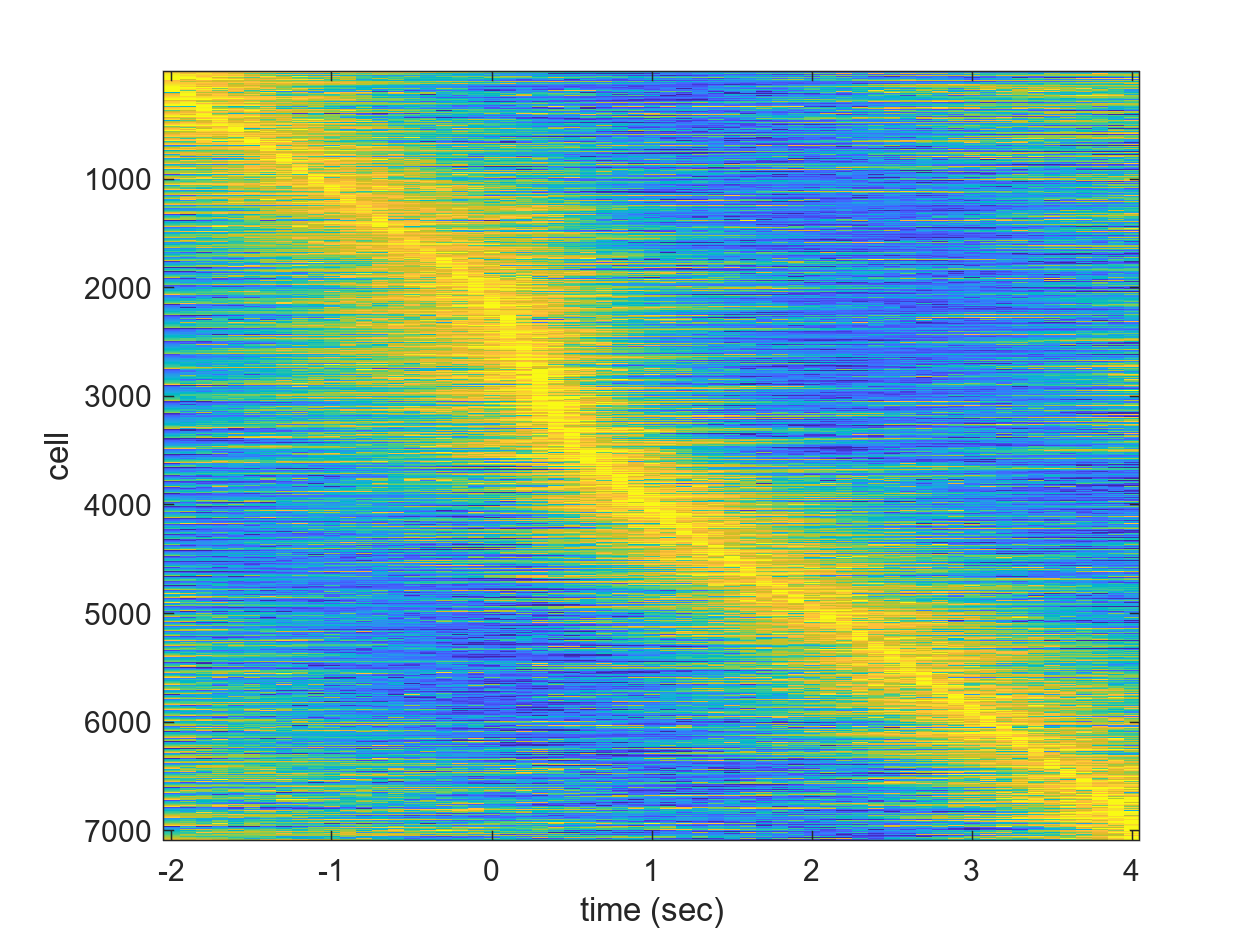

    imagesc(-before_event:0.1:after_event,1:size(trial_start_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_start_eta_activity_heatmap.png'];
filename = [output_dir 'trial_start_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_end_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.2208    0.9887    0.8141    0.8629    0.5998    0.4537    0.5631    0.5391    0.5202    0.3204    0.7261    0.5859    0.8211    0.8819    1.0153    0.9205    0.8334    0.8590    0.8829    0.7865    0.3413    0.2057    0.1062    0.3678    0.4528    0.4800    0.2890    0.0397   -0.2599   -0.4636   -0.9908   -1.3233   -1.7067   -1.7215   -2.0348   -2.0302   -2.3658   -2.0983   -1.7844   -1.7944   -1.6123   -1.4138   -1.3840   -0.8338   -0.7396   -0.5154   -0.1936    0.0226    0.3496    0.2905
    1.2776    0.8567    1.0623    1.1496    0.7204    0.3872    0.9637    0.1777    0.8560    0.5857    0.0385    0.7885    0.6496    0.7305    0.3492    0.9044    0.6694    0.2784    0.3694    0.4269    0.5953    0.2433   -0.6816   -0.2728   -1.6995   -1.9492   -2.5219   -2.2973   -1.6175   -2.1536   -1.3979   -0.8796   -0.4249   -0.3918   -0.4593   -0.2376    0.4962    0.3014   -0.0869   -0.4560   -0.6018   -0.7456   -0.9100   -1.4265   -1.3217   -1.7381   -0.5052   -0.4742   -0.1065 

    imagesc(-before_event:0.1:after_event,1:size(trial_end_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_end_eta_activity_heatmap.png'];
filename = [output_dir 'trial_end_eta_activity_heatmap.png'];
saveas(gcf,filename);
% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = position_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.3618    1.3330    1.2050    1.1161    0.8454    0.4797    0.6305    0.5226    0.5289    0.3904   -0.0030   -0.4053   -0.6801   -1.1743   -1.7071   -1.8782   -2.3836   -2.5093   -2.5657   -2.4380   -1.9866   -1.8195   -1.3348   -0.4489    0.0245    0.0469    0.1675    0.3521    0.5801    0.6173    0.7866    0.8768    0.6966    0.3474    0.2289    0.0242   -0.1072   -0.4683   -0.4358   -0.2112   -0.1802   -0.1896    0.0446    0.0108    0.0289    0.4602    0.5802    0.4818    0.5365    0.6867
    1.3671    1.2927    1.0909    1.2486    1.1220    1.1707    0.9305    0.8799    0.7310    0.8760    0.8445    1.0680    1.1994    1.1344    1.1944    1.0180    0.9809    1.0274    0.9963    1.0619    1.1252    1.0193    0.9838    1.0062    0.6919    0.4267    0.5618    0.3436    0.5108    0.1225    0.1955   -0.0386   -0.1360   -0.2168   -0.4560   -0.5925   -0.5895   -0.8284   -0.8272   -0.7892   -0.9871   -0.9427   -1.1107   -1.1979   -1.3148   -1.3402   -1.4634   -1.6491   -1.5877 

    imagesc(-before_event:0.1:after_event,1:size(position_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_position_eta_activity_heatmap.png'];
filename = [output_dir 'position_eta_activity_heatmap.png'];
saveas(gcf,filename);
% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = force_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.2530    1.1876    0.8499    1.0129    1.2521    1.1367    1.0934    0.9950    0.8270    0.9133    0.6948    0.8666    0.9698    0.6640    0.4970    0.1105    0.8941    0.4927    0.5751    0.9029    0.7221    0.9945    0.7139    0.5182    0.3066    0.1986   -0.0611   -0.5049   -0.5610   -0.9488   -0.8592   -1.3923   -1.6144   -1.5431   -1.6160   -1.8125   -1.7236   -1.7244   -1.8847   -1.7236   -1.5735   -1.6006   -1.5100   -1.0314   -0.8871   -0.6199   -0.4926   -0.3152   -0.0776   -0.0196
    1.3565    0.7044    1.2445    0.8669    1.0775    0.9757    0.4758    0.5851    0.2016    0.7805    0.7016    0.2786    0.2778    0.6509    0.1840    0.4105    0.4733    0.7015    0.2826    0.0066   -0.0453   -1.4702   -1.7525   -1.2071   -1.6989   -1.8067   -2.2078   -1.4493   -2.1673   -2.2421   -2.1355   -1.4722   -0.9600   -1.1754   -1.0700   -0.3691   -0.5370   -0.0437    0.1927    0.1760   -0.1768   -0.0054    0.4170    0.1356    0.0427    0.0862    0.2380    0.4256    0.1061 

    imagesc(-before_event:0.1:after_event,1:size(force_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_force_eta_activity_heatmap.png'];
filename = [output_dir 'force_eta_activity_heatmap.png'];
saveas(gcf,filename);
% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = force_act2_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.2796    1.2573    1.1055    1.1997    0.9222    0.9029    0.8220    0.7045    0.5746    0.5640    0.5069    0.4456    0.3499    0.3417    0.2412    0.2787    0.1137    0.0705    0.2638    0.2449    0.4742    0.6195    0.9074    0.7431    0.4833    0.3461    0.4001    0.2899    0.0657    0.0261   -0.3813   -0.6754   -1.1329   -1.5235   -1.8235   -2.0762   -2.1532   -2.1977   -2.2814   -1.9888   -1.9008   -1.6663   -1.5238   -1.2291   -0.8583   -0.6154   -0.2054   -0.0045    0.1464    0.2775
    1.3868    1.3831    1.3319    1.2360    1.3278    1.2493    1.0863    1.0152    1.0366    1.0269    1.0725    1.0880    1.1451    1.2355    1.2122    1.3638    1.2977    1.3062    1.2884    1.2191    1.0352    0.8635    0.3569    0.1741    0.1950    0.2900    0.4256    0.2878    0.2226   -0.0180   -0.1046   -0.2139   -0.5288   -0.7258   -0.6758   -0.9538   -1.0781   -0.9830   -1.0025   -0.9294   -1.2522   -1.2958   -1.1926   -1.2571   -1.1675   -1.2596   -1.1206   -0.9936   -0.9272 

    imagesc(-before_event:0.1:after_event,1:size(force_act2_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_force_eta_activity_heatmap.png'];
filename = [output_dir 'minus_force_eta_activity_heatmap.png'];
saveas(gcf,filename);
% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = reward_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.1607    0.9954    0.7826    0.7616    0.9213    0.8570    0.8652    1.0836    0.9779    1.0316    0.7954    0.7691    0.8223    0.7008    0.5999    0.5438    0.4818    0.4225    0.2734   -0.4049   -0.5523   -0.8318   -0.8953   -1.2244   -1.5122   -1.5366   -1.6934   -1.8895   -1.9384   -1.8981   -1.7585   -1.8439   -1.7137   -1.6633   -1.3859   -1.2217   -1.0866   -0.8272   -0.3089   -0.3845   -0.1187    0.1736    0.3849    0.4605    0.8145    0.7444    0.8578    0.8575    0.8377    0.8428
    1.1631    1.1328    1.1226    0.9072    1.1447    0.9815    0.9210    0.9724    1.1619    1.0096    0.9849    0.9453    0.9914    0.8983    0.9292    0.8181    0.9510    0.8236    0.9061    0.5807    0.5432    0.3007    0.3700    0.0829   -0.0202   -0.2097   -0.5446   -0.6953   -1.0622   -1.1319   -1.4445   -1.4053   -1.6744   -1.3618   -1.4864   -1.7226   -1.6917   -1.4653   -1.5153   -1.3208   -1.3326   -1.3151   -1.1772   -1.2264   -0.8437   -0.7942   -0.7483   -0.4240   -0.3876 

    imagesc(-before_event:0.1:after_event,1:size(reward_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_reward_eta_activity_heatmap.png'];
filename = [output_dir 'reward_eta_activity_heatmap.png'];
saveas(gcf,filename);
close all;

% % climit = [0 50];
% figure
% set(gcf,'color','w');
% 
% clims = climit;  % カラーマップのスケーリング
% image = force_act_conc;
% 
% % グレースケールのカラーマップ
% colormap(gray);
% 
% % ヒートマップ描画
% imagesc(-before_event:0.1:after_event, 1:size(force_act_conc,1), image, clims);
% 
% % 軸ラベル
% ylabel('cell');
% xlabel('time (sec)');
% 
% % 0秒位置に縦線
% hold on;
% xline(0, 'k--', 'LineWidth', 2.0);  % 黒の破線
% 
% % アスペクト比を正方形に近づける
% % axis tight;
% % axis equal;
% pbaspect([1 1 1]);  % 幅:高さ:奥行き = 1:1:1 に調整
% 
% % カラーバー（必要であれば）
% % colorbar;
% 
% % 保存
% filename = [output_dir 'force_eta_activity_heatmap_DC.png'];
% saveas(gcf, filename);
% close(gcf);

addpath([working_directory 'Utility' filesep 'Subaxis']);

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_actss_ordered{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        % NaNを含む行を削除
        image = image(~any(isnan(image), 2), :);
        imagesc(-before_event:0.1:after_event,1:size(pull_actss_ordered{i},1),image,clims);
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_eta_activity_heatmap.png'];
    filename = [output_dir 'pull_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data = pull_actss_ordered{i};
        data = data(~any(isnan(data), 2), :);

        z = zscore(data, 0, 1);  % 列方向に Zスコアを計算
        data = data(max(abs(z), [], 2) < 10, :);  % Zスコアが100以上の行を除去

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);
        x = -before_event:0.1:after_event;
      
        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % xlim = [-2,4]
        % x=0に赤い縦線をプロット       
        % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});        
         axis tight;
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end
    end
        
        % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_eta_activity.png'];
        filename = [output_dir 'pull_eta_activity.png'];
        saveas(gcf,filename);
    close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
L_width = 3;
if Kota_alignment == 1
    title_list = {'Heavy - Light', 'Exp heavy - Unexp heavy', 'Exp light - Unexp light', 'Exp heavy - Unexp heavy - Exp light - Unexp light'};

    figure('Position', [100, 100, 1600, 600]);
    for i = 1:4
        subaxis(1,4,i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.08);
        % NaNを含む行を削除
        if i == 1
            data1 = pull_actss_ordered{1}; data2 = pull_actss_ordered{2};
        elseif i == 4
            data1 = pull_actss_ordered{3}; data2 = pull_actss_ordered{5};   
            data3 = pull_actss_ordered{4}; data4 = pull_actss_ordered{6};
        else
            data1 = pull_actss_ordered{i+1}; data2 = pull_actss_ordered{i+3};
        end
        data1 = data1(~any(isnan(data1), 2), :); data2 = data2(~any(isnan(data2), 2), :);  
        z1 = zscore(data1, 0, 1); z2 = zscore(data2, 0, 1); % 列方向に Zスコアを計算
        data1 = data1(max(abs(z1), [], 2) < 10, :); data2 = data2(max(abs(z2), [], 2) < 10, :); % Zスコアが100以上の行を除去

        mean_values1 = mean(data1, 1); mean_values2 = mean(data2, 1);
        std_values1 = std(data1, 0, 1); std_values2 = std(data2, 1); 
        if i == 4
            data3 = data3(~any(isnan(data3), 2), :); data4 = data4(~any(isnan(data4), 2), :);   
            z3 = zscore(data3, 0, 1); z4 = zscore(data4, 0, 1); % 列方向に Zスコアを計算
            data3 = data3(max(abs(z3), [], 2) < 10, :); data4 = data4(max(abs(z4), [], 2) < 10, :); % Zスコアが100以上の行を除去
            
            mean_values3 = mean(data3, 1); mean_values4 = mean(data4, 1);
            std_values3 = std(data3, 0, 1); std_values4 = std(data4, 1);             
        end
        x = -before_event:0.1:after_event;
      
        if i == 1
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'Color', [0 0 0.5], 'LineWidth', L_width);
            % plot(x, mean_values1, 'b', 'LineWidth', L_width); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'Color', [0 0.8 1.0], 'LineWidth', L_width);
            % plot(x, mean_values2, 'c', 'LineWidth', L_width); 
        elseif i == 2
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'Color', [0 0 0.5], 'LineWidth', L_width);
            % plot(x, mean_values1, 'b', 'LineWidth', L_width); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'Color', [0 0 0.5], 'LineWidth', L_width,'LineStyle', ':');
            % plot(x, mean_values2, 'b', 'LineWidth', L_width,'LineStyle', ':'); 
        elseif i == 3
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'Color', [0 0.8 1.0], 'LineWidth', L_width);
            % plot(x, mean_values1, 'c', 'LineWidth', L_width); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'Color', [0 0.8 1.0], 'LineWidth', L_width,'LineStyle', ':');
            % plot(x, mean_values2, 'c', 'LineWidth', L_width,'LineStyle', ':');             
        else
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'Color', [0 0 0.5], 'LineWidth', L_width);
            % plot(x, mean_values1, 'b', 'LineWidth', L_width); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'Color', [0 0 0.5], 'LineWidth', L_width,'LineStyle', ':');
            % plot(x, mean_values2, 'b', 'LineWidth', L_width,'LineStyle', ':'); 
            % fill([x, fliplr(x)], [mean_values3 + std_values3, fliplr(mean_values3 - std_values3)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values3, 'Color', [0 0.8 1.0], 'LineWidth', L_width);
            % plot(x, mean_values3, 'c', 'LineWidth', L_width); 
            % fill([x, fliplr(x)], [mean_values4 + std_values4, fliplr(mean_values4 - std_values4)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values4, 'Color', [0 0.8 1.0], 'LineWidth', L_width,'LineStyle', ':');
            % plot(x, mean_values4, 'c', 'LineWidth', L_width,'LineStyle', ':');            
        end
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', L_width); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', L_width); % x=0 に赤い縦線を描画
        end
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});        
         axis tight;
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-0.7 1.7]); %ylim([-1 6]); %
        end
        % ANOVAとTukeyテストを実施
        if i == 4
            % perform_anova_tukey(data1, data2, data3, data4, False);
            perform_welch_bonferroni(data1, data2, data3, data4);
        else
            % perform_anova_tukey(data1, data2, [], [], False);
            perform_welch_bonferroni(data1, data2, [], []);
        end            
    end

    
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_eta_activity_compare.png'];
    filename = [output_dir 'pull_eta_activity_compare.png'];
    saveas(gcf,filename);
    % close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    title_list = {'Heavy - Light', 'Exp heavy - Unexp heavy', 'Exp light - Unexp light', 'Exp heavy - Unexp heavy - Exp light - Unexp light'};

    figure('Position', [100, 100, 1600, 600]);
    for i = 1:4
        subaxis(1,4,i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.08);
        % NaNを含む行を削除
        if i == 1
            data1 = pull_actss_ordered{1}; data2 = pull_actss_ordered{2};
        elseif i == 4
            data1 = pull_actss_ordered{3}; data2 = pull_actss_ordered{5};   
            data3 = pull_actss_ordered{4}; data4 = pull_actss_ordered{6};
        else
            data1 = pull_actss_ordered{i+1}; data2 = pull_actss_ordered{i+3};
        end
        data1 = data1(~any(isnan(data1), 2), :); data2 = data2(~any(isnan(data2), 2), :);    
        z1 = zscore(data1, 0, 1); z2 = zscore(data2, 0, 1); % 列方向に Zスコアを計算
        data1 = data1(max(abs(z1), [], 2) < 10, :); data2 = data2(max(abs(z2), [], 2) < 10, :); % Zスコアが100以上の行を除去

        mean_values1 = mean(data1, 1); mean_values2 = mean(data2, 1);
        std_values1 = std(data1, 0, 1); std_values2 = std(data2, 1); 
        if i == 4
            data3 = data3(~any(isnan(data3), 2), :); data4 = data4(~any(isnan(data4), 2), :);    
            z3 = zscore(data3, 0, 1); z4 = zscore(data4, 0, 1); % 列方向に Zスコアを計算
            data3 = data3(max(abs(z3), [], 2) < 10, :); data4 = data4(max(abs(z4), [], 2) < 10, :); % Zスコアが100以上の行を除去
 
            mean_values3 = mean(data3, 1); mean_values4 = mean(data4, 1);
            std_values3 = std(data3, 0, 1); std_values4 = std(data4, 1);             
        end
        x = -before_event:0.1:after_event;
      
        if i == 1
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'c', 'LineWidth', 1.5); 
        elseif i == 2
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'Color',[0.5 0.5 0.5], 'LineWidth', 3); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'Color','k', 'LineWidth', 3); 
        elseif i == 3
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'Color',[0.5 0.5 0.5], 'LineWidth', 3); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'Color','k', 'LineWidth', 3);             
        else
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
            % fill([x, fliplr(x)], [mean_values3 + std_values3, fliplr(mean_values3 - std_values3)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values3, 'c', 'LineWidth', 1.5); 
            % fill([x, fliplr(x)], [mean_values4 + std_values4, fliplr(mean_values4 - std_values4)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values4, 'c', 'LineWidth', 1.5,'LineStyle', ':');            
        end
        if norm ~= 0
            plot([0 0], [-100,100], 'k--', 'LineWidth', 2); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'k--', 'LineWidth', 2); % x=0 に赤い縦線を描画
        end
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});        
         axis tight;
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-0.5 1.5]);
        end
        % ANOVAとTukeyテストを実施
        if i == 4
            % perform_anova_tukey(data1, data2, data3, data4, False);
            perform_welch_bonferroni(data1, data2, data3, data4);
        else
            % perform_anova_tukey(data1, data2, [], [], False);
            perform_welch_bonferroni(data1, data2, [], []);
        end            
    end

    
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_eta_activity_compare.png'];
    filename = [output_dir 'pull_eta_activity_compare_DC.png'];
    saveas(gcf,filename);
    close all;
end

% % write eta code by categrizing neurons by layers
% if strcmp(categorize, 'layer') == 1
%     layer23_cells    = cell(1,length(Animal));
%     layer5_cells   = cell(1,length(Animal));
%     trial_start_act_layer23_cells    = cell(1,length(Animal));
%     trial_start_act_layer5_cells    = cell(1,length(Animal));
%     trial_end_act_layer23_cells    = cell(1,length(Animal));
%     trial_end_act_layer5_cells    = cell(1,length(Animal));
%     position_act_layer23_cells    = cell(1,length(Animal));
%     position_act_layer5_cells    = cell(1,length(Animal));
%     force_act_layer23_cells    = cell(1,length(Animal));
%     force_act_layer5_cells    = cell(1,length(Animal));
%     reward_act_layer23_cells    = cell(1,length(Animal));
%     reward_act_layer5_cells    = cell(1,length(Animal));
%     for i_animal = 1:length(Animal)
%         layer23_cells{i_animal} = acc_neural_activity_data{i_animal}(:,find(pointAreas{i_animal} == 1));
%         layer5_cells{i_animal}  = acc_neural_activity_data{i_animal}(:,find(pointAreas{i_animal} == 0));
% 
%         startAreas = cat(2,start_I{i_animal},pointAreas{i_animal});
%         startAreas = sortrows(startAreas);
%         startAreas(:,1) = [];
%         trial_start_act_layer23_cells{i_animal} = trial_start_act_multi_animals{i_animal}(find(startAreas == 1),:);
%         trial_start_act_layer5_cells{i_animal}  = trial_start_act_multi_animals{i_animal}(find(startAreas == 0),:);
% 
%         endAreas = cat(2,end_I{i_animal},pointAreas{i_animal});
%         endAreas = sortrows(endAreas);
%         endAreas(:,1) = [];
%         trial_end_act_layer23_cells{i_animal} = trial_end_act_multi_animals{i_animal}(find(endAreas == 1),:);
%         trial_end_act_layer5_cells{i_animal} = trial_end_act_multi_animals{i_animal}(find(endAreas == 0),:);
% 
%         posAreas = cat(2,pos_I{i_animal},pointAreas{i_animal});
%         posAreas = sortrows(posAreas);
%         posAreas(:,1) = [];
%         position_act_layer23_cells{i_animal} = position_act_multi_animals{i_animal}(find(posAreas == 1),:);
%         position_act_layer5_cells{i_animal}  = position_act_multi_animals{i_animal}(find(posAreas == 0),:);
% 
%         forceAreas = cat(2,force_I{i_animal},pointAreas{i_animal});
%         forceAreas = sortrows(forceAreas);
%         forceAreas(:,1) = [];
%         force_act_layer23_cells{i_animal} = force_act_multi_animals{i_animal}(find(forceAreas == 1),:);
%         force_act_layer5_cells{i_animal}  = force_act_multi_animals{i_animal}(find(forceAreas == 0),:);
% 
%         rewardAreas = cat(2,reward_I{i_animal},pointAreas{i_animal});
%         rewardAreas = sortrows(rewardAreas);
%         rewardAreas(:,1) = [];
%         reward_act_layer23_cells{i_animal} = reward_act_multi_animals{i_animal}(find(rewardAreas == 1),:);
%         reward_act_layer5_cells{i_animal}  = reward_act_multi_animals{i_animal}(find(rewardAreas == 0),:);
%     end
% end

% if categorize == 'layer'
%     trial_start_act_layer23_conc = trial_start_act_layer23_cells{1};
%     trial_end_act_layer23_conc   = trial_end_act_layer23_cells{1};
%     position_act_layer23_conc    = position_act_layer23_cells{1};
%     force_act_layer23_conc       = force_act_layer23_cells{1};
%     reward_act_layer23_conc      = reward_act_layer23_cells{1};
%     trial_start_act_layer5_conc = trial_start_act_layer5_cells{1};
%     trial_end_act_layer5_conc   = trial_end_act_layer5_cells{1};
%     position_act_layer5_conc    = position_act_layer5_cells{1};
%     force_act_layer5_conc       = force_act_layer5_cells{1};
%     reward_act_layer5_conc      = reward_act_layer5_cells{1};
%     for i_animal = 2:length(Animal)
%         trial_start_act_conc = vertcat(trial_start_act_conc, trial_start_act_multi_animals{i_animal});
%         trial_end_act_conc = vertcat(trial_end_act_conc, trial_end_act_multi_animals{i_animal});
%         position_act_conc = vertcat(position_act_conc, position_act_multi_animals{i_animal});
%         force_act_conc = vertcat(force_act_conc, force_act_multi_animals{i_animal});
%         reward_act_conc = vertcat(reward_act_conc, reward_act_multi_animals{i_animal});
%         trial_start_act_layer23_conc = vertcat(trial_start_act_layer23_conc, trial_start_act_layer23_cells{i_animal});
%         trial_end_act_layer23_conc   = vertcat(trial_end_act_layer23_conc, trial_end_act_layer23_cells{i_animal});
%         position_act_layer23_conc    = vertcat(position_act_layer23_conc, position_act_layer23_cells{i_animal});
%         force_act_layer23_conc       = vertcat(force_act_layer23_conc, force_act_layer23_cells{i_animal});
%         reward_act_layer23_conc      = vertcat(reward_act_layer23_conc, reward_act_layer23_cells{i_animal});
%         trial_start_act_layer5_conc = vertcat(trial_start_act_layer5_conc, trial_start_act_layer5_cells{i_animal});
%         trial_end_act_layer5_conc   = vertcat(trial_end_act_layer5_conc, trial_end_act_layer5_cells{i_animal});
%         position_act_layer5_conc    = vertcat(position_act_layer5_conc, position_act_layer5_cells{i_animal});
%         force_act_layer5_conc       = vertcat(force_act_layer5_conc, force_act_layer5_cells{i_animal});
%         reward_act_layer5_conc      = vertcat(reward_act_layer5_conc, reward_act_layer5_cells{i_animal});
%     end
% end

% % plot layer23 neural activity
% % plot neural activity heatmap
% if strcmp(categorize, 'layer') == 1
%     climit = [0 50]
%     figure
%     set(gcf,'color','w');
%     for i = 1:length(Animal) 
%         subaxis(length(Animal),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.06);
%         clims = climit;
%         image = transpose(layer23_cells{i})
%     %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
%         imagesc(0:0.1:(size(layer23_cells{i},1)-1)/10,1:size(layer23_cells{i},2),image,clims);
%     %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
%         ylabel('cell');
%         xlabel('time (sec)');
%     end
% 
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_' strrep(strjoin(uniqueAnimal),' ','_') '_layer23_activity_heatmap.png'];
%     saveas(gcf,filename);
%     close all;
% end

% if strcmp(categorize, 'layer') == 1
%     addpath([working_directory 'Utility' filesep 'Subaxis']);
%     example_num = 5;
%     display_start = 1; %113;
%     ylimit=[0 150];
%     figure
%     for j = 1:length(Animal)
%         for i = 1:example_num
%             subaxis(example_num,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
%             b = plot(0:0.1:(size(layer23_cells{j},1)-1)/10,layer23_cells{j}(:,display_start+i));
%         %     title([brain_roi_name(i)], 'FontSize',6);
%             ylim(ylimit); 
%             xlim([0 (size(layer23_cells{j},1)-1)/10]);
%         %     ylabel('neural activity');
%         %     xlabel('time (sec)')
%         end
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_exmple_activity_traces.png'];
%     saveas(gcf,filename);
%     end
% end

% % plot layer5 neural activity
% % plot neural activity heatmap
% if strcmp(categorize, 'layer') == 1
%     climit = [0 50];
%     figure
%     set(gcf,'color','w');
%     for i = 1:length(Animal) 
%         subaxis(length(Animal),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.06);
%         clims = climit;
%         image = transpose(layer5_cells{i})
%     %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
%         imagesc(0:0.1:(size(layer5_cells{i},1)-1)/10,1:size(layer5_cells{i},2),image,clims);
%     %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
%         ylabel('cell');
%         xlabel('time (sec)')
%     end
% 
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_activity_heatmap.png'];
%     saveas(gcf,filename);
%     close all;
% end

% if strcmp(categorize, 'layer') == 1
%     addpath([working_directory 'Utility' filesep 'Subaxis']);
%     example_num = 0;
%     display_start = 0; %113;
%     ylimit=[0 150];
%     figure
%     for j = 1:length(Animal)
%         for i = 1:example_num
%             subaxis(example_num,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
%             b = plot(0:0.1:(size(layer5_cells{j},1)-1)/10,layer5_cells{j}(:,display_start+i));
%         %     title([brain_roi_name(i)], 'FontSize',6);
%             ylim(ylimit); 
%             xlim([0 (size(layer5_cells{j},1)-1)/10]);
%         %     ylabel('neural activity');
%         %     xlabel('time (sec)')
%         end
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_exmple_activity_traces.png'];
%     saveas(gcf,filename);
%     end
% end

% plot layer specific eta by multiple plane figure
if strcmp(categorize, 'layer') == 1
    if norm == 1
        climit = [0 1];
    elseif norm == 2 | norm == 3 | norm == 4 | norm == 5
        climit = [-2 2];
    elseif norm == 6
        climit = [-4 4];
    else
        climit = [0 50];
    end
    
    layer23_act = {trial_start_act_layer23_conc, trial_end_act_layer23_conc, position_act_layer23_conc, force_act_layer23_conc, force_act2_layer23_conc, reward_act_layer23_conc};
    layer5_act  = {trial_start_act_layer5_conc, trial_end_act_layer5_conc, position_act_layer5_conc, force_act_layer5_conc, force_act2_layer5_conc, reward_act_layer5_conc};
    title_list = {'Trial start', 'Trial end', 'Position', 'Pull Force', 'Push Force', 'Reward'};
    figure
    set(gcf,'color','w');

    for i = 1:length(layer23_act) 
        subaxis(1,length(layer23_act),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = layer23_act{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(layer23_act(i),1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     xlabel('time (sec)');
   
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_eta_activity_heatmap.png'];
    filename = [output_dir 'layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
    
    figure
    set(gcf,'color','w');
    for i = 1:length(layer5_act) 
        subaxis(1,length(layer5_act),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = layer5_act{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(layer5_act(i),1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     ylabel('cell');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_eta_activity_heatmap.png'];
    filename = [output_dir 'layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    close all;
end

        3945



        3945



        3151



        3151



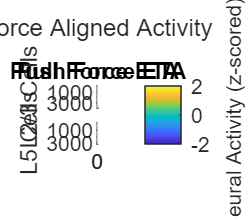

Plot saved to C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\C6J501_C6J506_tph578_norm2/force_activity_heatmap.svg


        7096



  246.5625



  196.9375



% plot for Cosyne 2026 abstract 
if strcmp(categorize, 'layer') == 1
    if norm == 1
        climit = [0 1];
    elseif norm == 2 | norm == 3 | norm == 4 | norm == 5
        climit = [-2 2];
    elseif norm == 6
        climit = [-4 4];
    else
        climit = [0 50];
    end
    
    layer23_act = {trial_start_act_layer23_conc, trial_end_act_layer23_conc, position_act_layer23_conc, force_act_layer23_conc, force_act2_layer23_conc, reward_act_layer23_conc};
    layer5_act  = {trial_start_act_layer5_conc, trial_end_act_layer5_conc, position_act_layer5_conc, force_act_layer5_conc, force_act2_layer5_conc, reward_act_layer5_conc};
    
    % --- プロットの開始 ---
    fig = figure('Position', [10, 10, 400, 350]);
    set(gcf, 'color', 'w'); % 背景を白に
    
    % 2x2のレイアウトを作成
    t = tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(t, 'Force Aligned Activity', 'FontSize', 8);
    
    % X軸（時間）を定義
    x_time = -before_event : 0.1 : after_event;
    
    %% --- 1. L2/3 Pull Force ---
    ax1 = nexttile;
    imagesc(x_time, 1:size(layer23_act{4}, 1), layer23_act{4}, climit);
    disp(size(layer23_act{4}, 1))
    hold on;
    xline(0, 'w--', 'LineWidth', 0.5); % Time=0に白い縦の点線
    hold off;
    title('Pull Force ETA'); % ★ タイトルを変更
    ylabel('L2/3 Cells');
    
    %% --- 2. L2/3 Push Force ---
    ax2 = nexttile;
    imagesc(x_time, 1:size(layer23_act{5}, 1), layer23_act{5}, climit);
    disp(size(layer23_act{5}, 1))
    hold on;
    xline(0, 'w--', 'LineWidth', 0.5);
    hold off;
    title('Push Force ETA'); % ★ タイトルを変更
    
    %% --- 3. L5 Pull Force ---
    ax3 = nexttile;
    imagesc(x_time, 1:size(layer5_act{4}, 1), layer5_act{4}, climit);
    disp(size(layer5_act{4}, 1))
    hold on;
    xline(0, 'w--', 'LineWidth', 0.5);
    hold off;
    ylabel('L5 Cells');
    xlabel('Time from onset (s)');
    
    %% --- 4. L5 Push Force ---
    ax4 = nexttile;
    imagesc(x_time, 1:size(layer5_act{5}, 1), layer5_act{5}, climit);
    disp(size(layer5_act{5}, 1))
    hold on;
    xline(0, 'w--', 'LineWidth', 0.5);
    hold off;
    xlabel('Time from onset (s)');
    
    %% --- スタイルの適用 ---
    all_axes = [ax1, ax2, ax3, ax4];
    for i = 1:length(all_axes)
        set(all_axes(i), ...
            'box', 'off', ...
            'TickDir', 'out', ...
            'FontSize', 7);
    end
    set([ax1, ax2], 'XTickLabel', []);
    set([ax2, ax4], 'YTickLabel', []);
    
    %% --- カラーバーの調整 ---
    cb = colorbar(ax4);
    cb.Layout.Tile = 'east';
    cb.Label.String = 'Neural Activity (z-scored)';
    cb.FontSize = 7;
    
    % ★ カラーバーを小さくする
    % カラーバーの位置 [left, bottom, width, height] を取得
    original_pos = cb.Position;
    % 幅を元の50%に設定して、見た目を細くする
    cb.Position = [original_pos(1), original_pos(2), original_pos(3) * 0.5, original_pos(4)];
    
    %% --- SVG形式で保存 ---
    filename = [output_dir 'force_activity_heatmap.svg'];
    print(gcf, filename, '-dsvg', '-r300');
    
    fprintf('Plot saved to %s\n', filename);
    disp(size(layer23_act{5}, 1)+size(layer5_act{5}, 1))
    disp(size(layer23_act{5}, 1)/16)
    disp(size(layer5_act{5}, 1)/16)
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
    % pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    % pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_act_layer23_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        % NaNを含む行を削除
        image = image(~any(isnan(image), 2), :);
        imagesc(-before_event:0.1:after_event,1:size(pull_act_layer23_cells{i},1),image,clims);
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;           
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer23_eta_activity_heatmap.png'];
    filename = [output_dir 'pull_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data = pull_act_layer23_cells{i};
        data = data(~any(isnan(data), 2), :);
        z = zscore(data, 0, 1); % 列方向に Zスコアを計算
        data = data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去
 
        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);      
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end      
        hold off;
        axis tight;  
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
        
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer23_eta_activity.png'];
    filename = [output_dir  'pull_layer23_eta_activity.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_act_layer5_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        % NaNを含む行を削除
        image = image(~any(isnan(image), 2), :);        
        imagesc(-before_event:0.1:after_event,1:size(pull_act_layer5_cells{i},1),image,clims);
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;          
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer5_eta_activity_heatmap.png'];
    filename = [output_dir 'pull_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data = pull_act_layer5_cells{i};
        data = data(~any(isnan(data), 2), :);
        z = zscore(data, 0, 1); % 列方向に Zスコアを計算
        data = data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);              
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end       
        hold off;
        axis tight;          
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end     
        if i == 1
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer5_eta_activity.png'];
    filename = [output_dir 'pull_layer5_eta_activity.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data23 = pull_act_layer23_cells{i};
        data23 = data23(~any(isnan(data23), 2), :);
        data5 = pull_act_layer5_cells{i};
        data5 = data5(~any(isnan(data5), 2), :);        
        z23 = zscore(data23, 0, 1); z5 = zscore(data5, 0, 1);% 列方向に Zスコアを計算
        data23 = data23(max(abs(z23), [], 2) < 10, :); data5 = data5(max(abs(z5), [], 2) < 10, :); % Zスコアが100以上の行を除去

        % mean_values = mean(data, 1);
        % std_values = std(data, 0, 1);              
        mean_values23 = mean(data23, 1);
        std_values23 = std(data23, 0, 1);        
        mean_values5 = mean(data5, 1);
        std_values5 = std(data5, 0, 1);
        x = -before_event:0.1:after_event;

        hold on;        
        fill([x, fliplr(x)], [mean_values23 + std_values23, fliplr(mean_values23 - std_values23)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values23, 'g', 'LineWidth', 1.5); 
        fill([x, fliplr(x)], [mean_values5 + std_values5, fliplr(mean_values5 - std_values5)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values5, 'b', 'LineWidth', 1.5);         
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end        
        hold off;
        axis tight;  
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end      
        if i == 1
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer235_eta_activity.png'];
    filename = [output_dir 'pull_layer235_eta_activity.png'];
    saveas(gcf,filename);
    close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    title_list = {'Heavy - Light', 'Exp heavy - Unexp heavy', 'Exp light - Unexp light', 'Exp heavy - Unexp heavy - Exp light - Unexp light'};

    figure('Position', [100, 100, 1600, 600]);
    for i = 1:4
        subaxis(1,4,i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.08);
        % NaNを含む行を削除
        if i == 1
            data1 = pull_act_layer23_cells{1}; data2 = pull_act_layer23_cells{2};
            data11 = pull_act_layer5_cells{1}; data21 = pull_act_layer5_cells{2};            
        elseif i == 4
            data1 = pull_act_layer23_cells{3}; data2 = pull_act_layer23_cells{5};   
            data3 = pull_act_layer23_cells{4}; data4 = pull_act_layer23_cells{6};
            data11 = pull_act_layer5_cells{3}; data21 = pull_act_layer5_cells{5};   
            data31 = pull_act_layer5_cells{4}; data41 = pull_act_layer5_cells{6};            
        else
            data1 = pull_act_layer23_cells{i+1}; data2 = pull_act_layer23_cells{i+3};
            data11 = pull_act_layer5_cells{i+1}; data21 = pull_act_layer5_cells{i+3};            
        end
        data1 = data1(~any(isnan(data1), 2), :); data2 = data2(~any(isnan(data2), 2), :);
        data11 = data11(~any(isnan(data11), 2), :); data21 = data21(~any(isnan(data21), 2), :);         
        z1 = zscore(data1, 0, 1); z2 = zscore(data2, 0, 1); % 列方向に Zスコアを計算
        data1 = data1(max(abs(z1), [], 2) < 10, :); data2 = data2(max(abs(z2), [], 2) < 10, :); % Zスコアが100以上の行を除去
        z11 = zscore(data11, 0, 1); z21 = zscore(data21, 0, 1); % 列方向に Zスコアを計算
        data11 = data11(max(abs(z11), [], 2) < 10, :); data21 = data21(max(abs(z21), [], 2) < 10, :); % Zスコアが100以上の行を除去
        mean_values1 = mean(data1, 1); mean_values2 = mean(data2, 1);
        std_values1 = std(data1, 0, 1); std_values2 = std(data2, 1);
        mean_values11 = mean(data11, 1); mean_values21 = mean(data21, 1);
        std_values11 = std(data11, 0, 1); std_values21 = std(data21, 1);         
        if i == 4
            data3 = data3(~any(isnan(data3), 2), :); data4 = data4(~any(isnan(data4), 2), :); 
            data31 = data31(~any(isnan(data31), 2), :); data41 = data41(~any(isnan(data41), 2), :);             
            z3 = zscore(data3, 0, 1); z4 = zscore(data4, 0, 1); % 列方向に Zスコアを計算
            data3 = data3(max(abs(z3), [], 2) < 10, :); data4 = data4(max(abs(z4), [], 2) < 10, :); % Zスコアが100以上の行を除去
            z31 = zscore(data31, 0, 1); z41 = zscore(data41, 0, 1); % 列方向に Zスコアを計算
            data31 = data31(max(abs(z31), [], 2) < 10, :); data41 = data41(max(abs(z41), [], 2) < 10, :); % Zスコアが100以上の行を除去
            mean_values31 = mean(data31, 1); mean_values41 = mean(data41, 1);
            std_values31 = std(data31, 0, 1); std_values41 = std(data41, 1);             
        end
        x = -before_event:0.1:after_event;
      
        if i == 1
            hold on;
            plot(x, mean_values1,  'Color', [0 0.5 0], 'LineWidth', 1.5); 
            plot(x, mean_values2, 'Color', [0.5 1 0], 'LineWidth', 1.5); 
            plot(x, mean_values11, 'b', 'LineWidth', 1.5); 
            plot(x, mean_values21, 'c', 'LineWidth', 1.5);             
        elseif i == 2
            hold on;
            plot(x, mean_values1, 'Color', [0 0.5 0], 'LineWidth', 1.5); 
            plot(x, mean_values2, 'Color', [0 0.5 0], 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values11, 'b', 'LineWidth', 1.5); 
            plot(x, mean_values21, 'b', 'LineWidth', 1.5,'LineStyle', ':');            
        elseif i == 3
            hold on;
            plot(x, mean_values1, 'Color', [0.5 1 0], 'LineWidth', 1.5); 
            plot(x, mean_values2, 'Color', [0.5 1 0], 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values11, 'c', 'LineWidth', 1.5); 
            plot(x, mean_values21, 'c', 'LineWidth', 1.5,'LineStyle', ':');               
        else
            hold on;
            plot(x, mean_values1, 'Color', [0 0.5 0], 'LineWidth', 1.5); 
            plot(x, mean_values2, 'Color', [0 0.5 0], 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values3, 'Color', [0.5 1 0], 'LineWidth', 1.5); 
            plot(x, mean_values4, 'Color', [0.5 1 0], 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values11, 'b', 'LineWidth', 1.5); 
            plot(x, mean_values21, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values31, 'c', 'LineWidth', 1.5); 
            plot(x, mean_values41, 'c', 'LineWidth', 1.5,'LineStyle', ':');             
        end
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});        
         axis tight;
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 2]); %ylim([-1 6]); %
        end
    end
        
        % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer235_eta_activity_compare.png'];
        filename = [output_dir 'pull_layer235_eta_activity_compare.png'];
        saveas(gcf,filename);
    close all;
end

close all;close(gcf);

% 階層的クラスタリングの実施

if Kota_alignment == 1
    % NaNを含む行を削除
    data = pull_actss{length(AlinmentTimingCells)+1};
    data = data(~any(isnan(data), 2), :);
    % 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
    linkage_matrix = linkage(data, 'ward');
    
    % 樹形図の作成
    figure('Position', [100, 100, 800, 600]);
    [H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
    % title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
    xlabel('Cell');
    ylabel('Distance');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_hierarchical_clustering_dendrogram.png'];
    filename = [output_dir 'hierarchical_clustering_dendrogram.png'];
    saveas(gcf,filename);    
    
    % 順序付けされたdata
    ordered_data = data(outperm, :);
    
    % エルボー法のためのプロット作成
    figure('Position', [100, 100, 800, 600]);
    last = linkage_matrix(end-9:end, 3);
    last_rev = flipud(last);
    indexes = 1:length(last);
    hold on
    plot(indexes, last_rev, 'b-o');
    acceleration = diff(last, 2);  % 2次の微分を計算
    acceleration_rev = zeros(10,1);
    acceleration_rev(2:end-1) = flipud(acceleration);
    plot(indexes, acceleration_rev, 'r-o');
    hold off
    xlabel('Number of clusters');
    ylabel('Distance');
    % title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_elbow.png'];
    filename = [output_dir 'elbow.png'];
    saveas(gcf,filename);     
    
    % 相関行列の表示
    figure('Position', [100, 100, 800, 600]);
    imagesc(ordered_data, [0 1]);
    colorbar;
    % title(title_list{i});  %title('Correlation Matrix');
    xlabel('Cell');
    ylabel('Time (sec)');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_eta_heatmap2.png'];
    filename = [output_dir 'eta_heatmap2.png'];
    saveas(gcf,filename);         
        % colormap('viridis');
    % end
    close(gcf);
end

% plot clustered ETA neural activity
if Kota_alignment == 1
    num_clusters = 5; % クラスター数を指定（必要に応じて変更）
    % クラスタリングの実行
    cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
    all_cluster_labels = cluster_labels;
    unique_elements = unique(cluster_labels);
    counts = histc(cluster_labels, unique_elements);
    for n = 1:length(unique_elements)
        fprintf('Element %d: %d cells\n', unique_elements(n),counts(n));
    end

    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};

    fig_y = 600*num_clusters;
    % figure('Position', [100, 100, fig_y, 2400]);
    figure('Position', [100, 100, 2400, fig_y]);    
    for i = 1:length(AlinmentTimingCells)
        % NaNを含む行を削除
        i_data = pull_actss{i};
        % i_data = i_data(~any(isnan(i_data), 2), :);
        % % hierarchical clustering
        % linkage_matrix = linkage(data, 'ward');
        % % クラスタリングの実行
        % cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
        for cluster_num = 1:num_clusters   
            % subaxis(num_clusters,length(AlinmentTimingCells),(i-1)*length(AlinmentTimingCells)+cluster_num, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            subaxis(num_clusters,length(AlinmentTimingCells),i+length(AlinmentTimingCells)*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data = i_data(cluster_labels == cluster_num, :);
            cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);
            z = zscore(cluster_data, 0, 1); % 列方向に Zスコアを計算
            cluster_data = cluster_data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

            mean_values = mean(cluster_data, 1);
            std_values = std(cluster_data, 0, 1);
            x = -before_event:0.1:after_event;
          
            fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values, 'b', 'LineWidth', 1.5); 
            % xlim = [-2,4]
            % x=0に赤い縦線をプロット       
            % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if i == 1
                ylabel('normalized activity');
            end
            if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            if cluster_num == 1
                title(title_list{i});
            end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 24]); %ylim([-6 12]);
            end
        end
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_eta_activity.png'];
    filename = [output_dir 'clustered_pull_eta_activity.png'];
    saveas(gcf,filename);
    close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    title_list = {'Heavy - Light', 'Exp heavy - Unexp heavy', 'Exp light - Unexp light', 'Exp heavy - Unexp heavy - Exp light - Unexp light'};
    fig_y = 400*num_clusters;
    % fig_y = 600*num_clusters;
    figure('Position', [100, 100, fig_y, 2400]);
    % figure('Position', [100, 100, 1600, fig_y]);
    for i = 1:4
        % NaNを含む行を削除
        if i == 1
            data1 = pull_actss{1}; data2 = pull_actss{2};
        elseif i == 4
            data1 = pull_actss{3}; data2 = pull_actss{5};   
            data3 = pull_actss{4}; data4 = pull_actss{6};
        else
            data1 = pull_actss{i+1}; data2 = pull_actss{i+3};
        end        
        % i_data = pull_actss{i};
        % i_data = i_data(~any(isnan(data), 2), :);

        for cluster_num = 1:num_clusters
            subaxis(4,num_clusters,(i-1)*num_clusters+cluster_num, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);            
            % subaxis(num_clusters,4,i+4*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data1 = data1(cluster_labels == cluster_num, :); cluster_data2 = data2(cluster_labels == cluster_num, :);
            cluster_data1 = cluster_data1(~any(isnan(cluster_data1), 2), :); cluster_data2 = cluster_data2(~any(isnan(cluster_data2), 2), :);
            z1 = zscore(cluster_data1, 0, 1); z2 = zscore(cluster_data2, 0, 1); % 列方向に Zスコアを計算
            cluster_data1 = cluster_data1(max(abs(z1), [], 2) < 10, :); cluster_data2 = cluster_data2(max(abs(z2), [], 2) < 10, :); % Zスコアが100以上の行を除去

            mean_values1 = mean(cluster_data1, 1); mean_values2 = mean(cluster_data2, 1);
            std_values1 = std(cluster_data1, 0, 1); std_values2 = std(cluster_data2, 0, 1);
            if i == 4
                cluster_data3 = data3(cluster_labels == cluster_num, :); cluster_data4 = data4(cluster_labels == cluster_num, :);
                cluster_data3 = cluster_data3(~any(isnan(cluster_data3), 2), :); cluster_data4 = cluster_data4(~any(isnan(cluster_data4), 2), :);   
                z3 = zscore(cluster_data3, 0, 1); z4 = zscore(cluster_data4, 0, 1); % 列方向に Zスコアを計算
                cluster_data3 = cluster_data3(max(abs(z3), [], 2) < 10, :); cluster_data4 = cluster_data4(max(abs(z4), [], 2) < 10, :); % Zスコアが100以上の行を除去
                mean_values3 = mean(cluster_data3, 1); mean_values4 = mean(cluster_data4, 1);
                std_values3 = std(cluster_data3, 0, 1); std_values4 = std(cluster_data4, 0, 1);           
            end            
            x = -before_event:0.1:after_event;
          
            % fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            % hold on;
            % plot(x, mean_values, 'b', 'LineWidth', 1.5); 
            if i == 1
                % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                hold on;
                plot(x, mean_values1, 'Color', [0 0 0.5], 'LineWidth', L_width);
                plot(x, mean_values2, 'Color', [0 0.8 1.0], 'LineWidth', L_width);               
                % plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
                % % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                % plot(x, mean_values2, 'c', 'LineWidth', 1.5); 
            elseif i == 2
                % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                hold on;
                plot(x, mean_values1, 'Color', [0 0 0.5], 'LineWidth', L_width);
                % plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
                % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values2, 'Color', [0 0 0.5], 'LineWidth', L_width,'LineStyle', ':');
                % plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
            elseif i == 3
                % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                hold on;
                plot(x, mean_values1, 'Color', [0 0.8 1.0], 'LineWidth', L_width); 
                % plot(x, mean_values1, 'c', 'LineWidth', 1.5); 
                % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values2, 'Color', [0 0.8 1.0], 'LineWidth', L_width,'LineStyle', ':'); 
                % plot(x, mean_values2, 'c', 'LineWidth', 1.5,'LineStyle', ':');             
            else
                % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                hold on;
                plot(x, mean_values1, 'Color', [0 0 0.5], 'LineWidth', L_width);
                % plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
                % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values2, 'Color', [0 0 0.5], 'LineWidth', L_width,'LineStyle', ':');                
                plot(x, mean_values3, 'Color', [0 0.8 1.0], 'LineWidth', L_width); 
                % plot(x, mean_values1, 'c', 'LineWidth', 1.5); 
                % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values4, 'Color', [0 0.8 1.0], 'LineWidth', L_width,'LineStyle', ':');                 
                % plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
                % % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                % plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
                % % fill([x, fliplr(x)], [mean_values3 + std_values3, fliplr(mean_values3 - std_values3)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                % plot(x, mean_values3, 'c', 'LineWidth', 1.5); 
                % % fill([x, fliplr(x)], [mean_values4 + std_values4, fliplr(mean_values4 - std_values4)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                % plot(x, mean_values4, 'c', 'LineWidth', 1.5,'LineStyle', ':');            
            end            
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', L_width); % x=0 に赤い縦線を描画
            end
            hold off;
            if cluster_num == 1
            % if i == 1
                ylabel('normalized activity');
            end
            if i == 4
            % if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            % if cluster_num == 1
            %     title(title_list{i});
            % end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 12]); %ylim([-6 12]);
            end
        end
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_eta_activity_compare.png'];
    filename = [output_dir 'clustered_pull_eta_activity_compare.png'];
    saveas(gcf,filename);
    % close all;
end

% Layer23 階層的クラスタリングの実施

if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    % NaNを含む行を削除
    data = pull_act_layer23_cells{length(AlinmentTimingCells)+1};
    data = data(~any(isnan(data), 2), :);
    % 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
    linkage_matrix = linkage(data, 'ward');
    
    % 樹形図の作成
    figure('Position', [100, 100, 800, 600]);
    [H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
    % title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
    xlabel('Cell');
    ylabel('Distance');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_hierarchical_clustering_dendrogram.png'];
    filename = [output_dir 'layer23_hierarchical_clustering_dendrogram.png'];
    saveas(gcf,filename);    
    
    % 順序付けされたdata
    ordered_data = data(outperm, :);
    
    % エルボー法のためのプロット作成
    figure('Position', [100, 100, 800, 600]);
    last = linkage_matrix(end-9:end, 3);
    last_rev = flipud(last);
    indexes = 1:length(last);
    hold on
    plot(indexes, last_rev, 'b-o');
    acceleration = diff(last, 2);  % 2次の微分を計算
    acceleration_rev = zeros(10,1);
    acceleration_rev(2:end-1) = flipud(acceleration);
    plot(indexes, acceleration_rev, 'r-o');
    hold off
    xlabel('Number of clusters');
    ylabel('Distance');
    % title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_elbow.png'];
    filename = [output_dir 'layer23_elbow.png']; 
    saveas(gcf,filename);     
    
    % 相関行列の表示
    figure('Position', [100, 100, 800, 600]);
    imagesc(ordered_data, [0 1]);
    colorbar;
    % title(title_list{i});  %title('Correlation Matrix');
    xlabel('Cell');
    ylabel('Time (sec)');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_eta_heatmap2.png'];
    filename = [output_dir 'layer23_eta_heatmap2.png'];
    saveas(gcf,filename);         
        % colormap('viridis');
    % end
end

% plot clustered ETA neural activity
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    num_clusters = 4; % クラスター数を指定（必要に応じて変更）
    % クラスタリングの実行
    cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
    unique_elements = unique(cluster_labels);
    counts = histc(cluster_labels, unique_elements);
    for n = 1:length(unique_elements)
        fprintf('Element %d: %d cells\n', unique_elements(n),counts(n));
    end

    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};

    fig_y = 600*num_clusters;
    figure('Position', [100, 100, 2400, fig_y]);
    for i = 1:length(AlinmentTimingCells)
        % NaNを含む行を削除
        i_data = pull_act_layer23_cells{i};
        i_data = i_data(~any(isnan(data), 2), :);
        % % hierarchical clustering
        % linkage_matrix = linkage(data, 'ward');
        % % クラスタリングの実行
        % cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
        for cluster_num = 1:num_clusters
            subaxis(num_clusters,length(AlinmentTimingCells),i+length(AlinmentTimingCells)*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data = i_data(cluster_labels == cluster_num, :);
            cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);
            z = zscore(cluster_data, 0, 1); % 列方向に Zスコアを計算
            cluster_data = cluster_data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

            mean_values = mean(cluster_data, 1);
            std_values = std(cluster_data, 0, 1);
            x = -before_event:0.1:after_event;
          
            fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values, 'g', 'LineWidth', 1.5); 
            % xlim = [-2,4]
            % x=0に赤い縦線をプロット       
            % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if i == 1
                ylabel('normalized activity');
            end
            if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            if cluster_num == 1
                title(title_list{i});
            end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 24]); %ylim([-6 12]);
            end
        end
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_layer23_eta_activity.png'];
    filename = [output_dir 'clustered_pull_layer23_eta_activity.png'];
    saveas(gcf,filename);
    close all;
end

% Layer5 階層的クラスタリングの実施

if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    % NaNを含む行を削除
    data = pull_act_layer5_cells{length(AlinmentTimingCells)+1};
    data = data(~any(isnan(data), 2), :);
    % 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
    linkage_matrix = linkage(data, 'ward');
    
    % 樹形図の作成
    figure('Position', [100, 100, 800, 600]);
    [H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
    % title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
    xlabel('Cell');
    ylabel('Distance');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_hierarchical_clustering_dendrogram.png'];
    filename = [output_dir 'layer5_hierarchical_clustering_dendrogram.png'];
    saveas(gcf,filename);    
    
    % 順序付けされたdata
    ordered_data = data(outperm, :);
    
    % エルボー法のためのプロット作成
    figure('Position', [100, 100, 800, 600]);
    last = linkage_matrix(end-9:end, 3);
    last_rev = flipud(last);
    indexes = 1:length(last);
    hold on
    plot(indexes, last_rev, 'b-o');
    acceleration = diff(last, 2);  % 2次の微分を計算
    acceleration_rev = zeros(10,1);
    acceleration_rev(2:end-1) = flipud(acceleration);
    plot(indexes, acceleration_rev, 'r-o');
    hold off
    xlabel('Number of clusters');
    ylabel('Distance');
    % title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_elbow.png'];
    filename = [output_dir 'layer5_elbow.png'];
    saveas(gcf,filename);     
    
    % 相関行列の表示
    figure('Position', [100, 100, 800, 600]);
    imagesc(ordered_data, [0 1]);
    colorbar;
    % title(title_list{i});  %title('Correlation Matrix');
    xlabel('Cell');
    ylabel('Time (sec)');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_eta_heatmap2.png'];
    filename = [output_dir 'layer5_eta_heatmap2.png'];
    saveas(gcf,filename);         
        % colormap('viridis');
    % end
end

% plot clustered ETA neural activity
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    num_clusters = 3; % クラスター数を指定（必要に応じて変更）
    % クラスタリングの実行
    cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
    unique_elements = unique(cluster_labels);
    counts = histc(cluster_labels, unique_elements);
    for n = 1:length(unique_elements)
        fprintf('Element %d: %d cells\n', unique_elements(n),counts(n));
    end

    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};

    fig_y = 600*num_clusters;
    figure('Position', [100, 100, 2400, fig_y]);
    for i = 1:length(AlinmentTimingCells)
        % NaNを含む行を削除
        i_data = pull_act_layer5_cells{i};
        i_data = i_data(~any(isnan(data), 2), :);
        % % hierarchical clustering
        % linkage_matrix = linkage(data, 'ward');
        % % クラスタリングの実行
        % cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
        for cluster_num = 1:num_clusters
            subaxis(num_clusters,length(AlinmentTimingCells),i+length(AlinmentTimingCells)*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data = i_data(cluster_labels == cluster_num, :);
            cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);
             z = zscore(cluster_data, 0, 1); % 列方向に Zスコアを計算
            cluster_data = cluster_data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

            mean_values = mean(cluster_data, 1);
            std_values = std(cluster_data, 0, 1);
            x = -before_event:0.1:after_event;
          
            fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values, 'b', 'LineWidth', 1.5); 
            % xlim = [-2,4]
            % x=0に赤い縦線をプロット       
            % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if i == 1
                ylabel('normalized activity');
            end
            if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            if cluster_num == 1
                title(title_list{i});
            end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 24]); %ylim([-6 12]);
            end
        end
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_layer5_eta_activity.png'];
    filename = [output_dir 'clustered_pull_layer5_eta_activity.png'];
    saveas(gcf,filename);
    close all;
end

% check the ratio of cells in each layer in each cluster
% all_cluster_labels
% pointAreas_conc
if Kota_alignment == 1
    unique_pairs = unique([all_cluster_labels, pointAreas_conc], 'rows');
    counts = zeros(size(unique_pairs, 1), 1);
    
    for i = 1:size(unique_pairs, 1)
        counts(i) = sum(ismember([all_cluster_labels, pointAreas_conc], unique_pairs(i, :), 'rows'));
    end
    
    for i = 1:size(unique_pairs, 1)
        fprintf('Pair (%d, %d): %d times\n', unique_pairs(i, 1), unique_pairs(i, 2), counts(i));
    end
end

if Kota_alignment == 1
    % ユニークな要素を見つける
    unique_list2 = unique(pointAreas_conc);
    
    % Figureの作成
    figure('Position', [100, 100, 2400, 600]);
    
    % 各カテゴリーごとにプロット
    num_categories = length(unique_list2);
    for i = 1:num_categories
        category = unique_list2(i);
        indices = pointAreas_conc == category;
        subset_list1 = all_cluster_labels(indices);
        
        % List1のカテゴリーの割合を計算
        unique_subset_list1 = unique(subset_list1);
        counts = histc(subset_list1, unique_subset_list1);
        percentages = counts / sum(counts) * 100;
        
        % 円グラフをプロット
        subplot(1, num_categories, i);
        % pie(percentages, arrayfun(@num2str, unique_subset_list1, 'UniformOutput', false));
        pie(percentages, arrayfun(@(x) [num2str(counts(x == unique_subset_list1)) ' - ' num2str(round(percentages(x == unique_subset_list1), 2)) '%'], unique_subset_list1, 'UniformOutput', false));
        legend(arrayfun(@num2str, unique_subset_list1, 'UniformOutput', false), 'Location', 'southoutside', 'Orientation', 'horizontal');    
        if category == 0
            title(['Layer 5']);
        else
            title(['Layer 23']);
        end
    end
    
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer235_cluster_percentage.png'];
     filename = [output_dir 'layer235_cluster_percentage.png'];
    saveas(gcf,filename);
end

% plot ratio of significantly activated cells
if norm == 3 & Kota_alignment == 1
    %Actual resistance cell ratio
    % テキストファイルのオープン
    txtname = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_sig_cell_ratio.txt'];
    fileID = fopen(txtname, 'w');
    % Figureの作成
    figure('Position', [100, 100, 2400, 600]);
    legend({'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'}, 'Location', 'eastoutside'); 
    title_list = [{'All activated','After activated','After deactivated','Before activated', 'Before deactivated', 'Surprise activated', 'Surprise deactivated'}];
    h_sig_idxs = pull_sig_cell_idxs{1};
    l_sig_idxs = pull_sig_cell_idxs{2};
    for i_sig = 1:size(pull_sig_cell_idxs{1},1)
        h_sig_idx = h_sig_idxs(i_sig,:);
        l_sig_idx = l_sig_idxs(i_sig,:);
        
        % 組み合わせの個数をカウント
        both_one = sum(h_sig_idx == 1 & l_sig_idx == 1);
        h_one_l_zero = sum(h_sig_idx == 1 & l_sig_idx == 0);
        h_zero_l_one = sum(h_sig_idx == 0 & l_sig_idx == 1);
        both_zero = sum(h_sig_idx == 0 & l_sig_idx == 0);
               
        % 円グラフ用のデータ
        total = length(h_sig_idx);
        data = [both_one, h_one_l_zero, h_zero_l_one, both_zero]; %/length(h_sig_idx)*100;
        % labels = {'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'};

        % % 円グラフ用のラベル
        % labels = {
        %     ['Heavy and light pull: ', num2str(both_one), ' (', num2str(both_one / total * 100, '%.2f'), '%)'], ...
        %     ['Heavy pull: ', num2str(h_one_l_zero), ' (', num2str(h_one_l_zero / total * 100, '%.2f'), '%)'], ...
        %     ['Light pull: ', num2str(h_zero_l_one), ' (', num2str(h_zero_l_one / total * 100, '%.2f'), '%)'], ...
        %     ['Neither: ', num2str(both_zero), ' (', num2str(both_zero / total * 100, '%.2f'), '%)']
        % };
        % カウントの結果をテキストファイルに書き込む
        fprintf(fileID, 'Signal %d\n', i_sig);
        fprintf(fileID, 'Heavy and light pull: %d (%.2f%%)\n', both_one, both_one / total * 100);
        fprintf(fileID, 'Heavy pull: %d (%.2f%%)\n', h_one_l_zero, h_one_l_zero / total * 100);
        fprintf(fileID, 'Light pull: %d (%.2f%%)\n', h_zero_l_one, h_zero_l_one / total * 100);
        fprintf(fileID, 'Neither: %d (%.2f%%)\n', both_zero, both_zero / total * 100);
        fprintf(fileID, '\n');        
        
        % 円グラフのプロット
        subplot(1, size(pull_sig_cell_idxs{1},1), i_sig);      
        pie(data, {'', '', '', ''});
        colormap([0 0 0; 0 0 1; 0 1 1; 0.5 0.5 0.5]); % 黒、濃い青、水色、灰色
        title(title_list{i_sig});        
    end   
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_actual_res_sig_cell_ratio.png'];
    filename = [output_dir 'actual_res_sig_cell_ratio.png'];
    saveas(gcf,filename);
    % Resistance Expected vs Unexpected cell ratio
    % Figureの作成
    figure('Position', [100, 100, 2400, 600]);
    legend({'Expected and unexpected pull', 'Expected pull', 'Unexpected pull', 'Neither'}, 'Location', 'eastoutside');     
    title_list = [{'All activated','After activated','After deactivated','Before activated', 'Before deactivated', 'Surprise activated', 'Surprise deactivated'}];
    e_sig_idxs = pull_sig_cell_idxs{3} | pull_sig_cell_idxs{4};
    u_sig_idxs = pull_sig_cell_idxs{5} | pull_sig_cell_idxs{6};
    for i_sig = 1:size(pull_sig_cell_idxs{1},1)
        e_sig_idx = e_sig_idxs(i_sig,:);
        u_sig_idx = u_sig_idxs(i_sig,:);
        
        % 組み合わせの個数をカウント
        both_one = sum(e_sig_idx == 1 & u_sig_idx == 1);
        e_one_u_zero = sum(e_sig_idx == 1 & u_sig_idx == 0);
        e_zero_u_one = sum(e_sig_idx == 0 & u_sig_idx == 1);
        both_zero = sum(e_sig_idx == 0 & u_sig_idx == 0);
        
        % 円グラフ用のデータ
        total = length(e_sig_idx);
        data = [both_one, e_one_u_zero, e_zero_u_one, both_zero]; %/length(e_sig_idx)*100;
        % labels = {'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'};
    
        % カウントの結果をテキストファイルに書き込む
        fprintf(fileID, 'Signal %d\n', i_sig);
        fprintf(fileID, 'Expected and unexpected pull: %d (%.2f%%)\n', both_one, both_one / total * 100);
        fprintf(fileID, 'Expected pull: %d (%.2f%%)\n', e_one_u_zero, e_one_u_zero / total * 100);
        fprintf(fileID, 'Unexpected pull: %d (%.2f%%)\n', e_zero_u_one, e_zero_u_one / total * 100);
        fprintf(fileID, 'Neither: %d (%.2f%%)\n', both_zero, both_zero / total * 100);
        fprintf(fileID, '\n');          
        
        % 円グラフのプロット
        subplot(1, size(pull_sig_cell_idxs{1},1), i_sig);      
        pie(data, {'', '', '', ''}); 
        colormap([0 0 0; 0 0.5 0; 0.5 1 0; 0.5 0.5 0.5]); % 黒、緑、淡い緑、灰色
        title(title_list{i_sig});
    end    
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_expect_res_sig_cell_ratio.png'];
    filename = [output_dir 'expect_res_sig_cell_ratio.png'];
    saveas(gcf,filename);

    % テキストファイルのクローズ
    fclose(fileID);    
end

% plot ratio of significantly activated cells
if norm == 3 & strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    %Actual resistance cell ratio
    % ユニークな要素を見つける
    unique_list2 = unique(pointAreas_conc);
    % 各カテゴリーごとにプロット
    num_categories = length(unique_list2);  
    % テキストファイルのオープン
    txtname = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer_sig_cell_ratio.txt'];
    fileID = fopen(txtname, 'w');    
    % Figureの作成
    figure('Position', [100, 100, 2400, 1200]);
    legend({'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'}, 'Location', 'eastoutside');     
    title_list = [{'All activated','After activated','After deactivated','Before activated', 'Before deactivated', 'Surprise activated', 'Surprise deactivated'}];
    h_sig_idxs = pull_sig_cell_idxs{1};h_sig_idxs_ori = pull_sig_cell_idxs{1};
    l_sig_idxs = pull_sig_cell_idxs{2};l_sig_idxs_ori = pull_sig_cell_idxs{2};
    for i = 1:num_categories
        category = unique_list2(i);
        indices = pointAreas_conc == category;
        h_sig_idxs = h_sig_idxs_ori(:,indices);
        l_sig_idxs = l_sig_idxs_ori(:,indices);
        for i_sig = 1:size(pull_sig_cell_idxs{1},1)
            h_sig_idx = h_sig_idxs(i_sig,:);
            l_sig_idx = l_sig_idxs(i_sig,:);
            
            % 組み合わせの個数をカウント
            both_one = sum(h_sig_idx == 1 & l_sig_idx == 1);
            h_one_l_zero = sum(h_sig_idx == 1 & l_sig_idx == 0);
            h_zero_l_one = sum(h_sig_idx == 0 & l_sig_idx == 1);
            both_zero = sum(h_sig_idx == 0 & l_sig_idx == 0);
   
            % 円グラフ用のデータ
            total = length(h_sig_idx);
            data = [both_one, h_one_l_zero, h_zero_l_one, both_zero]; %/length(h_sig_idx)*100;
            % labels = {'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'};
    
            % カウントの結果をテキストファイルに書き込む
            fprintf(fileID, 'Layer %d\n', i);
            fprintf(fileID, 'Signal %d\n', i_sig);
            fprintf(fileID, 'Heavy and light pull: %d (%.2f%%)\n', both_one, both_one / total * 100);
            fprintf(fileID, 'Heavy pull: %d (%.2f%%)\n', h_one_l_zero, h_one_l_zero / total * 100);
            fprintf(fileID, 'Light pull: %d (%.2f%%)\n', h_zero_l_one, h_zero_l_one / total * 100);
            fprintf(fileID, 'Neither: %d (%.2f%%)\n', both_zero, both_zero / total * 100);
            fprintf(fileID, '\n');              
            
            % 円グラフのプロット
            subplot(2, size(pull_sig_cell_idxs{1},1), (i-1)*7+i_sig);      
            pie(data, {'', '', '', ''});           
            colormap([0 0 0; 0 0 1; 0 1 1; 0.5 0.5 0.5]); % 黒、濃い青、水色、灰色
            % title(title_list{i_sig});
            if category == 0
                title(['Layer 5',title_list{i_sig}]);
            else
                title(['Layer 23',title_list{i_sig}]);
            end
        end
    end
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_actual_res_layer_sig_cell_ratio.png'];
    filename = [output_dir  'actual_res_layer_sig_cell_ratio.png'];
    saveas(gcf,filename);    
    % Resistance Expected vs Unexpected cell ratio
    % Figureの作成
    figure('Position', [100, 100, 2400, 1200]);
    legend({'Expected and unexpected pull', 'Expected pull', 'Unexpected pull', 'Neither'}, 'Location', 'eastoutside');     
    title_list = [{'All activated','After activated','After deactivated','Before activated', 'Before deactivated', 'Surprise activated', 'Surprise deactivated'}];
    e_sig_idxs = pull_sig_cell_idxs{3} | pull_sig_cell_idxs{4};e_sig_idxs_ori = pull_sig_cell_idxs{3} | pull_sig_cell_idxs{4};
    u_sig_idxs = pull_sig_cell_idxs{5} | pull_sig_cell_idxs{6};u_sig_idxs_ori = pull_sig_cell_idxs{5} | pull_sig_cell_idxs{6};
    for i = 1:num_categories
        category = unique_list2(i);
        indices = pointAreas_conc == category;
        e_sig_idxs = e_sig_idxs_ori(:,indices);
        u_sig_idxs = u_sig_idxs_ori(:,indices);
        for i_sig = 1:size(pull_sig_cell_idxs{1},1)
            e_sig_idx = e_sig_idxs(i_sig,:);
            u_sig_idx = u_sig_idxs(i_sig,:);
            
            % 組み合わせの個数をカウント
            both_one = sum(e_sig_idx == 1 & u_sig_idx == 1);
            e_one_u_zero = sum(e_sig_idx == 1 & u_sig_idx == 0);
            e_zero_u_one = sum(e_sig_idx == 0 & u_sig_idx == 1);
            both_zero = sum(e_sig_idx == 0 & u_sig_idx == 0);
            
            % 円グラフ用のデータ
            total = length(e_sig_idx);
            data = [both_one, e_one_u_zero, e_zero_u_one, both_zero]; %/length(e_sig_idx)*100;
            % labels = {'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'};
        
            % 円グラフ用のラベル
            labels = {
                ['Expected and unexpected pull: ', num2str(both_one), ' (', num2str(both_one / total * 100, '%.2f'), '%)'], ...
                ['Expected pull: ', num2str(e_one_u_zero), ' (', num2str(e_one_u_zero / total * 100, '%.2f'), '%)'], ...
                ['Unexpected pull: ', num2str(e_zero_u_one), ' (', num2str(e_zero_u_one / total * 100, '%.2f'), '%)'], ...
                ['Neither: ', num2str(both_zero), ' (', num2str(both_zero / total * 100, '%.2f'), '%)']
            };
            % カウントの結果をテキストファイルに書き込む
            fprintf(fileID, 'Layer %d\n', i);            
            fprintf(fileID, 'Signal %d\n', i_sig);
            fprintf(fileID, 'Expected and unexpected pull: %d (%.2f%%)\n', both_one, both_one / total * 100);
            fprintf(fileID, 'Expected pull: %d (%.2f%%)\n', e_one_u_zero, e_one_u_zero / total * 100);
            fprintf(fileID, 'Unexpected pull: %d (%.2f%%)\n', e_zero_u_one, e_zero_u_one / total * 100);
            fprintf(fileID, 'Neither: %d (%.2f%%)\n', both_zero, both_zero / total * 100);
            fprintf(fileID, '\n');              
            
            % 円グラフのプロット
            subplot(2, size(pull_sig_cell_idxs{1},1), (i-1)*7+i_sig);      
            pie(data, {'', '', '', ''});         
            colormap([0 0 0; 0 0.5 0; 0.5 1 0; 0.5 0.5 0.5]); % 黒、緑、淡い緑、灰色
            % title(title_list{i_sig});
            if category == 0
                title(['Layer 5',title_list{i_sig}]);
            else
                title(['Layer 23',title_list{i_sig}]);
            end
        end
    end
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_expect_res_layer_sig_cell_ratio.png'];
    filename = [output_dir '_expect_res_layer_sig_cell_ratio.png'];
    saveas(gcf,filename);   
    % テキストファイルのクローズ
    fclose(fileID); 
end

% scatter plot of peak after pull in each conditioins
if Kota_alignment == 1
    % 各ペアのスキャタープロット
    pairs = {[3, 5], [4, 6], [5, 6]};
    titles = {'pull_acts{3} vs pull_acts{5}', 'pull_acts{4} vs pull_acts{6}', 'pull_acts{5} vs pull_acts{6}'};
    
    figure('Position', [100, 100, 1800, 600]);
    
    % 全データの最大値と最小値を計算
    all_data = [];
    for i = 1:length(pairs)
        idx1 = pairs{i}(1);
        idx2 = pairs{i}(2);
        x_data = max(pull_actss{idx1}(:, 21:41), [], 2);
        y_data = max(pull_actss{idx2}(:, 21:41), [], 2);
        all_data = [all_data; x_data; y_data];
    end
    data_min = min(all_data);
    data_max = max(all_data);

    % 結果を保存するためのファイルを開く
    results_file = fopen([output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_results.txt'], 'w');
       
    for i = 1:length(pairs)
        idx1 = pairs{i}(1);
        idx2 = pairs{i}(2);
    
        % 21列目から41列目の最大値を計算
        x_data = max(pull_actss{idx1}(:, 21:41), [], 2);
        y_data = max(pull_actss{idx2}(:, 21:41), [], 2);
        
        valid_idx = ~isnan(x_data) & ~isnan(y_data);
        x_data = x_data(valid_idx);
        y_data = y_data(valid_idx);        

        % スキャタープロット
        subplot(1, 3, i);
        scatter(x_data, y_data, 'filled');
        hold on;
        
        % x=y, x=0, y=0の黒い点線を追加
        plot([data_min data_max], [data_min data_max], 'k--');
        plot([0 0], [data_min data_max], 'k--');
        plot([data_min data_max], [0 0], 'k--');
        
        % 相関を計算
        [R, P] = corr(x_data, y_data);

        % 相関の結果をテキストファイルに保存
        fprintf(results_file, '%s\n', titles{i});
        fprintf(results_file, 'Correlation: r = %.2f, p = %.2e\n', R, P);        
        
        % % 相関の結果をプロットに表示
        % text(data_min + (data_max-data_min)*0.05, data_max - (data_max-data_min)*0.1, ...
        %     sprintf('r = %.2f, p = %.2e', R, P), 'FontSize', 12);
        
        % x=y からのずれの統計的検定
        differences = y_data - x_data;
        mean(differences)
        [h, p_ttest, ci, stats] = ttest(differences);
        
        % 検定結果をテキストファイルに保存
        if h == 0
            test_result = 'No significant difference';
        else
            test_result = 'Significant difference';
        end        
        
        % text(data_min + (data_max-data_min)*0.05, data_max - (data_max-data_min)*0.2, ...
        %     sprintf('%s\np = %.2e', test_result, p_ttest), 'FontSize', 12);
        % 検定結果をテキストファイルに保存
        if h == 0
            test_result = 'No significant difference';
        else
            test_result = 'Significant difference';
        end        
        
        % x>y かつ x>1 の範囲にある点の数をカウント
        count_x_greater_y = sum(x_data > y_data & x_data > 1);
        % x<y かつ y>1 の範囲にある点の数をカウント
        count_y_greater_x = sum(x_data < y_data & y_data > 1);
        % 全体の点の数
        total_points = count_x_greater_y+count_y_greater_x;
        
        % 比の検定
        p0 = 0.5; % 比較する母比率
        phat = count_x_greater_y / total_points; % 観測された比率
        z = (phat - p0) / sqrt(p0 * (1 - p0) / total_points); % z値の計算
        p_value_proportion = 2 * (1 - normcdf(abs(z))); % 両側検定のp値
              
        
        % 結果をテキストファイルに保存
        fprintf(results_file, 'Points where x > y and x > 1: %d\n', count_x_greater_y);
        fprintf(results_file, 'Points where x < y and y > 1: %d\n\n', count_y_greater_x);
        fprintf(results_file, 'Proportion test for x > y and x > 1:\n');
        fprintf(results_file, 'Observed proportion: %.2f\n', phat);
        fprintf(results_file, 'p-value: %.2e\n\n', p_value_proportion);
        % % 線形回帰
        % coeffs = polyfit(x_data, y_data, 1);
        % y_fit = polyval(coeffs, [data_min data_max]);
        % plot([data_min data_max], y_fit, 'r-', 'LineWidth', 1.5);      
        
        xlabel(['pull\_acts{' num2str(idx1) '} max value']);
        ylabel(['pull\_acts{' num2str(idx2) '} max value']);
        title(titles{i});
        
        % X軸とY軸の範囲を設定
        xlim([data_min data_max]);
        ylim([data_min data_max]);
        
        hold off;
    end
    
    % グラフの保存
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_peak_after_pull_scatter.png'];
    filename = [output_dir 'peak_after_pull_scatter.png'];
    saveas(gcf,filename);  
end

% Code for plot of prediction error and action value (simple way)

no_reward_idx_sessions     = cell(1,length(Animal));
push_trial_push_prob_block_idx_sessions = cell(1,length(Animal));
push_trial_pull_prob_block_idx_sessions = cell(1,length(Animal));
pull_trial_push_prob_block_idx_sessions = cell(1,length(Animal));
pull_trial_pull_prob_block_idx_sessions = cell(1,length(Animal));
push_trial_push_value_block_idx_sessions = cell(1,length(Animal));
push_trial_pull_value_block_idx_sessions = cell(1,length(Animal));
pull_trial_push_value_block_idx_sessions = cell(1,length(Animal));
pull_trial_pull_value_block_idx_sessions = cell(1,length(Animal));
push_trial_push_prob_block_idx2_sessions = cell(1,length(Animal));
push_trial_pull_prob_block_idx2_sessions = cell(1,length(Animal));
pull_trial_push_prob_block_idx2_sessions = cell(1,length(Animal));
pull_trial_pull_prob_block_idx2_sessions = cell(1,length(Animal));
push_trial_push_value_block_idx2_sessions = cell(1,length(Animal));
push_trial_pull_value_block_idx2_sessions = cell(1,length(Animal));
pull_trial_push_value_block_idx2_sessions = cell(1,length(Animal));
pull_trial_pull_value_block_idx2_sessions = cell(1,length(Animal));

for i_animal = 1:length(Animal)
    % % split trials and eta anlysis for detecting prediction error or action
    % % value
    trial        = trial_sessions{i_animal};
    pullResistance = pullResistance_sessions{i_animal};
    pushResistance = pushResistance_sessions{i_animal};
    pushCorrect = pushCorrect_sessions{i_animal};
    pushReward = pushReward_sessions{i_animal};

    no_reward_idx = [];
    reward_idx = reward_idx_sessions{i_animal};
    force_idx = force_idx_sessions{i_animal};
    force_idx2 = force_idx2_sessions{i_animal};     
    trial_start_idx = trial_start_idx_sessions{i_animal};
    trial_end_idx = trial_end_idx_sessions{i_animal};
    for i = 1:length(trial_end_idx)
        if any(reward_idx >= i & reward_idx < i+fps)% there is reward_idx == j
            continue;% skip for loop
        end
        no_reward_idx(end+1) = trial_end_idx(i); % no reward within 1 seconds
    %     if trial_end_idx(i) reward_idx % no reward within 1 seconds
    %         no_reward_idx(end+1) = trial_end_idx(i)
    %     end
    end
    % force during trial in which session type == trial type
    % force during trial in which session type != trial type (sensory prediction error)
    push_trial_push_prob_block_idx = [];
    push_trial_pull_prob_block_idx = [];
    pull_trial_push_prob_block_idx = [];
    pull_trial_pull_prob_block_idx = [];
    push_trial_push_value_block_idx = [];
    push_trial_pull_value_block_idx = [];
    pull_trial_push_value_block_idx = [];
    pull_trial_pull_value_block_idx = [];
    for i = 1:length(force_idx)
        if force_idx(i)+fps < length(trial)
            temp_trial = max(trial(force_idx(i):force_idx(i)+fps));% expand 1 sec to include force just before trial
            if temp_trial > 0
                temp_pull_resistance = pullResistance(temp_trial); 
                if pullResistance(temp_trial) > pushResistance(temp_trial)
                    if pushCorrect(temp_trial) > 0.51
                        push_trial_push_prob_block_idx(end+1) = force_idx(i);
                    elseif  pushCorrect(temp_trial) < 0.49
                        push_trial_pull_prob_block_idx(end+1) = force_idx(i);
                    end
                    if pushReward(temp_trial) > 2.1
                        push_trial_push_value_block_idx(end+1) = force_idx(i);
                    elseif  pushReward(temp_trial) < 1.9
                        push_trial_pull_value_block_idx(end+1) = force_idx(i);
                    end
                elseif pullResistance(temp_trial) < pushResistance(temp_trial)
                    if pushCorrect(temp_trial) > 0.51
                        pull_trial_push_prob_block_idx(end+1) = force_idx(i);
                    elseif  pushCorrect(temp_trial) < 0.49
                        pull_trial_pull_prob_block_idx(end+1) = force_idx(i);
                    end
                    if pushReward(temp_trial) > 2.1
                        pull_trial_push_value_block_idx(end+1) = force_idx(i);
                    elseif  pushReward(temp_trial) < 1.9
                        pull_trial_pull_value_block_idx(end+1) = force_idx(i);
                    end 
                end
            end
        end
    end
    push_trial_push_prob_block_idx2 = [];
    push_trial_pull_prob_block_idx2 = [];
    pull_trial_push_prob_block_idx2 = [];
    pull_trial_pull_prob_block_idx2 = [];
    push_trial_push_value_block_idx2 = [];
    push_trial_pull_value_block_idx2 = [];
    pull_trial_push_value_block_idx2 = [];
    pull_trial_pull_value_block_idx2 = [];    
    for i = 1:length(force_idx2)
        if force_idx2(i)+fps < length(trial)
            temp_trial = max(trial(force_idx2(i):force_idx2(i)+fps));% expand 1 sec to include force just before trial
            if temp_trial > 0
                temp_pull_resistance = pullResistance(temp_trial); 
                if pullResistance(temp_trial) > pushResistance(temp_trial)
                    if pushCorrect(temp_trial) > 0.51
                        push_trial_push_prob_block_idx2(end+1) = force_idx2(i);
                    elseif  pushCorrect(temp_trial) < 0.49
                        push_trial_pull_prob_block_idx2(end+1) = force_idx2(i);
                    end
                    if pushReward(temp_trial) > 2.1
                        push_trial_push_value_block_idx2(end+1) = force_idx2(i);
                    elseif  pushReward(temp_trial) < 1.9
                        push_trial_pull_value_block_idx2(end+1) = force_idx2(i);
                    end
                elseif pullResistance(temp_trial) < pushResistance(temp_trial)
                    if pushCorrect(temp_trial) > 0.51
                        pull_trial_push_prob_block_idx2(end+1) = force_idx2(i);
                    elseif  pushCorrect(temp_trial) < 0.49
                        pull_trial_pull_prob_block_idx2(end+1) = force_idx2(i);
                    end
                    if pushReward(temp_trial) > 2.1
                        pull_trial_push_value_block_idx2(end+1) = force_idx2(i);
                    elseif  pushReward(temp_trial) < 1.9
                        pull_trial_pull_value_block_idx2(end+1) = force_idx2(i);
                    end 
                end
            end
        end
    end

    no_reward_idx_sessions{i_animal}     = no_reward_idx;
    push_trial_push_prob_block_idx_sessions{i_animal} = push_trial_push_prob_block_idx;
    push_trial_pull_prob_block_idx_sessions{i_animal} = push_trial_pull_prob_block_idx;
    pull_trial_push_prob_block_idx_sessions{i_animal} = pull_trial_push_prob_block_idx;
    pull_trial_pull_prob_block_idx_sessions{i_animal} = pull_trial_pull_prob_block_idx;
    push_trial_push_value_block_idx_sessions{i_animal} = push_trial_push_value_block_idx;
    push_trial_pull_value_block_idx_sessions{i_animal} = push_trial_pull_value_block_idx;
    pull_trial_push_value_block_idx_sessions{i_animal} = pull_trial_push_value_block_idx;
    pull_trial_pull_value_block_idx_sessions{i_animal} = pull_trial_pull_value_block_idx;
    push_trial_push_prob_block_idx2_sessions{i_animal} = push_trial_push_prob_block_idx2;
    push_trial_pull_prob_block_idx2_sessions{i_animal} = push_trial_pull_prob_block_idx2;
    pull_trial_push_prob_block_idx2_sessions{i_animal} = pull_trial_push_prob_block_idx2;
    pull_trial_pull_prob_block_idx2_sessions{i_animal} = pull_trial_pull_prob_block_idx2;
    push_trial_push_value_block_idx2_sessions{i_animal} = push_trial_push_value_block_idx2;
    push_trial_pull_value_block_idx2_sessions{i_animal} = push_trial_pull_value_block_idx2;
    pull_trial_push_value_block_idx2_sessions{i_animal} = pull_trial_push_value_block_idx2;
    pull_trial_pull_value_block_idx2_sessions{i_animal} = pull_trial_pull_value_block_idx2;
end    

eta_acts_sessions = cell(1,length(Animal));
max_acts_sessions = cell(1,length(Animal));
% max_I_sessions = cell(1,length(Animal));
% max_act_times_sessions = cell(1,length(Animal));
sig_cell_idxs2_sessions = cell(1,length(Animal));
eta_acts_train_raw_sessions = cell(1,length(Animal));
eta_acts_train_test_sessions = cell(1,length(Animal));

for i_animal = 1:length(Animal)
    eta_acts = cell(1,18);
    eta_actss = cell(1,18);
    eta_acts_train = cell(1,18);
    eta_acts_test = cell(1,18);
    eta_idxs = {reward_idx_sessions{i_animal}, no_reward_idx_sessions{i_animal}, push_trial_push_prob_block_idx_sessions{i_animal}, push_trial_pull_prob_block_idx_sessions{i_animal}, pull_trial_push_prob_block_idx_sessions{i_animal}, pull_trial_pull_prob_block_idx_sessions{i_animal}, ...
        push_trial_push_value_block_idx_sessions{i_animal}, push_trial_pull_value_block_idx_sessions{i_animal}, pull_trial_push_value_block_idx_sessions{i_animal}, pull_trial_pull_value_block_idx_sessions{i_animal},...
        push_trial_push_prob_block_idx2_sessions{i_animal}, push_trial_pull_prob_block_idx2_sessions{i_animal}, pull_trial_push_prob_block_idx2_sessions{i_animal}, pull_trial_pull_prob_block_idx2_sessions{i_animal},...
        push_trial_push_value_block_idx2_sessions{i_animal}, push_trial_pull_value_block_idx2_sessions{i_animal}, pull_trial_push_value_block_idx2_sessions{i_animal}, pull_trial_pull_value_block_idx2_sessions{i_animal}}; %{reward_idx, no_reward_idx, prediction_no_error_idx, prediction_error_idx, action_value_idx, action_no_value_idx};
    % eta_idxs = {reward_idx, no_reward_idx, prediction_no_error_idx, prediction_error_idx, action_no_value_idx, action_value_idx}; %{reward_idx, no_reward_idx, prediction_no_error_idx, prediction_error_idx, action_value_idx, action_no_value_idx};
    % eta_idx_idxs = [2,1,4,3,5,6];
    max_acts = cell(1,18);
    sig_cell_idxs2 = cell(1,18);
    % max_I = cell(1,6);
    % max_act_times = cell(1,6);    
    for i = 1:length(eta_acts)
        eta_acts{i} = zeros(size(acc_neural_activity_data_all_sessions{i_animal},2),fps*(before_event+after_event)+1);
        exception_count = 0;
        i_eta_acts = {};
        for j = 1:length(eta_idxs{i})
            if eta_idxs{i}(j)-fps*before_event<=0 | eta_idxs{i}(j)+fps*after_event>size(acc_neural_activity_data_all_sessions{i_animal},1)
                exception_count = exception_count + 1;
            else
                eta_acts{i} = eta_acts{i}+transpose(acc_neural_activity_data_all_sessions{i_animal}(eta_idxs{i}(j)-fps*before_event:eta_idxs{i}(j)+fps*after_event,:));
                i_eta_acts{end+1}= transpose(acc_neural_activity_data_all_sessions{i_animal}(eta_idxs{i}(j)-fps*before_event:eta_idxs{i}(j)+fps*after_event,:));
            end
        end
        eta_acts{i} = eta_acts{i}/(length(eta_idxs{i})-exception_count);
        i_eta_acts = reshape(cell2mat(i_eta_acts),[size(acc_neural_activity_data_all_sessions{i_animal}, 2) size(eta_acts{i},2) length(eta_idxs{i})-exception_count]); %-1]);
        eta_actss{i} = i_eta_acts;
        if norm == 1
            eta_acts{i} = normalize_rows(eta_acts{i});
        elseif norm ==2
            eta_acts{i} = zscore_rows(eta_acts{i}); 
        elseif norm ==6
           eta_acts{i} = zscore_rows_by_before_pull(eta_acts{i});            
        elseif norm ==3
            sig_cell_idx = zeros(1,size(acc_neural_activity_data_all_sessions{i_animal}, 2));
            for i_cell = 1:size(acc_neural_activity_data_all_sessions{i_animal}, 2)
                [~,max_idx] = max(mean(i_eta_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
                max_acts{i} = reshape(i_eta_acts(i_cell,max_idx,:), [], 1);
                [h,p] = ttest2(squeeze(i_eta_acts(i_cell,:)),squeeze(max_acts{i}),'Vartype','unequal'); %temporal,'Alpha',0.001
    %             [h,p] = ttest2(squeeze(i_eta_acts(i_cell,:)),squeeze(max_acts{i}),'Vartype','unequal','Alpha',0.001); %temporal,'Alpha',0.001
                if h == 1
                    sig_cell_idx(i_cell) = 1;
                else
                    sig_cell_idx(i_cell) = 0;
                end
                sig_cell_idxs2{i} = sig_cell_idx;
            end
            eta_acts{i} = zscore_rows(eta_acts{i}(find(sig_cell_idx==1),:));
        elseif norm == 4 % zscored no error activity by error or action value activity
            if i == 2 || i == 4 || i == 6
                eta_acts{i} = zscore_rows_by_diff_matrix(eta_acts{i},eta_old);
            else
                eta_old = eta_acts{i};
                eta_acts{i} = zscore_rows(eta_acts{i}); 
            end
        elseif norm == 5
            % separete train and test of trial_start_acts
            L = size(i_eta_acts, 3);
            % 最後の次元に基づいてランダムにインデックスをシャッフル
            indices = randperm(L);        
            % インデックスを2つのグループに分ける
            half_L1 = ceil(L / 2); % (L+1)/2のサイズ
            half_L2 = floor(L / 2); % (L-1)/2のサイズ        
            indices1 = indices(1:half_L1);
            indices2 = indices(half_L1+1:end);
            % 2つのテンソルに分割
            i_eta_acts_train = i_eta_acts(:, :, indices1);
            i_eta_acts_test  = i_eta_acts(:, :, indices2);
            % sort with train data
            i_eta_act_train_raw = mean(i_eta_acts_train,3);
            i_eta_act_test_raw  = mean(i_eta_acts_test,3);
            eta_acts_train{i} = i_eta_act_train_raw;
            eta_acts_test{i} = i_eta_act_test_raw;
        end
    end
    eta_acts_sessions{i_animal} = eta_acts;
    max_acts_sessions{i_animal} = max_acts;
    sig_cell_idxs2_sessions{i_animal} = sig_cell_idxs2;
    eta_acts_train_raw_sessions{i_animal} = eta_acts_train;
    eta_acts_test_raw_sessions{i_animal} = eta_acts_test;    
end

max_I = cell(1,18);
max_act_times = cell(1,18);
eta_acts_conc = eta_acts_sessions{1};
eta_acts_max_act_times_conc = max_acts_sessions{1};
eta_acts_train_raw_conc = eta_acts_train_raw_sessions{1};
eta_acts_test_raw_conc = eta_acts_test_raw_sessions{1};
sig_cell_idxs2_conc = sig_cell_idxs2_sessions{1};
sortedAreas_conc = cell(1,18);

for i = 1:length(eta_acts)    
    for i_animal = 2:length(Animal)
        eta_acts_conc{i} = vertcat(eta_acts_conc{i}, eta_acts_sessions{i_animal}{i});
        eta_acts_max_act_times_conc{i} = vertcat(eta_acts_max_act_times_conc{i}, max_acts_sessions{i_animal}{i});
        sig_cell_idxs2_conc{i} = horzcat(sig_cell_idxs2_conc{i}, sig_cell_idxs2_sessions{i_animal}{i});
        eta_acts_train_raw_conc{i} = vertcat(eta_acts_train_raw_conc{i}, eta_acts_train_raw_sessions{i_animal}{i});
        eta_acts_test_raw_conc{i} = vertcat(eta_acts_test_raw_conc{i}, eta_acts_test_raw_sessions{i_animal}{i});
    end
    [M,max_I{i}] = max(eta_acts_conc{i},[],2);

    if norm==3
        eta_acts_conc{i} = cat(2, max_I{i},pointAreas_conc(find(sig_cell_idxs2_conc{i} == 1)) ,eta_acts_conc{i});
    else
        % eta_acts_conc{i} = cat(2, max_I{i}, eta_acts_conc{i});             
        eta_acts_conc{i} = cat(2, max_I{i},pointAreas_conc ,eta_acts_conc{i});        
    end
    eta_acts_conc{i} = sortrows(eta_acts_conc{i});
    max_act_times{i} = eta_acts_conc{i}(:,1)/10 -2;
    sortedAreas_conc{i} = eta_acts_conc{i}(:,2);
    eta_acts_conc{i}(:,1:2) = [];    
    % eta_acts_conc{i}(:,1) = [];
    if norm == 5
        trial_len = size(eta_acts_train_raw_conc{i},2);
        [M,max_I{i}] = max(eta_acts_train_raw_conc{i},[],2);
        eta_acts_conc{i} = cat(2,max_I{i},eta_acts_train_raw_conc{i}, eta_acts_test_raw_conc{i});
        eta_acts_conc{i} = sortrows(eta_acts_conc{i});
        max_act_times{i} = eta_acts_conc{i}(:,1)/10 -2;
        eta_acts_conc{i}(:,1) = [];
        % trial_start_act_train = eta_acts{i}(:,1:trial_len);
        i_eta_act_test  = eta_acts_conc{i}(:,trial_len+1:size(eta_acts_conc{i},2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        eta_acts_conc{i} = zscore_rows(i_eta_act_test);
    end    
end

% write eta code by categrizing neurons by layers

if strcmp(categorize, 'layer') == 1
    % align concatenated eta neural activities
    [M,trial_start_i] = max(trial_start_act_conc,[],2);
    [M,trial_end_i] = max(trial_end_act_conc,[],2);  
    [M,position_i] = max(position_act_conc,[],2);
    [M,force_i] = max(force_act_conc,[],2);
    [M,force_i2] = max(force_act2_conc,[],2);    
    [M,reward_i] = max(reward_act_conc,[],2);

    if norm==3
        trial_start_act_conc = cat(2, trial_start_i,pointAreas_conc(find(sig_cell_idxs_conc{1} == 1)) ,trial_start_act_conc);
        trial_end_act_conc = cat(2, trial_end_i,pointAreas_conc(find(sig_cell_idxs_conc{2} == 1)) ,trial_end_act_conc);
        position_act_conc = cat(2, position_i,pointAreas_conc(find(sig_cell_idxs_conc{3} == 1)) ,position_act_conc);
        force_act_conc = cat(2, force_i,pointAreas_conc(find(sig_cell_idxs_conc{4} == 1)) ,force_act_conc);
        force_act2_conc = cat(2, force_i2,pointAreas_conc(find(sig_cell_idxs_conc{6} == 1)) ,force_act2_conc);
        reward_act_conc = cat(2, reward_i,pointAreas_conc(find(sig_cell_idxs_conc{5} == 1)) ,reward_act_conc);
    else
        trial_start_act_conc = cat(2, trial_start_i,pointAreas_conc ,trial_start_act_conc);
        trial_end_act_conc = cat(2, trial_end_i,pointAreas_conc ,trial_end_act_conc);
        position_act_conc = cat(2, position_i,pointAreas_conc ,position_act_conc);
        force_act_conc = cat(2, force_i,pointAreas_conc ,force_act_conc);
        force_act2_conc = cat(2, force_i2,pointAreas_conc ,force_act2_conc);       
        reward_act_conc = cat(2, reward_i,pointAreas_conc ,reward_act_conc);
    end

    trial_start_act_conc =   sortrows(trial_start_act_conc);
    trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startAreas = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];

    trial_end_act_conc =   sortrows(trial_end_act_conc);
    trial_end_act_max_act_time_conc = trial_end_act_conc(:,1)/10 -2;
    endAreas = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];  

    position_act_conc =   sortrows(position_act_conc);
    position_act_max_act_time_conc = position_act_conc(:,1)/10 -2;
    positionAreas = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];    

    force_act_conc =   sortrows(force_act_conc);
    force_act_max_act_time_conc = force_act_conc(:,1)/10 -2;
    forceAreas = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];    

    force_act2_conc =   sortrows(force_act2_conc);
    force_act2_max_act_time_conc = force_act2_conc(:,1)/10 -2;
    forceAreas2 = force_act2_conc(:,2);
    force_act2_conc(:,1:2) = [];    

    reward_act_conc =   sortrows(reward_act_conc);
    reward_act_max_act_time_conc = reward_act_conc(:,1)/10 -2;
    rewardAreas = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];    

    % specify layer specific activity
    trial_start_act_layer23_conc = trial_start_act_conc(find(startAreas == 1),:);
    trial_start_act_layer5_conc  = trial_start_act_conc(find(startAreas == 0),:);
    trial_end_act_layer23_conc = trial_end_act_conc(find(endAreas == 1),:);
    trial_end_act_layer5_conc  = trial_end_act_conc(find(endAreas == 0),:);
    position_act_layer23_conc = position_act_conc(find(positionAreas == 1),:);
    position_act_layer5_conc  = position_act_conc(find(positionAreas == 0),:);
    force_act_layer23_conc = force_act_conc(find(forceAreas == 1),:);
    force_act_layer5_conc  = force_act_conc(find(forceAreas == 0),:);
    force_act2_layer23_conc = force_act2_conc(find(forceAreas2 == 1),:);
    force_act2_layer5_conc  = force_act2_conc(find(forceAreas2 == 0),:);    
    reward_act_layer23_conc = reward_act_conc(find(rewardAreas == 1),:);
    reward_act_layer5_conc  = reward_act_conc(find(rewardAreas == 0),:);
end

% eta_layer23_acts_sessions = cell(1,length(Animal));
% eta_layer5_acts_sessions  = cell(1,length(Animal));
% etaAreas_sessions         = cell(1,length(Animal));
% pointAreas_cell2_sessions = cell(1,length(Animal));
% 
% for i_animal = 1:length(Animal)
%     eta_layer23_acts = cell(1,6);
%     eta_layer5_acts  = cell(1,6);
%     etaAreas         = cell(1,6);
%     pointAreas_cell2 = cell(1,6);
% 
%     if categorize == 'layer' 
%         if norm==3
%             for i = 1:length(eta_acts)
%                 pointAreas_cell2{i} = pointAreas{i_animal}(find(sig_cell_idxs2_sessions{i_animal}{i} == 1));          
%                 etaAreas{i} = cat(2,max_I_sessions{i_animal}{i},pointAreas_cell2{i});
%                 etaAreas{i} = sortrows(etaAreas{i});
%                 etaAreas{i}(:,1) = [];
%                 eta_layer23_acts{i} = eta_acts_sessions{i_animal}{i}(find(etaAreas{i} == 1),:);
%                 eta_layer5_acts{i}  = eta_acts_sessions{i_animal}{i}(find(etaAreas{i} == 0),:);
%             end
%         else
%             for i = 1:length(eta_acts)
%                 etaAreas{i} = cat(2,max_I_sessions{i_animal}{i},pointAreas{i_animal});
%                 etaAreas{i} = sortrows(etaAreas{i});
%                 etaAreas{i}(:,1) = [];
%                 eta_layer23_acts{i} = eta_acts_sessions{i_animal}{i}(find(etaAreas{i} == 1),:);
%                 eta_layer5_acts{i}  = eta_acts_sessions{i_animal}{i}(find(etaAreas{i} == 0),:);
%             end
%         end
%     end
%     eta_layer23_acts_sessions{i_animal} = eta_layer23_acts;
%     eta_layer5_acts_sessions{i_animal}  = eta_layer5_acts;
%     etaAreas_sessions{i_animal}         = etaAreas;
%     pointAreas_cell2_sessions{i_animal} = pointAreas_cell2;    
% end

% eta_acts_conc = eta_acts_sessions{1};
% eta_layer23_acts_conc = eta_layer23_acts_sessions{1};
% eta_layer5_acts_conc = eta_layer5_acts_sessions{1};
% for i_animal = 2:length(Animal)
%     for i = 1:length(eta_acts_sessions{i_animal})
%         eta_acts_conc{i} = vertcat(eta_acts_conc{i}, eta_acts_sessions{i_animal}{i});
%         eta_layer23_acts_conc{i} = vertcat(eta_layer23_acts_conc{i}, eta_layer23_acts_sessions{i_animal}{i});
%         eta_layer5_acts_conc{i} = vertcat(eta_layer5_acts_conc{i}, eta_layer5_acts_sessions{i_animal}{i});        
%     end
% end

image_raw =     1.1607    0.9954    0.7826    0.7616    0.9213    0.8570    0.8652    1.0836    0.9779    1.0316    0.7954    0.7691    0.8223    0.7008    0.5999    0.5438    0.4818    0.4225    0.2734   -0.4049   -0.5523   -0.8318   -0.8953   -1.2244   -1.5122   -1.5366   -1.6934   -1.8895   -1.9384   -1.8981   -1.7585   -1.8439   -1.7137   -1.6633   -1.3859   -1.2217   -1.0866   -0.8272   -0.3089   -0.3845   -0.1187    0.1736    0.3849    0.4605    0.8145    0.7444    0.8578    0.8575    0.8377    0.8428
    1.1631    1.1328    1.1226    0.9072    1.1447    0.9815    0.9210    0.9724    1.1619    1.0096    0.9849    0.9453    0.9914    0.8983    0.9292    0.8181    0.9510    0.8236    0.9061    0.5807    0.5432    0.3007    0.3700    0.0829   -0.0202   -0.2097   -0.5446   -0.6953   -1.0622   -1.1319   -1.4445   -1.4053   -1.6744   -1.3618   -1.4864   -1.7226   -1.6917   -1.4653   -1.5153   -1.3208   -1.3326   -1.3151   -1.1772   -1.2264   -0.8437   -0.7942   -0.7483   -0.4240   -0.3

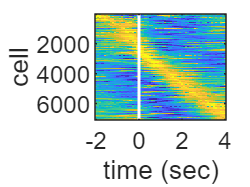

image_raw =     1.1222    0.7976    0.6841    0.2622    0.9439    0.9760    0.8776    0.8701    1.0162    0.7055    0.7614    0.3861    0.2554    0.3342    0.0697    0.3979    0.0156    0.2293   -0.1072   -0.0270    0.4632    0.2887    0.5711    0.4925   -0.2310    0.4057    0.3818    0.3776    0.4524   -0.2012   -0.0788   -1.1517   -2.2878   -2.6756   -3.1523   -2.9266   -2.5801   -2.0729   -1.1534   -1.2317   -0.5496   -0.2586    0.1430    0.1237    0.2516    0.4774    0.7850    0.6564    0.5579    0.9080
    1.1845    0.9744    0.8908    0.8890    0.5938    0.3898    0.5516    0.4698    0.5301    0.2698    0.7635    0.5977    0.8387    0.9300    1.0183    0.9548    0.8869    0.9588    0.9252    0.7746    0.3383    0.2128    0.0253    0.3050    0.3737    0.4482    0.2875   -0.0180   -0.2823   -0.4930   -1.0507   -1.2955   -1.6668   -1.7437   -2.0603   -2.1279   -2.4007   -2.0786   -1.7495   -1.7559   -1.5442   -1.3853   -1.3399   -0.7646   -0.6401   -0.4999   -0.0875    0.1202    0.3

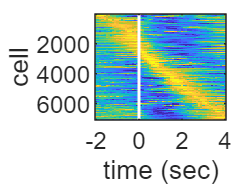

image_raw =     1.5002    1.4009    1.3394    1.3102    1.2436    1.3628    1.1464    1.4381    1.2683    1.4205    1.3259    1.4883    1.4031    1.2058    0.9549    0.9280    0.7546    0.8277    0.6158    0.6877    0.5474    0.6820    0.6530    0.6229    0.4049    0.3725    0.3172    0.1840    0.0165   -0.1257   -0.1295   -0.2126   -0.3632   -0.2693   -0.3170   -0.4930   -0.4185   -0.3072   -0.5878   -0.6806   -0.7614   -0.8939   -0.9451   -1.1059   -1.0595   -1.1447   -1.3460   -1.2294   -1.0653   -1.1063
    1.5174    1.2169    1.0681    0.8326    0.8815    0.8689    0.7125    0.5604    0.5269    0.4029    0.2897   -0.1276   -0.1263   -0.2333   -0.4674   -0.5782   -0.7104   -0.6242   -0.4207   -0.9280   -1.3164   -1.4780   -1.7126   -1.7065   -1.6280   -1.6343   -1.6133   -1.8982   -1.6334   -1.5504   -1.3700   -1.2749   -0.9257   -0.6806   -0.7713   -0.6205   -0.5171    0.0487    0.5509    0.1687    0.5348    0.4856    0.4680    0.1167   -0.0846    0.5102    0.7370    0.8952    0.9

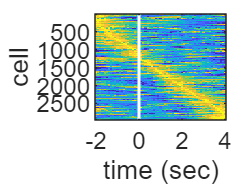

image_raw =     1.5811    1.3879    1.3469    1.3622    1.4496    1.5057    1.3476    1.3733    1.2326    1.3460    1.2045    1.2848    1.1652    1.1881    1.1923    1.1630    1.1060    0.9730    1.0403    0.8340    0.7273    0.6898    0.5608    0.3396    0.1631    0.1312    0.0163   -0.0318   -0.0705   -0.2616   -0.3896   -0.3242   -0.4817   -0.5165   -0.6011   -0.5009   -0.6254   -0.6792   -0.6469   -0.7006   -0.7245   -0.9408   -0.8949   -0.9173   -0.9684   -0.9817   -1.0959   -1.1926   -1.1626   -1.1397
    1.6312    1.1973    1.1442    1.4269    1.3548    1.3283    0.2869    0.5139    0.2327    0.6648    0.5000   -0.0015    0.2235   -0.2467    0.4956    0.7825    0.5527    0.5430    0.8323    1.3470    1.5351    1.0732    1.1699    1.1842    1.1117    0.7108    1.2207    0.7028    0.6566    0.8197    0.6133    0.3008    0.8998   -0.0212   -0.3863    0.0021   -0.4273   -0.7412   -0.6091   -1.1498   -0.7965   -1.1342   -0.8222   -1.0494   -0.7152   -0.8369   -0.6013   -0.9676   -0.6

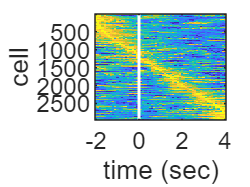

image_raw =     1.4372    1.3835    0.9013    1.0165    1.0010    1.1070    0.9170    1.0891    0.4522    0.5604    0.5188    0.5677    0.4410    0.2850    0.2882    0.5717    1.0029    0.9262    1.1119    1.2619    0.8327    1.1034    1.2803    1.3707    1.4015    1.2326    0.7401    0.8020    0.6404    0.5317    0.4257    0.0330    0.2812    0.0059    0.0079   -0.1621   -0.5292   -0.5536   -0.6215   -0.8550   -0.8313   -0.7317   -0.7879   -0.8086   -0.9875   -1.2494   -1.1725   -1.2454   -1.1116   -1.3274
    1.5449    1.4537    1.3199    1.2317    1.4995    1.4197    1.1320    0.9117    1.0130    0.9684    0.6296    0.9276    0.8408    0.8741    0.7218    0.8246    0.8883    0.8114    1.0724    0.8191    0.6490    0.7760    1.1364    0.9081    0.2774   -0.0547   -0.1162   -0.0358    0.0170   -0.2407   -0.0613   -0.2363   -0.2676   -0.5434   -0.5234   -0.6423   -0.7898   -1.0214   -0.9989   -0.8991   -1.0195   -1.0925   -1.0527   -1.1851   -1.1208   -1.4297   -1.1369   -1.4025   -1.6

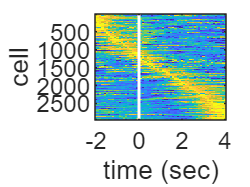

image_raw =     1.4070    0.9427    1.1948    1.1080    1.1551    0.8801    1.1247    1.3388    1.0952    1.2419    0.8538    1.1247    0.8795    0.8620    0.7165    0.3080    0.7199    0.4818    0.8788    0.8927    0.9196    1.0318    1.1921    0.8161    1.0982    0.8718    0.9460    0.8424    0.4596    0.2388    0.0784    0.0560   -0.1680   -0.1611   -0.1140   -0.3804   -0.3668   -0.6253   -1.0823   -1.4540   -1.6624   -1.5277   -1.3804   -1.3071   -1.3194   -1.3487   -1.0573   -0.9977   -1.1004   -0.8350
    1.4830    1.3914    1.4414    1.2547    1.2609    1.3615    1.1141    1.2611    1.1189    1.1033    0.9834    0.9864    0.9227    0.8104    0.6832    0.4844    0.6287    0.8048    0.7500    0.7887    0.7791    0.8062    0.5391    0.2330    0.3498    0.5558    0.6624    0.4721    0.2347    0.1286    0.3334    0.2264    0.0009    0.0201    0.1362    0.0672    0.0208   -0.0990   -0.2130   -0.2806   -0.5532   -0.7074   -0.6987   -0.8658   -0.9493   -0.9950   -0.9207   -1.1063   -1.1

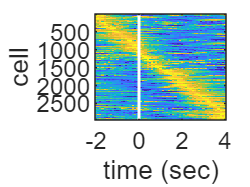

image_raw =     1.5480    1.2604    1.3473    1.3532    1.2879    1.2977    1.4135    1.5047    1.2507    1.3229    1.0745    1.2922    1.4341    0.9466    0.9687    0.7534    0.7949    0.8945    0.9117    0.9602    0.5253    0.3268    0.3031    0.1841    0.1926    0.3100   -0.0995   -0.2753   -0.6201   -0.6454   -0.4729   -0.4985   -0.4454   -0.0322   -0.2220   -0.2692   -0.2610    0.2217    0.3340    0.1867   -0.4490   -0.1938   -0.4198   -0.4899   -0.6117   -0.9513   -1.0701   -1.0777   -0.7693   -0.9879
    1.6375    1.4850    1.3898    1.5597    1.1066    1.0149    0.6273    0.3733    0.0191    0.2842    0.1046   -0.2524   -0.6971   -0.6345   -1.1215   -0.8358   -0.8133   -0.9251   -1.4310   -1.3209   -1.1015   -1.0369   -1.4303   -1.3860   -1.2583   -1.0021   -1.4045   -1.5901   -1.7141   -1.4845   -0.9626   -0.9622   -0.9580   -1.3342   -0.6660   -0.4257   -0.1012    0.0813    0.1204   -0.1641    0.7885    0.6481    0.4620    0.6812    0.5686    0.2136    0.5183    0.8895    1.0

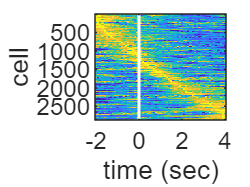

image_raw =     1.4782    1.0003    1.2964    1.1445    1.1275    1.0498    1.0588    0.6008    1.2418    0.3599   -0.1775    0.7238    0.6983    0.5135    0.8396    0.1825    0.1084    0.4331    0.4048    0.5970    0.8759    0.0594    0.5392    0.1970    1.0571    0.0849    0.4813    1.1633   -0.4162    1.3177    0.2904    0.7610    0.7336   -0.1145   -0.1787    0.6592    0.7493    0.1621    0.3267    0.6481    0.0453   -0.3945   -0.3088   -0.7770   -0.4938   -0.5508   -0.2075   -1.4698   -1.2314   -0.9393
    1.5007    1.2301    1.2314    1.4317    1.2071    1.0642    1.2820    1.2975    1.2010    0.9132    0.8856    1.0250    0.9250    0.8640    0.6422    0.6538    0.4290    0.2383    0.0862   -0.1996    0.4001    0.3069    0.7393    0.8687    1.0521    0.9843    0.7847    0.6627    0.5131    0.4253    0.4401    0.1416   -0.0247    0.0229   -0.1411    0.1502    0.1240   -0.2088   -0.1363   -0.3101   -0.5951   -0.4276   -0.7391   -0.6715   -0.4033   -0.5728   -0.7814   -0.8447   -1.0

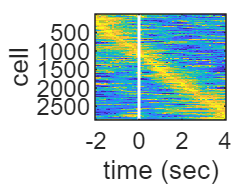

image_raw =     1.4949    1.3405    1.4711    1.3292    1.2714    1.0022    0.7240    0.9573    0.8633    0.9640    0.7402    0.8070    0.6644    0.7918    0.4666    0.4284    0.3912    0.8775    0.6349    0.2641    0.4465    0.2125    0.9076    1.2799    0.8453    0.1699   -0.1642   -0.1330   -0.1721   -0.9595   -1.2574   -1.2645   -1.5131   -2.3162   -2.2187   -2.2221   -1.7103   -1.4058   -2.0059   -1.1344   -1.1638   -0.8965   -0.4386   -0.6395   -0.2765   -0.3249    0.1541    0.0742   -0.4694   -0.0698
    1.5115    1.3960    0.7309    1.2397    0.9195    0.2834    0.8621    0.8980    1.4772    1.4735    0.9257    1.3209    0.6002    1.1453    1.1904    1.2327    0.7826   -0.0207    0.5345    0.4728    1.2164   -0.0034    0.9105    1.0248   -0.2302    0.6515    0.4042    0.6128    0.7703    0.0173   -0.3463    0.6613    0.2844    0.0618   -0.1264   -0.4309   -0.0045   -0.0829   -0.0848   -0.3369   -0.3240   -0.3725   -0.3382   -1.1198   -1.5311   -1.0047   -1.1654   -1.4065   -0.8

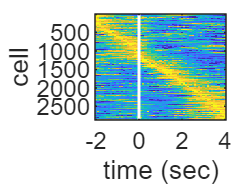

image_raw =     1.3492    1.1555    1.0841    0.9737    0.9247    1.0704    0.9346    0.8441    0.8633    0.7662    0.2726    0.7937    0.6512    0.2955    0.3848    0.5693    0.2809    0.4095    0.4612    0.2533   -0.0212   -0.0083   -0.1486   -0.2125   -0.4422   -0.6374   -0.7579   -0.9479   -0.8939   -0.8473   -1.1678   -1.1773   -1.3079   -1.2354   -1.3832   -1.3467   -1.5695   -1.5214   -1.5165   -1.7174   -1.4717   -1.2167   -1.2537   -1.1711   -1.2869   -0.9524   -0.5682   -0.3271   -0.1708    0.4486
    1.3731    1.0730    0.9136    1.2369    1.1426    1.0325    1.1416    1.2224    0.8161    1.2469    1.1572    1.2015    0.7635    0.9464    0.9221    0.4368    0.8134    0.6596    0.7674    0.9155    0.8960    0.9844    0.4573    0.1009    0.3420    0.6427    0.5852    0.4751    0.3342    0.3106    0.0751   -0.0176    0.0090   -0.0804    0.0176    0.0471    0.0105   -0.2174    0.0217   -0.0954   -0.2120   -0.3451   -0.3982   -0.4833   -0.3234   -0.7029   -0.8678   -1.0415   -1.0

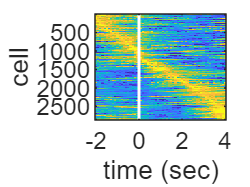

image_raw =     1.4675    1.4087    0.7247    0.4719    0.7897    0.8032    1.3875    1.1230    0.9599   -0.0261    1.3921    0.5412    0.2530    0.6565    0.5451    0.7067    1.0361    0.6770    0.4757    0.1400   -0.2085    0.4544   -1.8104   -3.7311   -2.4371   -1.0624   -0.5084   -0.6682   -1.4614   -0.9449   -0.3428    0.5696    1.1242    0.7516    0.9071    1.0049    0.8539    0.3033    0.2018    0.5370    0.1969    0.0769    0.2755    0.4678    0.1127   -0.4708   -0.5499   -0.5346   -0.8927   -1.0197
    1.5097    0.9638    1.0802    1.0153    1.3240    1.0292    0.5757    0.6109    0.5394    0.3656    0.3050    0.4084    0.1748    0.4394    0.7959    0.8272    0.9575    1.4100    1.2824    1.1154    1.2072    1.1228    0.9183    0.4265    0.5728    0.3026   -0.4442   -0.3636   -0.5873   -0.7721   -1.0732   -1.0397   -1.1859   -1.2652   -1.6585   -1.7225   -1.9566   -1.9143   -1.6757   -1.4406   -1.4941   -1.1709   -1.5390   -1.1719   -1.1264   -0.7878   -0.6537   -0.6352   -0.7

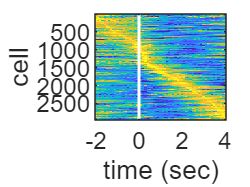

image_raw =     1.3651    1.2487    1.2050    0.9791    1.1334    1.2357    1.3435    1.0354    1.0720    0.9529    0.6937    0.7725    0.9939    0.7465    0.6913    0.7856    0.7605    0.3827    0.2921    0.0585   -0.1662    0.1830    0.4576    0.5206    0.7606    0.9476    0.8550    1.1890    1.2682    0.9830    1.0001    0.6616    0.4671    0.1740   -0.0880   -0.0826   -0.1781   -0.2937   -0.4834   -0.4888   -0.8780   -0.5426   -0.7903   -0.8088   -1.0827   -1.1088   -1.0475   -1.2789   -1.3924   -1.6704
    1.4104    0.6207    1.3223    0.1504    0.3013    0.6384    0.3003    0.5747    0.2651    0.7287    0.6845    0.7687    0.7595    0.4796    0.7890    0.0986   -0.1353    0.0731    0.9299    0.9210    0.8699    1.2227    0.8010    1.3265    0.5620    1.1436    1.0400    1.2286    1.1010    1.0976    1.3707    0.4882    0.4589   -0.0540    0.5663    0.1739    0.0206    0.3131   -0.0839   -0.9486   -0.7719   -0.6979   -0.8099   -0.6180   -0.3374   -0.6291   -0.8838   -0.9306   -0.7

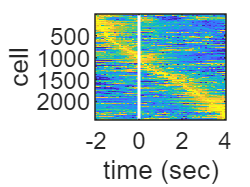

image_raw =     1.4168    1.1338    0.9131    1.0653    1.3521    1.3381    1.1380    1.2779    1.3124    1.1792    1.2432    1.2229    1.2464    0.8460    0.8022    0.7279    0.9582    0.7365    0.9917    0.9894    1.0227    0.8608    0.8909    0.4197    0.5472    0.5949    0.3140    0.5610    0.0981    0.0811   -0.0368   -0.4215   -0.3841   -0.4482   -0.3019   -0.2358    0.0348   -0.2113   -0.4953   -0.6241   -0.7321   -0.4492   -0.7156   -0.9443   -0.9534   -0.7770   -1.0135   -1.4347   -1.3541   -1.3178
    1.5338    1.4307    1.2079    1.1245    0.8547    0.9713    0.9490    1.1215    1.0394    1.2190    1.3113    1.2825    1.1248    1.0792    1.1577    1.2555    1.1049    0.9731    0.8149    1.3700    1.2458    1.1260    0.8927    0.8228    0.5708    0.2875    0.0827   -0.2001   -0.4240   -0.2897   -0.3253   -0.4041   -0.3584   -0.2177   -0.2643   -0.4453   -0.5243   -0.4931   -0.3550   -0.5391   -0.6447   -0.6872   -0.8691   -1.0944   -1.1028   -1.2977   -1.2650   -0.9749   -1.1

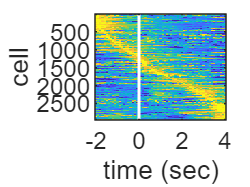

image_raw =     1.4706    1.4622    1.4702    1.0363    1.3453    1.2025    0.9650    0.5038    0.4829    0.9299   -0.1247   -0.0416    1.1871    1.0131    1.1217    1.0042    1.0863    0.3797    1.3537    0.8777    0.8666    1.2305    1.3644    0.3491   -0.2908    0.8463   -0.0453    0.1190    0.7104   -0.1921    0.4723    0.3637    0.2598    0.0972    0.4388   -0.4283   -0.3605   -0.5338    0.0265   -1.1990   -0.6289   -1.7290   -1.1804   -2.5153   -0.7929   -0.7335   -1.4823   -0.8383   -0.3132   -0.9947
    1.4875    1.3505    1.2034    1.1876    1.3433    1.0508    1.1730    0.7192    0.7065    0.2927   -0.0135    0.5793    0.9664    1.0623    0.7602    0.6838    1.3024    0.7130    0.4526   -0.2243   -0.3859    0.9686    0.7602    0.9804    0.3547    0.5599    0.5236    0.9736    0.3398    0.9387    0.4140    0.8685    0.7676   -0.2977   -0.4058    0.2950   -0.1155   -0.0435   -0.2275   -0.3798    0.0074   -0.2040   -0.5884   -0.7050   -0.8073   -0.6473   -0.9636   -0.5117   -0.7

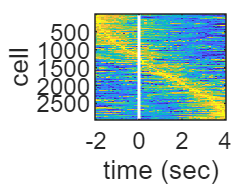

image_raw =     1.3799    1.3608    1.2435    1.0768    1.0657    1.2663    0.9862    1.0532    0.8587    0.9028    0.8240    0.7502    0.8416    0.7886    1.0227    0.9183    0.9389    0.9679    1.0364    1.1955    1.2466    1.1614    0.9612    0.9118    0.5999    0.3657    0.4212    0.4457    0.2504    0.3235    0.1507    0.0809   -0.0565   -0.1338   -0.2185   -0.2798   -0.4006   -0.3701   -0.3826   -0.5126   -0.6339   -0.6608   -0.7257   -0.6811   -0.8968   -1.0640   -1.0754   -1.1199   -1.2305   -1.1518
    1.4655    1.4293    1.3127    1.2250    1.2467    1.1463    1.0817    1.1358    0.9109    0.8232    0.7915    0.9142    0.9959    0.9202    0.9531    1.0437    1.0366    1.2096    1.1909    1.1479    1.1455    0.8533    0.6326    0.5567    0.1620    0.2855    0.0136   -0.2427   -0.4252   -0.4860   -0.5611   -0.7056   -0.7114   -0.9636   -0.7768   -0.8030   -1.1365   -1.1840   -1.2336   -1.1739   -1.2105   -1.1439   -1.3772   -1.1435   -1.3788   -1.3636   -1.5548   -1.5581   -1.3

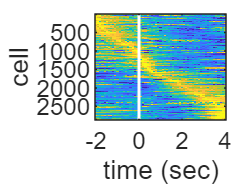

image_raw =     1.4968    1.4547    1.2950    1.3581    1.0795    0.9214    1.0687    0.7603    0.3840    0.2141    0.0331   -0.1171   -0.6028   -0.9381   -1.0059   -1.4578   -1.3411   -1.4442   -1.6451   -1.3569   -1.4436   -1.7709   -1.7208   -1.3536   -0.7309    0.0118    0.0048    0.2320    1.1465    0.9896    0.8929    0.5795    0.8923    0.5652    0.1982    0.6933    0.4691    0.4854    0.4959   -0.0773    0.2516    0.3540    0.4505    0.5988    1.2445    1.0721    0.9814    1.0521    1.0909    1.2060
    1.5053    1.3021    1.0923    0.9736    0.9353    0.7647    0.7433    0.4718    0.4183    0.3761    0.5588    0.4131    0.7982    0.5474    0.7915    1.0298    0.9831    0.4481    0.5023    0.2868    0.3304    0.5830    0.6017    0.9704    0.9048    0.9085    0.8451    0.7742    0.4236    0.6018    0.6033    0.3460    0.8007    0.8691    0.6419    0.5444    0.2517    0.1452    0.1231   -0.0963   -0.3545   -0.3244   -0.5873   -0.5318   -0.7092   -0.6704   -0.8398   -0.9325   -1.4

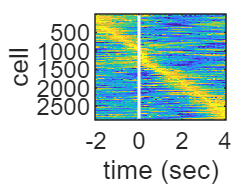

image_raw =     1.4317    1.3115    1.4198    1.2765    1.1157    1.2078    1.2199    1.3594    1.3702    1.0984    1.2456    1.0015    0.7970    0.8963    0.6658    0.7121    0.7210    0.6567    0.5865    0.5192    0.6696    0.4911    1.0337    0.8462    0.6731    0.4381    0.5634    0.3659    0.4882    0.2520    0.2316    0.0787    0.1271    0.0550   -0.0882   -0.2210   -0.2082   -0.3468   -0.4867   -0.6225   -0.7833   -0.5694   -0.8572   -0.9681   -0.8507   -0.7668   -1.1082   -1.0043   -0.8989   -1.1788
    1.5395    1.4816    1.4927    1.4701    1.3677    1.3573    1.3278    1.1732    1.1626    1.0033    1.0557    1.1212    1.0429    0.9979    0.9983    0.9489    0.9903    0.9085    0.8311    0.8544    0.7674    0.6421    0.6161    0.5168    0.4380    0.3723    0.2885    0.3059    0.1288    0.0601   -0.0154    0.0131   -0.1325   -0.1681   -0.2481   -0.3929   -0.3815   -0.4677   -0.6649   -0.6378   -0.6858   -0.8778   -0.8717   -0.9289   -1.1375   -1.2301   -1.2257   -1.3195   -1.3

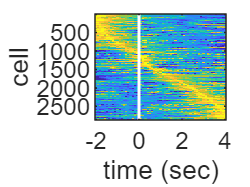

image_raw =     1.3446    1.2613    1.2184    1.3326    1.2475    1.2896    1.0386    1.1705    1.1514    1.2198    1.0673    0.7442    0.9528    0.9286    0.7541    0.8609    0.8312    0.4131    0.8595    0.7371    0.5195    0.5350    0.2350    0.5377    0.7836    1.0377    0.7021    0.9701    0.5521    0.4138    0.1308    0.1673    0.0046   -0.5771   -0.2939   -0.3762   -0.1909   -0.4238   -0.5118   -0.5983   -0.4697   -0.4959   -0.5762   -0.5351   -0.5630   -1.0374   -0.8339   -0.9525   -0.8965   -0.9797
    1.4282    1.0974    1.1422    0.8592    1.0367    0.6083    0.4908    0.5698    0.5566    0.2246    0.0165   -0.0291   -0.1194   -0.2744   -0.6358   -0.4852   -0.8423   -1.2181   -1.6868   -2.1536   -1.6510   -2.9219   -2.6576   -2.4448   -1.8483   -1.3537   -0.0204   -0.4922   -0.3460    0.0655   -0.4078    0.6531    0.3219    0.6092    0.8294    0.1280    0.1831    0.9664    0.8737    0.4284    0.9682    0.3782    0.7278    0.9403    0.9365    0.7964    1.2995    0.9013    0.1

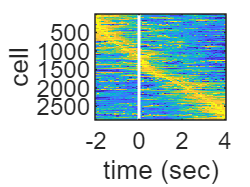

% plot neural activity heatmap
title_list = {'Reward', 'Reward miss', 'push_trial_push_prob_block', 'push_trial_pull_prob_block', 'pull_trial_push_prob_block', 'pull_trial_pull_prob_block',...
    'push_trial_push_value_block','push_trial_pull_value_block','pull_trial_push_value_block','pull_trial_pull_value_block',...
    'push_trial_push_prob_block','push_trial_pull_prob_block','pull_trial_push_prob_block','pull_trial_pull_prob_block',...
    'push_trial_push_value_block','push_trial_pull_value_block','pull_trial_push_value_block','pull_trial_pull_value_block'};
if norm == 1
    climit = [0 1];
elseif norm == 2 || norm == 3 || norm == 4 || norm == 5
    climit = [-2 2];
else
    climit = [0 20]; %[0 50];
end

for i = 1:length(eta_acts_conc)
    figure
    set(gcf,'color','w');
    % for i = 1:length(brain_roi) 
    %     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
        clims = climit;
        image_raw = eta_acts_conc{i} %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        rows_to_remove = any(isnan(image_raw), 2);
        image = image_raw(~rows_to_remove,:);
        imagesc(-before_event:0.1:after_event,1:size(image,1),image,clims);
        ylabel('cell');
        xlabel('time (sec)')
    % end
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
    hold off;    
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_' title_list{i} '_eta_activity_heatmap.png'];
    filename = [output_dir  '_' title_list{i} '_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;
end

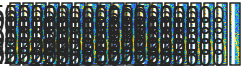

figure('Position', [100, 100, 4800, 600]);
set(gcf,'color','w');

for i = 1:length(eta_acts_conc) 
    subaxis(1,length(eta_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
    clims = climit;
    image_raw = eta_acts_conc{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
    rows_to_remove = any(isnan(image_raw), 2);
    image = image_raw(~rows_to_remove,:);
    imagesc(-before_event:0.1:after_event,1:size(image,1),image,clims);    
%         ylabel('cell');
    xlabel('time (sec)');
    if i == 1
        ylabel('cell');
    end
    title(title_list{i});
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
    hold off;    
end
%     xlabel('time (sec)');

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' strrep(strjoin(title_list),' ','_') '_eta_activity_heatmap.png'];
filename = [output_dir 'all_conditions_eta_activity_heatmap.png'];
saveas(gcf,filename);

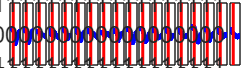


figure('Position', [100, 100, 4800, 600]);
for i = 1:length(eta_acts_conc)
    subaxis(1,length(eta_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
    % NaNを含む行を削除
    data = eta_acts_conc{i};
    data = data(~any(isnan(data), 2), :);
    z = zscore(data, 0, 1); % 列方向に Zスコアを計算
    data = data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

    mean_values = mean(data, 1);
    std_values = std(data, 0, 1);
    x = -before_event:0.1:after_event;
  
    % fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
    hold on;
    plot(x, mean_values, 'b', 'LineWidth', 1.5); 
    % xlim = [-2,4]
    % x=0に赤い縦線をプロット       
    % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    if norm ~= 0
        plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
    else
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
    end
    hold off;
    if i == 1;
        ylabel('normalized activity');
    end
    xlabel('time (sec)');
    title(title_list{i});        
     axis tight;
    if norm ~= 0 & norm ~= 6
        ylim([-1 1]);  
    elseif norm == 6
        ylim([-1 6]); %ylim([-1 2]);
    end
end
    
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_eta_activity.png'];
filename = [output_dir 'all_conditions_eta_activity.png'];
saveas(gcf,filename);

% figure('Position', [100, 100, 1000, 600]);
% num_plots = length(eta_acts_conc) / 2;  % 2つずつ重ねるので実プロット数は半分
% 
% for i = 1:num_plots
%     subaxis(1, num_plots, i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.08);
%     hold on;
%     x = -before_event:0.1:after_event;
% 
%     for j = 0:1  % j=0→奇数番目, j=1→偶数番目
%         idx = (i - 1) * 2 + j + 1;
%         data = eta_acts_conc{idx};
%         data = data(~any(isnan(data), 2), :);
%         z = zscore(data, 0, 1); % 列方向に Zスコアを計算
%         data = data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去
%         mean_values = mean(data, 1);
% 
%         % 破線か実線か（偶数番号は破線）
%         if mod(idx, 2) == 0
%             color = [0.5 0.5 0.5];
%         else
%             color = 'k';
%         end
% 
%         % 白黒プロット（グレーにしたければ [0.5 0.5 0.5] などでも可）
%         plot(x, mean_values, 'Color', color, 'LineStyle', '-', 'LineWidth', 3);
%     end
% 
%     % x=0 に赤い縦線
%     if norm ~= 0
%         plot([0 0], [-100, 100], 'k--', 'LineWidth', 2);      
%     else
%         yLimits = get(gca, 'YLim');
%         plot([0 0], yLimits, 'k--', 'LineWidth', 2);
%     end
% 
%     % 軸やラベル
%     if i == 1
%         ylabel('normalized activity');
%     end
%     xlabel('time (sec)');
%     title([title_list{(i-1)*2+1} ' + ' title_list{(i-1)*2+2}]);
% 
%     axis tight;
%     if norm ~= 0 && norm ~= 6
%         ylim([-1 1]);  
%     elseif norm == 6
%         ylim([-1 3]);
%     end
%     hold off;
% end
% 
% % 保存
% filename = [output_dir strrep(strjoin(title_list),' ','_') '_eta_activity_DC.png'];
% saveas(gcf, filename);


% write eta code by categrizing neurons by layers
if categorize == 'layer' 
    eta_layer23_acts_conc = cell(1, length(eta_acts));
    eta_layer5_acts_conc = cell(1, length(eta_acts));
    for i = 1:length(eta_acts)
        % % align concatenated eta neural activities
        % [M,eta_i] = max(eta_acts_conc{i},[],2);
        % if norm==3
        %     eta_acts_conc{i} = cat(2, eta_i,pointAreas_conc(find(sig_cell_idxs2_conc{i} == 1)) ,eta_acts_conc{i});
        % else
        %     eta_acts_conc{i} = cat(2, eta_i,pointAreas_conc ,eta_acts_conc{i});
        % end        
        % eta_acts_conc{i} =   sortrows(eta_acts_conc{i});
        % eta_acts_max_act_times_conc{i} = eta_acts_conc{i}(:,1)/10 -2;
        % etaAreas = eta_acts_conc{i}(:,2);
        % eta_acts_conc{i}(:,1:2) = [];
        % specify layer specific activity
        eta_layer23_acts_conc{i} = eta_acts_conc{i}(find(sortedAreas_conc{i} == 1),:);
        eta_layer5_acts_conc{i}  = eta_acts_conc{i}(find(sortedAreas_conc{i} == 0),:);        
        % eta_layer23_acts_conc{i} = eta_acts_conc{i}(find(etaAreas == 1),:);
        % eta_layer5_acts_conc{i}  = eta_acts_conc{i}(find(etaAreas == 0),:);
    end
end

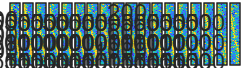

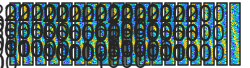

% plot layer specific eta by multiple plane figure
if categorize == 'layer'
    figure('Position', [100, 100, 4800, 600])
    set(gcf,'color','w');
    for i = 1:length(eta_layer23_acts_conc) 
        subaxis(1,length(eta_layer23_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
        clims = climit;      
        image_raw = eta_layer23_acts_conc{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        rows_to_remove = any(isnan(image_raw), 2);
        image = image_raw(~rows_to_remove,:);
        imagesc(-before_event:0.1:after_event,1:size(image,1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     xlabel('time (sec)');
   
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' strrep(strjoin(title_list),' ','_') '_layer23_eta_activity_heatmap.png'];
    filename = [output_dir 'all_conditions_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
    
    figure('Position', [100, 100, 4800, 600])
    set(gcf,'color','w');
    for i = 1:length(eta_layer5_acts_conc) 
        subaxis(1,length(eta_layer5_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
        clims = climit;
        image_raw = eta_layer5_acts_conc{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        rows_to_remove = any(isnan(image_raw), 2);
        image = image_raw(~rows_to_remove,:);
        imagesc(-before_event:0.1:after_event,1:size(image,1),image,clims);        
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     ylabel('cell');
    filename = [output_dir  'all_conditions_layer5_eta_activity_heatmap.png'];
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' strrep(strjoin(title_list),' ','_')  '_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
end

% % plot pie graph
% if norm ==3
%     high_low_reward_idx = sig_cell_idxs2_sessions{1}{5} & sig_cell_idxs2_sessions{1}{6};
%     high_reward_idx     = sig_cell_idxs2_sessions{1}{5} & ~sig_cell_idxs2_sessions{1}{6};
%     low_reward_idx      = ~sig_cell_idxs2_sessions{1}{5} & sig_cell_idxs2_sessions{1}{6};
%     neither_idx         = ~sig_cell_idxs2_sessions{1}{5} & ~sig_cell_idxs2_sessions{1}{6}; 
%     for i_animal = 2:length(Animal)
%         high_low_reward_idx = [high_low_reward_idx, sig_cell_idxs2_sessions{i_animal}{5} & sig_cell_idxs2_sessions{i_animal}{6}];
%         high_reward_idx     = [high_reward_idx, sig_cell_idxs2_sessions{i_animal}{5} & ~sig_cell_idxs2_sessions{i_animal}{6}];
%         low_reward_idx      = [low_reward_idx, ~sig_cell_idxs2_sessions{i_animal}{5} & sig_cell_idxs2_sessions{i_animal}{6}];
%         neither_idx         = [neither_idx, ~sig_cell_idxs2_sessions{i_animal}{5} & ~sig_cell_idxs2_sessions{i_animal}{6}]; 
%     end
% 
%     data = [sum(high_low_reward_idx) sum(high_reward_idx) sum(low_reward_idx) sum(neither_idx)]
%     labels = {'high and low reward','high reward','low reward', 'neither'};
%     figure
%     % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
%     p = pie(data); %, labels);
%     % title({'Percentage of neurons that reflect value among the neurons ', 'that fire when force is applied. (n=143)'});
%     pText = findobj(p,'Type','text');
%     percentValues = get(pText,'String');
%     txt = {['(' num2str(data(1)) ')']; ['(' num2str(data(2)) ')']; ['(' num2str(data(3)) ')']; ['(' num2str(data(4)) ')']};
%     combinedtxt = strcat(percentValues,txt);
%     pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
%     pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
%     legend(labels,'Location','southoutside'); 
% 
%     filename = [output_dir  strrep(strjoin(title_list),' ','_'), '_' categorize '_action_value_cells_pie.png'];
%     % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' strrep(strjoin(title_list),' ','_'), '_' categorize '_action_value_cells_pie.png'];
%     saveas(gcf,filename);
% end

% if norm == 3 & strcmp(categorize, 'layer')
%     pointAreas_session = pointAreas_all_sessions{1};
%     pointAreas_logical = logical(pointAreas_session');
%     high_low_reward_layer23_idx = sig_cell_idxs2_sessions{1}{5} & sig_cell_idxs2_sessions{1}{6} & pointAreas_logical;
%     high_reward_layer23_idx     = sig_cell_idxs2_sessions{1}{5} & ~sig_cell_idxs2_sessions{1}{6} & pointAreas_logical;
%     low_reward_layer23_idx      = ~sig_cell_idxs2_sessions{1}{5} & sig_cell_idxs2_sessions{1}{6} & pointAreas_logical;
%     neither_layer23_idx         = ~sig_cell_idxs2_sessions{1}{5} & ~sig_cell_idxs2_sessions{1}{6} & pointAreas_logical;   
%     high_low_reward_layer5_idx = sig_cell_idxs2_sessions{1}{5} & sig_cell_idxs2_sessions{1}{6} & ~pointAreas_logical;
%     high_reward_layer5_idx     = sig_cell_idxs2_sessions{1}{5} & ~sig_cell_idxs2_sessions{1}{6} & ~pointAreas_logical;
%     low_reward_layer5_idx      = ~sig_cell_idxs2_sessions{1}{5} & sig_cell_idxs2_sessions{1}{6} & ~pointAreas_logical;
%     neither_layer5_idx         = ~sig_cell_idxs2_sessions{1}{5} & ~sig_cell_idxs2_sessions{1}{6} & ~pointAreas_logical;
%     for i_animal = 2:length(Animal)  
%         pointAreas_session = pointAreas_all_sessions{i_animal};
%         pointAreas_logical = logical(pointAreas_session');        
%         high_low_reward_layer23_idx = [high_low_reward_layer23_idx, sig_cell_idxs2_sessions{i_animal}{5} & sig_cell_idxs2_sessions{i_animal}{6} & pointAreas_logical];
%         high_reward_layer23_idx     = [high_reward_layer23_idx, sig_cell_idxs2_sessions{i_animal}{5} & ~sig_cell_idxs2_sessions{i_animal}{6} & pointAreas_logical];
%         low_reward_layer23_idx      = [low_reward_layer23_idx, ~sig_cell_idxs2_sessions{i_animal}{5} & sig_cell_idxs2_sessions{i_animal}{6} & pointAreas_logical];
%         neither_layer23_idx         = [neither_layer23_idx, ~sig_cell_idxs2_sessions{i_animal}{5} & ~sig_cell_idxs2_sessions{i_animal}{6} & pointAreas_logical];   
%         high_low_reward_layer5_idx = [high_low_reward_layer5_idx, sig_cell_idxs2_sessions{i_animal}{5} & sig_cell_idxs2_sessions{i_animal}{6} & ~pointAreas_logical];
%         high_reward_layer5_idx     = [high_reward_layer5_idx, sig_cell_idxs2_sessions{i_animal}{5} & ~sig_cell_idxs2_sessions{i_animal}{6} & ~pointAreas_logical];
%         low_reward_layer5_idx      = [low_reward_layer5_idx, ~sig_cell_idxs2_sessions{i_animal}{5} & sig_cell_idxs2_sessions{i_animal}{6} & ~pointAreas_logical];
%         neither_layer5_idx         = [neither_layer5_idx, ~sig_cell_idxs2_sessions{i_animal}{5} & ~sig_cell_idxs2_sessions{i_animal}{6} & ~pointAreas_logical]; 
%     end
% 
%     data_layer23 = [sum(high_low_reward_layer23_idx) sum(high_reward_layer23_idx) sum(low_reward_layer23_idx) sum(neither_layer23_idx)];
%     data_layer5 = [sum(high_low_reward_layer5_idx) sum(high_reward_layer5_idx) sum(low_reward_layer5_idx) sum(neither_layer5_idx)];
%     labels = {'high and low reward','high reward','low reward', 'neither'};
% 
%     figure
% 
%     % Layer 23 の円グラフを左側にプロット
%     subplot(1, 2, 1);  % 1行2列のグラフのうち、左側にプロット
%     p23 = pie(data_layer23); 
%     pText23 = findobj(p23, 'Type', 'text');
%     percentValues23 = get(pText23, 'String');
%     txt23 = {['(' num2str(data_layer23(1)) ')']; ['(' num2str(data_layer23(2)) ')']; ['(' num2str(data_layer23(3)) ')']; ['(' num2str(data_layer23(4)) ')']};
%     combinedtxt23 = strcat(percentValues23, txt23);
%     for i = 1:length(pText23)
%         pText23(i).String = combinedtxt23{i}; 
%     end
%     title('Layer 23');
%     legend(labels, 'Location', 'southoutside');
% 
%     % Layer 5 の円グラフを右側にプロット
%     subplot(1, 2, 2);  % 1行2列のグラフのうち、右側にプロット
%     p5 = pie(data_layer5); 
%     pText5 = findobj(p5, 'Type', 'text');
%     percentValues5 = get(pText5, 'String');
%     txt5 = {['(' num2str(data_layer5(1)) ')']; ['(' num2str(data_layer5(2)) ')']; ['(' num2str(data_layer5(3)) ')']; ['(' num2str(data_layer5(4)) ')']};
%     combinedtxt5 = strcat(percentValues5, txt5);
%     for i = 1:length(pText5)
%         pText5(i).String = combinedtxt5{i}; 
%     end
%     title('Layer 5');
%     legend(labels, 'Location', 'southoutside');
% 
%     % 保存
%     filename = [output_dir strrep(strjoin(title_list),' ','_'), '_' categorize '_action_value_cells_layer_pie.png'];    
%     % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_action_value_cells_layer_pie.png'];
%     saveas(gcf, filename);
% end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
    % pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    % pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
if strcmp(categorize, 'layer') == 1
    % title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    % figure('Position', [100, 100, 2400, 600]);
    % set(gcf,'color','w');
    % for i = 1:length(AlinmentTimingCells)
    %     subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
    %     clims = climit;
    %     image = pull_act_layer23_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
    %     % NaNを含む行を削除
    %     image = image(~any(isnan(image), 2), :);
    %     imagesc(-before_event:0.1:after_event,1:size(pull_act_layer23_cells{i},1),image,clims);
    %     if i == 1
    %         ylabel('cell');
    %     end
    %     xlabel('time (sec)');
    %     title(title_list{i});
    %     % x=0 に白い縦線を描画
    %     hold on; % プロットを追加するために hold on を使用
    %     yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    %     plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
    %     hold off;           
    % end
    % 
    % % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer23_eta_activity_heatmap.png'];
    % filename = [output_dir 'pull_layer23_eta_activity_heatmap.png'];
    % saveas(gcf,filename);
    % % close all;
    % 
    figure('Position', [100, 100, 4800, 600]);
    for i = 1:length(eta_layer23_acts_conc)
        subaxis(1,length(eta_layer23_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
        % NaNを含む行を削除
        data = eta_layer23_acts_conc{i};
        data = data(~any(isnan(data), 2), :);
        z = zscore(data, 0, 1); % 列方向に Zスコアを計算
        data = data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);      
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end      
        hold off;
        axis tight;  
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});

    end

    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer23_eta_activity.png'];
    filename = [output_dir  'layer23_eta_activity_conc.png'];
    saveas(gcf,filename);
    % close all;
    % 
    % figure('Position', [100, 100, 2400, 600]);
    % set(gcf,'color','w');
    % for i = 1:length(AlinmentTimingCells)
    %     subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
    %     clims = climit;
    %     image = pull_act_layer5_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
    %     % NaNを含む行を削除
    %     image = image(~any(isnan(image), 2), :);        
    %     imagesc(-before_event:0.1:after_event,1:size(pull_act_layer5_cells{i},1),image,clims);
    %     % x=0 に白い縦線を描画
    %     hold on; % プロットを追加するために hold on を使用
    %     yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    %     plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
    %     hold off;          
    %     if i == 1
    %         ylabel('cell');
    %     end
    %     xlabel('time (sec)');
    %     title(title_list{i});
    % end
    % 
    % % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer5_eta_activity_heatmap.png'];
    % filename = [output_dir 'pull_layer5_eta_activity_heatmap.png'];
    % saveas(gcf,filename);
    % % close all;

    figure('Position', [100, 100, 4800, 600]);
    for i = 1:length(eta_layer5_acts_conc)
        subaxis(1,length(eta_layer5_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
        % NaNを含む行を削除
        data = eta_layer5_acts_conc{i};
        data = data(~any(isnan(data), 2), :);
        z = zscore(data, 0, 1); % 列方向に Zスコアを計算
        data = data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);              
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end       
        hold off;
        axis tight;          
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end     
        if i == 1
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer5_eta_activity.png'];
    filename = [output_dir 'layer5_eta_activity_conc.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 4800, 600]);
    for i = 1:length(eta_layer23_acts_conc)
        subaxis(1,length(eta_layer23_acts_conc),i, 'Spacing', 0.01, 'Padding', 0, 'Margin', 0.04);
        % NaNを含む行を削除
        data23 = eta_layer23_acts_conc{i};
        data23 = data23(~any(isnan(data23), 2), :);
        data5 = eta_layer5_acts_conc{i};
        data5 = data5(~any(isnan(data5), 2), :);        
        z23 = zscore(data23, 0, 1); z5 = zscore(data5, 0, 1); % 列方向に Zスコアを計算
        data23 = data23(max(abs(z23), [], 2) < 10, :);data5 = data5(max(abs(z5), [], 2) < 10, :); % Zスコアが100以上の行を除去

        % mean_values = mean(data, 1);
        % std_values = std(data, 0, 1);              
        mean_values23 = mean(data23, 1);
        std_values23 = std(data23, 0, 1);        
        mean_values5 = mean(data5, 1);
        std_values5 = std(data5, 0, 1);
        x = -before_event:0.1:after_event;

        hold on;        
        fill([x, fliplr(x)], [mean_values23 + std_values23, fliplr(mean_values23 - std_values23)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values23, 'g', 'LineWidth', 1.5); 
        fill([x, fliplr(x)], [mean_values5 + std_values5, fliplr(mean_values5 - std_values5)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values5, 'b', 'LineWidth', 1.5);         
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end        
        hold off;
        axis tight;  
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 6]); %ylim([-1 2]);
        end      
        if i == 1
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer235_eta_activity.png'];
    filename = [output_dir 'pull_layer235_eta_activity.png'];
    saveas(gcf,filename);
    close all;
end

% 階層的クラスタリングの実施

% 1. すべての要素が NaN であるセルを特定して除外
% cellfun を使用して、各行列の全要素が NaN かどうかを判定します
is_all_nan = cellfun(@(x) all(isnan(x(:))), eta_acts_conc);
is_all_nan(1) = 1; is_all_nan(2) = 1;%temporaly
filtered_eta_acts = eta_acts_conc(~is_all_nan);

if isempty(filtered_eta_acts)
    error('有効な ETA データがありません。すべてのデータが NaN です。');
end

fprintf('除外された NaN イベント数: %d / %d\n', sum(is_all_nan), length(eta_acts_conc));

除外された NaN イベント数: 2 / 18


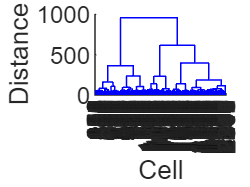


% 2. 有効なデータのみを横方向に結合
try
    data_all = horzcat(filtered_eta_acts{:});
catch
    error('有効なデータ間で細胞数（行数）が一致していないため、横方向に結合できません。');
end

% 3. 特定の行（細胞）に一部でも NaN が含まれる場合はその行を削除
% (例：特定の細胞だけ解析期間外だった場合など)
nan_rows = any(isnan(data_all), 2); 
data = data_all(~nan_rows, :);

% メタデータ (pointAreas) のフィルタリング
if iscell(pointAreas_conc)
    pointAreas_combined = vertcat(pointAreas_conc{:}); % セルなら結合
else
    pointAreas_combined = pointAreas_conc; % 行列ならそのまま
end
pointAreas_filtered = pointAreas_combined(~nan_rows, :);
% 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
linkage_matrix = linkage(data, 'ward');

% 樹形図の作成
figure('Position', [100, 100, 800, 600]);
[H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
% title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
xlabel('Cell');
ylabel('Distance');
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_hierarchical_clustering_dendrogram.png'];
filename = [output_dir 'hierarchical_clustering_dendrogram_eta_conc.png'];
saveas(gcf,filename);    

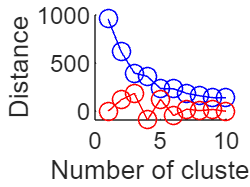


% 順序付けされたdata
ordered_data = data(outperm, :);

% エルボー法のためのプロット作成
figure('Position', [100, 100, 800, 600]);
last = linkage_matrix(end-9:end, 3);
last_rev = flipud(last);
indexes = 1:length(last);
hold on
plot(indexes, last_rev, 'b-o');
acceleration = diff(last, 2);  % 2次の微分を計算
acceleration_rev = zeros(10,1);
acceleration_rev(2:end-1) = flipud(acceleration);
plot(indexes, acceleration_rev, 'r-o');
hold off
xlabel('Number of clusters');
ylabel('Distance');
% title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_elbow.png'];
filename = [output_dir 'elbow_eta_conc.png'];
saveas(gcf,filename);     

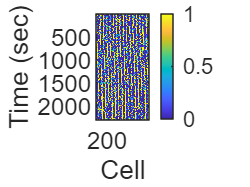


% 相関行列の表示
figure('Position', [100, 100, 800, 600]);
imagesc(ordered_data, [0 1]);
colorbar;
% title(title_list{i});  %title('Correlation Matrix');
xlabel('Cell');
ylabel('Time (sec)');
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_eta_heatmap2.png'];
filename = [output_dir 'eta_heatmap2_conc.png'];
saveas(gcf,filename);         

    % colormap('viridis');
% end

% plot clustered ETA neural activity
num_clusters = 6; % クラスター数を指定（必要に応じて変更）

title_list = {'Reward', 'Reward miss', 'push_trial_push_prob_block_pull', 'push_trial_pull_prob_block_pull', 'pull_trial_push_prob_block_pull', 'pull_trial_pull_prob_block_pull',...
    'push_trial_push_value_block_pull','push_trial_pull_value_block_pull','pull_trial_push_value_block_pull','pull_trial_pull_value_block_pull',...
    'push_trial_push_prob_block_push','push_trial_pull_prob_block_push','pull_trial_push_prob_block_push','pull_trial_pull_prob_block_push',...
    'push_trial_push_value_block_push','push_trial_pull_value_block_push','pull_trial_push_value_block_push','pull_trial_pull_value_block_push'};
% title_list = {'Reward', 'Reward miss', 'Force usual resistance', 'Force rare resistance', 'Force high reward', 'Force low reward'};

% 1. 全てNaNの要素を除外したリストの作成（クラスタリング時と同じ論理インデックスを使用）
is_all_nan = cellfun(@(x) all(isnan(x(:))), eta_acts_conc);
is_all_nan(1) = 1; is_all_nan(2) = 1; %temporaly
valid_eta_acts = eta_acts_conc(~is_all_nan);
valid_titles = title_list(~is_all_nan);
num_valid_events = length(valid_eta_acts);

% --- 階層的クラスタリングの実行 ---
cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
all_cluster_labels = cluster_labels;
unique_elements = unique(cluster_labels);
counts = histc(cluster_labels, unique_elements);

for n = 1:length(unique_elements)
    fprintf('Cluster %d: %d cells\n', unique_elements(n), counts(n));
end

Cluster 1: 259 cells
Cluster 2: 218 cells
Cluster 3: 429 cells
Cluster 4: 327 cells
Cluster 5: 645 cells
Cluster 6: 433 cells


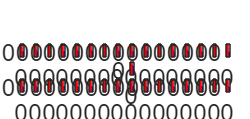


% --- プロットの実行 ---
% 横方向にイベント（有効なもののみ）、縦方向にクラスタを配置
fig_width = 400 * num_valid_events; % イベント数に応じて横幅を調整
fig_height = 300 * num_clusters;    % クラスタ数に応じて縦幅を調整
figure('Position', [100, 100, min(fig_width, 2500), min(fig_height, 1200)], 'Color', 'w');

for i = 1:num_valid_events
    i_data = valid_eta_acts{i}; % 有効なデータセットを選択
    
    for cluster_num = 1:num_clusters   
        % サブプロットのインデックス計算: (行, 列, 現在の場所)
        % 有効なイベント数 (num_valid_events) に基づいて配置
        subaxis(num_clusters, num_valid_events, i + num_valid_events*(cluster_num-1), ...
            'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        
        % 現在のクラスタに属する細胞のデータを抽出
        % ※ cluster_labels は全細胞に対するもの。横方向結合データからNaN行を除去した後の順序と一致している必要があります
        cluster_data = i_data(cluster_labels == cluster_num, :);
        
        % 行内（トライアル平均波形）にNaNが含まれる場合は除去
        cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);
        
        if isempty(cluster_data)
            axis off; continue;
        end

        % 外れ値除去 (Z-score 10以上を除去)
        if size(cluster_data, 1) > 1
            z = zscore(cluster_data, 0, 1);
            cluster_data = cluster_data(max(abs(z), [], 2) < 10, :);
        end

        % 統計値の計算
        mean_values = mean(cluster_data, 1);
        std_values = std(cluster_data, 0, 1);
        x = -before_event:0.1:after_event;
      
        % 平均 ± 標準偏差 の塗りつぶし
        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], ...
             'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.2); 
        
        % イベント発生時刻 (x=0) の縦線
        if norm ~= 0
            plot([0 0], [-100, 100], 'r-', 'LineWidth', 1);     
        else
            yLimits = ylim;
            plot([0 0], yLimits, 'r-', 'LineWidth', 1);
        end
        hold off;

        % 軸ラベル・タイトルの設定
        if i == 1
            ylabel(sprintf('Cluster %d\n(z-score)', cluster_num), 'FontWeight', 'bold');
        end
        if cluster_num == num_clusters
            xlabel('time (sec)');
        end
        if cluster_num == 1
            % 有効なタイトルのみを反映
            title(valid_titles{i}, 'Interpreter', 'none', 'FontSize', 9);
        end
        
        % 表示範囲の固定
        axis tight;
        if norm ~= 0 && norm ~= 6
            ylim([-1.5 2.5]); % z-scoreの場合の標準的な範囲
        elseif norm == 6
            ylim([-6 24]);
        end
        grid on;
    end
end

% 保存
filename = [output_dir 'clustered_eta_valid_events_only.png'];
saveas(gcf, filename);

fprintf('Plot saved: %s\n', filename);

Plot saved: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\C6J501_C6J506_tph578_norm2/clustered_eta_valid_events_only.png


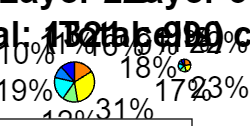

% --- クラスター分布の層別 Pie チャート作成 ---

% cluster_labels: フィルタリング後の各細胞のクラスター番号 (1 ~ num_clusters)
% pointAreas_filtered: フィルタリング後の各細胞の所属層 (1: L2/3, 0: L5)

unique_clusters = 1:num_clusters;
cluster_colors = jet(num_clusters); % クラスター間で共通の色を使用

figure('Name', 'Cluster Distribution by Layer', 'Position', [100, 100, 1100, 550], 'Color', 'w');

% --- 1. Layer 2/3 の解析とプロット ---
subplot(1, 2, 1);
idx_l23 = (pointAreas_filtered == 1);
if any(idx_l23)
    l23_clusters = cluster_labels(idx_l23);
    % 各クラスターの度数を集計
    counts_l23 = histcounts(l23_clusters, 1:num_clusters+1);
    
    % 円グラフの描画
    p_l23 = pie(counts_l23);
    
    % ラベルと色の設定
    % pie 関数は [patch, text, patch, text...] の順でオブジェクトを返す
    patch_idx = 1;
    for k = 1:length(p_l23)
        if isa(p_l23(k), 'matlab.graphics.primitive.Patch')
            p_l23(k).FaceColor = cluster_colors(patch_idx, :);
            patch_idx = patch_idx + 1;
        end
    end
    title(sprintf('Layer 2/3\n(Total: %d cells)', sum(idx_l23)), 'FontSize', 12);
else
    text(0.5, 0.5, 'No L2/3 cells', 'HorizontalAlignment', 'center');
end

% --- 2. Layer 5 の解析とプロット ---
subplot(1, 2, 2);
idx_l5 = (pointAreas_filtered == 0);
if any(idx_l5)
    l5_clusters = cluster_labels(idx_l5);
    % 各クラスターの度数を集計
    counts_l5 = histcounts(l5_clusters, 1:num_clusters+1);
    
    % 円グラフの描画
    p_l5 = pie(counts_l5);
    
    % 色の設定
    patch_idx = 1;
    for k = 1:length(p_l5)
        if isa(p_l5(k), 'matlab.graphics.primitive.Patch')
            p_l5(k).FaceColor = cluster_colors(patch_idx, :);
            patch_idx = patch_idx + 1;
        end
    end
    title(sprintf('Layer 5\n(Total: %d cells)', sum(idx_l5)), 'FontSize', 12);
else
    text(0.5, 0.5, 'No L5 cells', 'HorizontalAlignment', 'center');
end

% --- 3. 共通の凡例と保存 ---
legend_labels = arrayfun(@(x) sprintf('Cluster %d', x), unique_clusters, 'UniformOutput', false);
lgd = legend(legend_labels, 'Location', 'southoutside', 'Orientation', 'horizontal');
% sgtitle(['Cell Cluster Ratio by Cortical Layer: ' Animal]);

filename_pie = [output_dir 'cluster_distribution_pie_by_layer.png'];
saveas(gcf, filename_pie);

fprintf('Pie charts saved: %s\n', filename_pie);

Pie charts saved: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\C6J501_C6J506_tph578_norm2/cluster_distribution_pie_by_layer.png


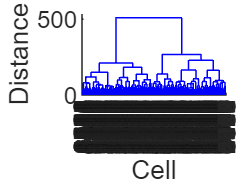

%% CoMベースの活動クラスタリング
%% 1. トライアル分類とタイミング記録、およびETA抽出 (6カテゴリー対応版)
push_pull_separate = 1; % 1: 分ける, 0: 分けない
plot_bayesian = 1; % 1 なら Posterior を表示

if push_pull_separate
    % 6カテゴリー: Pull(1-3), Push(4-6)
    category_names = {'Str-Suc (Pull)', 'Rev-Suc (Pull)', 'Str-Fail (Pull)', ...
                      'Str-Suc (Push)', 'Rev-Suc (Push)', 'Str-Fail (Push)'};
    num_cats = 6;
else
    category_names = {'Straight Success', 'Reversal Success', 'Straight Fail'};
    num_cats = 3;
end
% eta_acts_by_cat = repmat({nan(total_cells, num_time_points)}, 1, num_cats);
eta_acts_by_cat = cell(1, num_cats); 
% current_cell_offset = 0; % どの行から書き込むかのオフセット
pointAreas_all = []; 
% beh_avg_all = cell(num_cats, 3);
beh_all_trials = cell(num_cats, 3);
batch_z_rows = @(m) fillmissing(zscore(m, 0, 2), 'constant', 0);

% 定数設定
fps = 10;
before_event = 1.6; 
after_event = 1.6;  
win_frames = fps * (before_event + after_event) + 1;
pos_thresh_push = 687;  
pos_thresh_pull = 657;  
F_thresh = 16;          
reward_window_ms = 1000; 
raw_center = 672; 
raw_scale = 300/1024; 
radius_mm = 30;

num_time_points = fps * (before_event + after_event) + 1;

for j_animal = 1:length(Animal)
    % --- データロード処理 (既存のパス指定を維持) ---
    if j_animal <=8 
       data_folders(j_animal) = {['E:\Nao_behavior\202506' filesep strjoin(Date(j_animal)) '_' strjoin(Animal(j_animal)) '_' strjoin(Key(j_animal))]};
    else
        data_folders(j_animal) = {['E:\Nao_behavior\202506_Abo' filesep strjoin(Date(j_animal)) '_' strjoin(Animal(j_animal)) '_' strjoin(Key(j_animal))]};
    end    
    load([strjoin(data_folders(j_animal)) filesep strjoin(Animal(j_animal)) '_behavior_' strjoin(Date(j_animal)) '_' strjoin(Key(j_animal)) '.mat']);    
    load([strjoin(data_folders(j_animal)) filesep strjoin(Animal(j_animal)) '_neural_activity_' strjoin(Date(j_animal)) '_' strjoin(Key(j_animal)) '.mat']);    
    t_axis = behavior_neural_time(:,1);
    trial_ids = behavior_neural_time(:,2);
    f_axis = behavior_neural_time(:,7);
    rew_axis = behavior_neural_time(:,8);
    neural_data = acc_neural_activity_data; 
    num_cells = size(neural_data, 2);
    
    % 一時バッファを num_cats に合わせる
    temp_eta = cell(num_cats, num_cells); 
    
    u_trials = unique(trial_ids(trial_ids > 0));
    % 行動データ一時保存用 (カテゴリ x 変数) : 変数1=Pos, 2=Force, 3=Post
    temp_beh = cell(num_cats, 3);    

    for i = 1:length(u_trials)
        t_id = u_trials(i);
        t_idx = find(trial_ids == t_id);
        
        % --- 判定ロジック ---
        pos_trial = behavior_neural_time(t_idx, 6);
        f_trial = f_axis(t_idx);
        
        first_push = find(pos_trial >= pos_thresh_push, 1);
        first_pull = find(pos_trial <= pos_thresh_pull, 1);
        if isempty(first_push) && isempty(first_pull), continue; end
        choice_side = isempty(first_push) || (~isempty(first_pull) && first_pull < first_push); % 1:Pull, 0:Push
        
        end_time = t_axis(t_idx(end));
        post_idx = find(t_axis > end_time & t_axis <= (end_time + 1000));
        is_success = ~isempty(post_idx) && any(rew_axis(post_idx) == 1);
        
        idx_thresh = find(abs(f_trial) > F_thresh, 1);
        if isempty(idx_thresh), continue; end
        initial_side = (f_trial(idx_thresh) > 0);
        is_straight = (initial_side == choice_side);
        
        % 基本カテゴリID (1-3)
        base_cat = 0;
        if is_straight && is_success,      base_cat = 1; % Straight Success
        elseif ~is_straight && is_success, base_cat = 2; % Reversal Success
        elseif is_straight && ~is_success, base_cat = 3; % Straight Fail
        end
        if base_cat == 0, continue; end

        % --- カテゴリIDの確定 (Push/Pull 分離) ---
        if push_pull_separate
            if choice_side == 1 % Pull
                cat_id = base_cat;
            else % Push
                cat_id = base_cat + 3;
            end
        else
            cat_id = base_cat;
        end
 
        % --- アライメント時刻の決定 (最終選択方向への初動) ---
        if base_cat == 2 % Reversal
            if choice_side == 1, idx_t_final = find(f_trial > F_thresh, 1);
            else,                idx_t_final = find(f_trial < -F_thresh, 1);
            end
            if isempty(idx_t_final), continue; end
            abs_event_idx = t_idx(1) + idx_t_final - 1;
        else
            abs_event_idx = t_idx(1) + idx_thresh - 1;
        end
        
        start_f = abs_event_idx - fps*before_event;
        end_f = abs_event_idx + fps*after_event;
        if start_f < 1 || end_f > size(neural_data, 1), continue; end
        
        snippet = neural_data(start_f:end_f, :);
        for c = 1:num_cells
            temp_eta{cat_id, c} = [temp_eta{cat_id, c}; snippet(:, c)'];
        end
        % --- 行動データの切り出し ---
        % =========================================================
        % ハイブリッド抽出: 
        % Pos/Force -> オリジナル(Global Slice)
        % Posterior -> コード1方式(Trial Interpolation + Padding)
        % =========================================================

        % 1. Position & Force (Global Slicing: 生データの連続性を維持)
        % ---------------------------------------------------------
        % Position: mm変換
        pos_window = behavior_neural_time(start_f:end_f, 6);
        pos_mm = (pos_window - raw_center) * raw_scale * (pi / 180) * radius_mm;
        
        % Force: 反転 (-1倍)
        force_window = f_axis(start_f:end_f);
        force_inv = -1 * force_window;

        % 格納 (転置して蓄積)
        % temp_beh{cat_id, 1} = [temp_beh{cat_id, 1}; pos_mm'];
        % temp_beh{cat_id, 2} = [temp_beh{cat_id, 2}; force_inv'];
        beh_all_trials{cat_id, 1} = [beh_all_trials{cat_id, 1}; pos_mm'];
        beh_all_trials{cat_id, 2} = [beh_all_trials{cat_id, 2}; force_inv'];        

        % 2. Posterior (Code 1 Logic: トライアル内データ + 補完)
        % ---------------------------------------------------------
        if plot_bayesian
            % Priorの取得
            if exist('pushCorrect','var')
                init_prior_post = 1 - pushCorrect(t_id); 
            else
                init_prior_post = 0.5;
            end
            
            % トライアル内データのみ取得し、反転 (1 - PullPost)
            post_trial_raw = bayesian_neural_time(t_idx, 9);
            post_inv_trial = 1 - post_trial_raw;

            % 時間軸の作成 (トライアル内相対時間 vs ターゲット窓)
            t_trial_abs = t_axis(t_idx);
            t_event_abs = t_axis(abs_event_idx);
            t_rel = t_trial_abs - t_event_abs;
            
            % ターゲット時間軸 (-before_event : 0.1 : after_event)
            % ※ Slicing側とデータ点数を合わせるため、linspaceや直打ちではなく
            %    start_f:end_f の長さに合わせて生成するのが安全です
            n_points = length(start_f:end_f);
            t_target = linspace(-before_event, after_event, n_points)*1000;

            % % 線形補完 (範囲外は NaN になる)
            post_interp = interp1(t_rel, post_inv_trial, t_target, 'linear');
            
            % --- パディング処理 (Code 1準拠) ---
            % 開始前 (NaN) を Prior (1 - PullPrior) で埋める
            post_interp(isnan(post_interp) & (t_target < min(t_rel))) = 1 - init_prior_post;
            
            % 終了後 (NaN) を最終値で埋める
            post_interp(isnan(post_interp) & (t_target > max(t_rel))) = post_inv_trial(end);
            
            % 補完しきれなかったNaNがあれば(極稀なケース)、直近値で埋める
            post_interp = fillmissing(post_interp, 'nearest');

            % 格納
            % temp_beh{cat_id, 3} = [temp_beh{cat_id, 3}; post_interp];
            beh_all_trials{cat_id, 3} = [beh_all_trials{cat_id, 3}; post_interp];            
        end
    end
    % session_rows = current_cell_offset + (1:num_cells_session);
    for cat = 1:num_cats
        cat_avg = cellfun(@(x) nanmean(x, 1), temp_eta(cat, :), 'UniformOutput', false);
        cat_avg_mat = vertcat(cat_avg{:}); % (num_cells_session x Time)
        % eta_acts_by_cat{cat} = [eta_acts_by_cat{cat}; vertcat(cat_avg{:})];
        % トライアルが1つでもあればデータを代入（なければNaNのまま維持される）
        if ~isempty(cat_avg_mat)
            eta_acts_by_cat{cat} = [eta_acts_by_cat{cat}; cat_avg_mat];
        else
            % データがない（トライアルがない）場合は、NaNの行列を追加して行数を揃える
            % 行数は neural_data の列数（=細胞数）に合わせる
            nan_padding = nan(num_cells, num_time_points);
            eta_acts_by_cat{cat} = [eta_acts_by_cat{cat}; nan_padding];            
        end        
        % for v = 1:3
        %     if isempty(temp_beh{cat, v}), continue; end
        %     beh_avg_all{cat, v} = [beh_avg_all{cat, v}; nanmean(temp_beh{cat, v}, 1)];
        % end
    end
    pointAreas_all = [pointAreas_all; pointAreas(:)];
    % current_cell_offset = current_cell_offset + num_cells_session; % オフセット更新
end

%% 2. クラスタリングと正規化
is_all_nan = cellfun(@(x) all(isnan(x(:))), eta_acts_by_cat);
valid_cats_raw = eta_acts_by_cat(~is_all_nan);
valid_cat_names = category_names(~is_all_nan);
filtered_cats = cell(1, length(valid_cats_raw));

% 行列単位での一括 Z-score 化
for k = 1:length(valid_cats_raw)
    z_data = zscore(valid_cats_raw{k}, 0, 2);
    z_data(isnan(z_data)) = 0; % 定数行対策
    filtered_cats{k} = z_data;
end

data_conc = horzcat(filtered_cats{:});
nan_cells = any(isnan(data_conc), 2);
data_final = data_conc(~nan_cells, :);
pointAreas_final = pointAreas_all(~nan_cells);


linkage_matrix = linkage(data_final, 'ward');
% 樹形図の作成
figure('Position', [100, 100, 800, 600]);
[H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
% title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
xlabel('Cell');
ylabel('Distance');

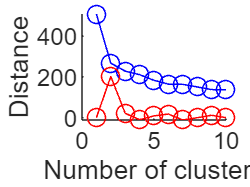


% 順序付けされたdata
ordered_data = data_final(outperm, :);

% エルボー法のためのプロット作成
figure('Position', [100, 100, 800, 600]);
last = linkage_matrix(end-9:end, 3);
last_rev = flipud(last);
indexes = 1:length(last);
hold on
plot(indexes, last_rev, 'b-o');
acceleration = diff(last, 2);  % 2次の微分を計算
acceleration_rev = zeros(10,1);
acceleration_rev(2:end-1) = flipud(acceleration);
plot(indexes, acceleration_rev, 'r-o');
hold off
xlabel('Number of clusters');
ylabel('Distance');

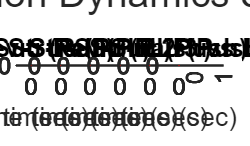

% クラスタリング
num_clusters = 9;
cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);

% プロット設定
%% 3. 可視化 (追加行の実装)
num_beh_rows = 2 + plot_bayesian; % 行動データの行数
total_rows = num_clusters + num_beh_rows;
fig_cols = length(filtered_cats) + 1;

figure('Position', [50, 50, 2400, 1400], 'Color', 'w');
tlo = tiledlayout(total_rows, fig_cols, 'TileSpacing', 'none', 'Padding', 'compact');

for clus = 1:num_clusters
    idx_in_clus = (cluster_labels == clus);
    
    % --- ETA プロット (各カテゴリ) ---
    for cat = 1:length(filtered_cats)
        nexttile;
        curr_cat_data = filtered_cats{cat}(~nan_cells, :);
        cluster_data = curr_cat_data(idx_in_clus, :);
        
        mu = nanmean(cluster_data, 1);
        sd = nanstd(cluster_data, 0, 1);
        x_vec = -before_event:0.1:after_event;
        
        fill([x_vec, fliplr(x_vec)], [mu+sd, fliplr(mu-sd)], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
        hold on;
        plot(x_vec, mu, 'b', 'LineWidth', 1.5);
        xline(0, 'r-'); ylim([-2 2]);
        
        if clus == 1, title(category_names{cat}); end
        if cat == 1, ylabel(sprintf('Clus %d', clus), 'FontWeight', 'bold'); end
    end
    
    % --- 層割合プロット (最終列) ---
    nexttile;
    clus_layers = pointAreas_final(idx_in_clus);
    n_l23 = sum(clus_layers == 1);
    n_l5 = sum(clus_layers == 0);
    total = length(clus_layers);
    
    % 横棒グラフ (L2/3=緑, L5=青)
    h_bar = barh(1, [n_l23/total, n_l5/total], 'stacked');
    h_bar(1).FaceColor = [0 0.7 0];     % 緑 (L2/3)
    h_bar(2).FaceColor = [0 0.4 0.8];   % 青 (L5)
    set(h_bar, 'EdgeColor', 'none');
    xlim([0 1]); set(gca, 'YTick', [], 'XTick', [0 1]);
    if clus == 1, title('L2/3 vs L5'); end
    text(0.1, 1, sprintf('L2/3:%d', n_l23), 'Color', 'w', 'FontSize', 8);
    text(0.7, 1, sprintf('L5:%d', n_l5), 'Color', 'w', 'FontSize', 8);
end

% --- B. Behavioral Dynamics Rows (追加部分) ---
beh_labels = {'Position (mm)', 'Force (mN)', 'P(Push)'};
ylims_beh = {[-5.5, 5.5], [-64, 64], [-0.1, 1.1]};
x_vec = linspace(-before_event, after_event, size(beh_all_trials{1,1}, 2));
for v = 1:num_beh_rows
    for k = 1:length(filtered_cats)
        nexttile;
        % 全個体平均データの取得
        % filtered_cats に合わせた有効なカテゴリインデックスを使用
        valid_cat_idx = find(~is_all_nan);
        curr_beh_data = beh_all_trials{valid_cat_idx(k), v}; %beh_avg_all{valid_cat_idx(k), v};
        
        mu = nanmean(curr_beh_data, 1);
        sd = nanstd(curr_beh_data, 0, 1);
        % x_vec = -before_event:0.1:after_event;
        
        fill([x_vec, fliplr(x_vec)], [mu+sd, fliplr(mu-sd)], [0.5 0.5 0.5], 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        hold on;
        plot(x_vec, mu, 'k', 'LineWidth', 1.5);
        xline(0, 'r-');
        ylim(ylims_beh{v});
        if k == 1, ylabel(beh_labels{v}, 'FontWeight', 'bold'); end
        if v == num_beh_rows, xlabel('time (sec)'); end
    end
    % 最終列の余白埋め
    nexttile; axis off;
end

sgtitle('Clustering by Decision Dynamics & Layer Distribution');
filename_cluster = [output_dir 'cluster_behavior_ratio_layer.png'];
saveas(gcf, filename_cluster);

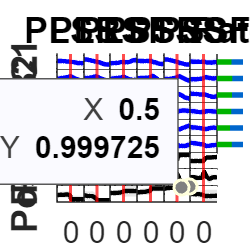

% plot for FENS 2026 meeting abstract
% --- プロット設定 ---
num_clusters = 6;
cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
col_titles = {'PLSS', 'PLRS', 'PLSF', 'PSSS', 'PSRS', 'PSSF', 'Rate'};
num_beh_rows = 2 + plot_bayesian; 
total_rows = num_clusters + num_beh_rows;
fig_cols = length(filtered_cats) + 1;

% フォントサイズの設定（400pxに対して相対的に大きく設定）
fs_label = 12;  % 軸ラベル・タイトル
fs_tick = 10;   % 目盛り
fs_text = 10;   % バーの中の数字

% 1. フィギュアの作成（400x400ピクセルに固定）
% 'Units'を'pixels'に指定して正確なサイズに設定
fig = figure('Units', 'pixels', 'Position', [100, 100, 400, 400], 'Color', 'w');

% タイルレイアウト：余白(Padding)と間隔(Spacing)をゼロにしてグラフを最大化
tlo = tiledlayout(total_rows, fig_cols, 'TileSpacing', 'none', 'Padding', 'none');

for clus = 1:num_clusters
    idx_in_clus = (cluster_labels == clus);
    
    % --- ETA プロット (各カテゴリ) ---
    for cat = 1:length(filtered_cats)
        ax = nexttile;
        curr_cat_data = filtered_cats{cat}(~nan_cells, :);
        cluster_data = curr_cat_data(idx_in_clus, :);
        
        mu = nanmean(cluster_data, 1);
        sd = nanstd(cluster_data, 0, 1);
        x_vec = -before_event:0.1:after_event;
        
        fill([x_vec, fliplr(x_vec)], [mu+sd, fliplr(mu-sd)], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
        hold on;
        plot(x_vec, mu, 'b', 'LineWidth', 1.5);
        xline(0, 'r-', 'LineWidth', 1); 
        xlim([-1.6, 1.6]);
        ylim([-2.5 2.5]);
        box off; % グラフのボックス（枠線）を削除
        set(gca, 'FontSize', fs_tick, 'TickDir', 'out');
        
        % ラベルは左端と下端のみ表示してスペースを節約
        set(gca, 'YTickLabel', []);
        % if cat ~= 1, set(gca, 'YTickLabel', []); end
        if clus == 1
            title(col_titles{cat}, 'FontSize', fs_label, 'FontWeight', 'bold');
        end        
        if clus ~= total_rows, set(gca, 'XTickLabel', []); end
        if cat == 1, ylabel(sprintf('C%d', clus), 'FontSize', fs_label, 'FontWeight', 'bold'); end
    end
    
    % --- 層割合プロット (最終列) ---
    ax_bar = nexttile;
    clus_layers = pointAreas_final(idx_in_clus);
    n_l23 = sum(clus_layers == 1);
    n_l5 = sum(clus_layers == 0);
    total = length(clus_layers);
    
    h_bar = barh(1, [n_l23/total, n_l5/total], 'stacked');
    h_bar(1).FaceColor = [0 0.7 0]; % L2/3: 緑
    h_bar(2).FaceColor = [0 0.4 0.8]; % L5: 青
    set(h_bar, 'EdgeColor', 'none');
    
    xlim([0 1]); axis off; % バーチャートは軸ごと消してボックスを排除
    if clus == 1
        title(col_titles{end}, 'FontSize', fs_label, 'FontWeight', 'bold');
    end        
    % バー内の文字を拡大
    % text(0.1, 1, num2str(n_l23), 'Color', 'w', 'FontSize', fs_text, 'FontWeight', 'bold');
    % text(0.7, 1, num2str(n_l5), 'Color', 'w', 'FontSize', fs_text, 'FontWeight', 'bold');
end

% --- B. Behavioral Dynamics Rows (下部) ---
beh_labels = {'Pos', 'For', 'Post'}; % 短い名前に変更してスペース節約
ylims_beh = {[-5.5, 5.5], [-64, 64], [-0.1, 1.1]};
x_vec = linspace(-before_event, after_event, size(beh_all_trials{1,1}, 2));

for v = 1:num_beh_rows
    for k = 1:length(filtered_cats)
        ax_beh = nexttile;
        valid_cat_idx = find(~is_all_nan);
        curr_beh_data = beh_all_trials{valid_cat_idx(k), v};
        
        mu = nanmean(curr_beh_data, 1);
        sd = nanstd(curr_beh_data, 0, 1);
        
        fill([x_vec, fliplr(x_vec)], [mu+sd, fliplr(mu-sd)], [0.5 0.5 0.5], 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x_vec, mu, 'k', 'LineWidth', 1.5);
        xline(0, 'r-', 'LineWidth', 1);
        xlim([-1.6, 1.6]);
        ylim(ylims_beh{v});
        box off; % ボックス削除
        set(gca, 'FontSize', fs_tick);
        
        set(gca, 'YTickLabel', []);
        % if k ~= 1, set(gca, 'YTickLabel', []); end
        if (clus + v) ~= total_rows, set(gca, 'XTickLabel', []); end
        if k == 1, ylabel(beh_labels{v}, 'FontSize', fs_label, 'FontWeight', 'bold'); end
    end
    nexttile; axis off; % 層割合列の延長線を消去
end

% 保存時にサイズが変わらないように設定
filename_cluster = [output_dir 'cluster_400px.png'];
exportgraphics(fig, filename_cluster, 'Resolution', 72); % 72dpiで400pxを維持

% % Plot ETA heatmap of Kota (pull) timing alignment of each condition
% % AlinmentTimingCells
% title_list = {'High - Low value'}; %{'Heavy - Light', 'Exp heavy - Unexp heavy', 'Exp light - Unexp light', 'Exp heavy - Unexp heavy - Exp light - Unexp light'};
% fig_y = 400*num_clusters;
% % fig_y = 600*num_clusters;
% figure('Position', [100, 100, fig_y, 600]);
% % figure('Position', [100, 100, 1600, fig_y]);
% % for i = 1:4
% %     % NaNを含む行を削除
% %     if i == 1
% %         data1 = pull_actss{1}; data2 = pull_actss{2};
% %     elseif i == 4
% %         data1 = pull_actss{3}; data2 = pull_actss{5};   
% %         data3 = pull_actss{4}; data4 = pull_actss{6};
% %     else
% %         data1 = pull_actss{i+1}; data2 = pull_actss{i+3};
% %     end        
%     % i_data = pull_actss{i};
%     % i_data = i_data(~any(isnan(data), 2), :);
% data1 = eta_acts_conc{5};data2 = eta_acts_conc{6};
% for cluster_num = 1:num_clusters
%     subaxis(1,num_clusters,cluster_num, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);            
%     % subaxis(num_clusters,4,i+4*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
% 
%     cluster_data1 = data1(cluster_labels == cluster_num, :); cluster_data2 = data2(cluster_labels == cluster_num, :);
%     cluster_data1 = cluster_data1(~any(isnan(cluster_data1), 2), :); cluster_data2 = cluster_data2(~any(isnan(cluster_data2), 2), :);
% 
%     mean_values1 = mean(cluster_data1, 1); mean_values2 = mean(cluster_data2, 1);
%     std_values1 = std(cluster_data1, 0, 1); std_values2 = std(cluster_data2, 0, 1);
% 
%     x = -before_event:0.1:after_event;
% 
%     % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     hold on;
%     plot(x, mean_values1, 'Color', [0 0.6 0], 'LineWidth', L_width); 
%     % plot(x, mean_values1, 'Color', 'k', 'LineWidth', 1.5); 
%     % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     plot(x, mean_values2, 'Color', [0.6 0.8 0.2], 'LineWidth', L_width); 
%     % plot(x, mean_values2, 'Color', [0.5 0.5 0.5], 'LineWidth', 1.5); 
% 
%     % fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     % hold on;
%     % plot(x, mean_values, 'b', 'LineWidth', 1.5); 
%     % if i == 1
%     %     % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     hold on;
%     %     plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
%     %     % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     plot(x, mean_values2, 'c', 'LineWidth', 1.5); 
%     % elseif i == 2
%     %     % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     hold on;
%     %     plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
%     %     % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
%     % elseif i == 3
%     %     % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     hold on;
%     %     plot(x, mean_values1, 'c', 'LineWidth', 1.5); 
%     %     % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     plot(x, mean_values2, 'c', 'LineWidth', 1.5,'LineStyle', ':');             
%     % else
%     %     % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     hold on;
%     %     plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
%     %     % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
%     %     % fill([x, fliplr(x)], [mean_values3 + std_values3, fliplr(mean_values3 - std_values3)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     plot(x, mean_values3, 'c', 'LineWidth', 1.5); 
%     %     % fill([x, fliplr(x)], [mean_values4 + std_values4, fliplr(mean_values4 - std_values4)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     %     plot(x, mean_values4, 'c', 'LineWidth', 1.5,'LineStyle', ':');            
%     % end            
%     if norm ~= 0
%         plot([0 0], [-100,100], 'r-', 'LineWidth', L_width); % x=0 に赤い縦線を描画     
%     else
%         yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
%         plot([0 0], yLimits, 'r-', 'LineWidth', L_width); % x=0 に赤い縦線を描画
%     end
%     hold off;
%     if cluster_num == 1
%     % if i == 1
%         ylabel('normalized activity');
%     end
%     if i == 4
%     % if cluster_num == num_clusters
%         xlabel('time (sec)');
%     end
%     % if cluster_num == 1
%     %     title(title_list{i});
%     % end
%      axis tight;
%     if norm ~= 0 & norm ~= 6
%         ylim([-2 2]);  
%     elseif norm == 6
%         ylim([-4 12]);%ylim([-6 24]); 
%     end
% end
% 
% % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_eta_activity_compare.png'];
% filename = [output_dir 'clustered_pull_eta_conc_activity_compare.png'];
% saveas(gcf,filename);
% % close all;

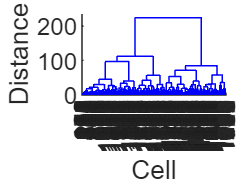

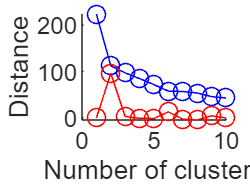

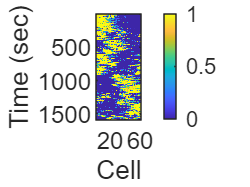

% Layer23 階層的クラスタリングの実施

if strcmp(categorize, 'layer') == 1
    % NaNを含む行を削除
    data = eta_layer23_acts_conc{length(eta_layer23_acts_conc)};
    data = data(~any(isnan(data), 2), :);
    % 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
    linkage_matrix = linkage(data, 'ward');
    
    % 樹形図の作成
    figure('Position', [100, 100, 800, 600]);
    [H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
    % title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
    xlabel('Cell');
    ylabel('Distance');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_hierarchical_clustering_dendrogram.png'];
    filename = [output_dir 'layer23_hierarchical_clustering_dendrogram_eta_conc.png'];
    saveas(gcf,filename);    
    
    % 順序付けされたdata
    ordered_data = data(outperm, :);
    
    % エルボー法のためのプロット作成
    figure('Position', [100, 100, 800, 600]);
    last = linkage_matrix(end-9:end, 3);
    last_rev = flipud(last);
    indexes = 1:length(last);
    hold on
    plot(indexes, last_rev, 'b-o');
    acceleration = diff(last, 2);  % 2次の微分を計算
    acceleration_rev = zeros(10,1);
    acceleration_rev(2:end-1) = flipud(acceleration);
    plot(indexes, acceleration_rev, 'r-o');
    hold off
    xlabel('Number of clusters');
    ylabel('Distance');
    % title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_elbow.png'];
    filename = [output_dir 'layer23_elbow_eta_conc.png']; 
    saveas(gcf,filename);     
    
    % 相関行列の表示
    figure('Position', [100, 100, 800, 600]);
    imagesc(ordered_data, [0 1]);
    colorbar;
    % title(title_list{i});  %title('Correlation Matrix');
    xlabel('Cell');
    ylabel('Time (sec)');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_eta_heatmap2.png'];
    filename = [output_dir 'layer23_eta_conc_heatmap2.png'];
    saveas(gcf,filename);         
        % colormap('viridis');
    % end
end

Element 1: 144 cells
Element 2: 270 cells
Element 3: 262 cells
Element 4: 198 cells
Element 5: 397 cells
Element 6: 321 cells


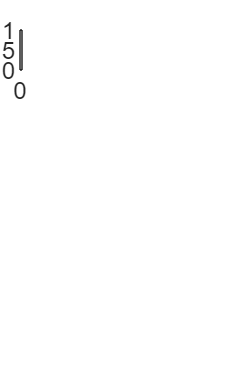

Error using fill
Vectors must be the same length.

% plot clustered ETA neural activity
if strcmp(categorize, 'layer') == 1
    num_clusters = 6; % クラスター数を指定（必要に応じて変更）
    % クラスタリングの実行
    cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
    unique_elements = unique(cluster_labels);
    counts = histc(cluster_labels, unique_elements);
    for n = 1:length(unique_elements)
        fprintf('Element %d: %d cells\n', unique_elements(n),counts(n));
    end
    title_list = {'Reward', 'Reward miss', 'push_trial_push_prob_block', 'push_trial_pull_prob_block', 'pull_trial_push_prob_block', 'pull_trial_pull_prob_block',...
        'push_trial_push_value_block','push_trial_pull_value_block','pull_trial_push_value_block','pull_trial_pull_value_block',...
        'push_trial_push_prob_block','push_trial_pull_prob_block','pull_trial_push_prob_block','pull_trial_pull_prob_block',...
        'push_trial_push_value_block','push_trial_pull_value_block','pull_trial_push_value_block','pull_trial_pull_value_block'};
    % title_list = {'Reward', 'Reward miss', 'Force usual resistance', 'Force rare resistance', 'Force high reward', 'Force low reward'};

    fig_y = 600*num_clusters;
    figure('Position', [100, 100, 2400, fig_y]);
    for i = 1:length(eta_layer23_acts_conc)
        % NaNを含む行を削除
        i_data = eta_layer23_acts_conc{i};
        % i_data = i_data(~any(isnan(i_data), 2), :);
        % % hierarchical clustering
        % linkage_matrix = linkage(data, 'ward');
        % % クラスタリングの実行
        % cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
        for cluster_num = 1:num_clusters
            subaxis(num_clusters,length(eta_layer23_acts_conc),i+length(eta_layer23_acts_conc)*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data = i_data(cluster_labels == cluster_num, :);
            cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);
            z = zscore(cluster_data, 0, 1); % 列方向に Zスコアを計算
            cluster_data = cluster_data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

            mean_values = mean(cluster_data, 1);
            std_values = std(cluster_data, 0, 1);
            x = -before_event:0.1:after_event;
          
            fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values, 'g', 'LineWidth', 1.5); 
            % xlim = [-2,4]
            % x=0に赤い縦線をプロット       
            % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if i == 1
                ylabel('normalized activity');
            end
            if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            if cluster_num == 1
                title(title_list{i});
            end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 24]); %ylim([-6 12]);
            end
        end
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_layer23_eta_activity.png'];
    filename = [output_dir 'clustered_layer23_eta_conc_activity.png'];
    saveas(gcf,filename);
    close all;
end

% Layer5 階層的クラスタリングの実施

if strcmp(categorize, 'layer') == 1
    % NaNを含む行を削除
    data = eta_layer5_acts_conc{length(eta_layer5_acts_conc)};
    data = data(~any(isnan(data), 2), :);
    % 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
    linkage_matrix = linkage(data, 'ward');
    
    % 樹形図の作成
    figure('Position', [100, 100, 800, 600]);
    [H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
    % title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
    xlabel('Cell');
    ylabel('Distance');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_hierarchical_clustering_dendrogram.png'];
    filename = [output_dir 'layer5_hierarchical_clustering_dendrogram_eta_conc.png'];
    saveas(gcf,filename);    
    
    % 順序付けされたdata
    ordered_data = data(outperm, :);
    
    % エルボー法のためのプロット作成
    figure('Position', [100, 100, 800, 600]);
    last = linkage_matrix(end-9:end, 3);
    last_rev = flipud(last);
    indexes = 1:length(last);
    hold on
    plot(indexes, last_rev, 'b-o');
    acceleration = diff(last, 2);  % 2次の微分を計算
    acceleration_rev = zeros(10,1);
    acceleration_rev(2:end-1) = flipud(acceleration);
    plot(indexes, acceleration_rev, 'r-o');
    hold off
    xlabel('Number of clusters');
    ylabel('Distance');
    % title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_elbow.png'];
    filename = [output_dir 'layer5_elbow_conc.png'];
    saveas(gcf,filename);     
    
    % 相関行列の表示
    figure('Position', [100, 100, 800, 600]);
    imagesc(ordered_data, [0 1]);
    colorbar;
    % title(title_list{i});  %title('Correlation Matrix');
    xlabel('Cell');
    ylabel('Time (sec)');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_eta_heatmap2.png'];
    filename = [output_dir 'layer5_eta_conc_heatmap2.png'];
    saveas(gcf,filename);         
        % colormap('viridis');
    % end
end

% plot clustered ETA neural activity
if strcmp(categorize, 'layer') == 1
    num_clusters = 2; % クラスター数を指定（必要に応じて変更）
    % クラスタリングの実行
    cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
    unique_elements = unique(cluster_labels);
    counts = histc(cluster_labels, unique_elements);
    for n = 1:length(unique_elements)
        fprintf('Element %d: %d cells\n', unique_elements(n),counts(n));
    end

    title_list = {'Reward', 'Reward miss', 'push_trial_push_prob_block', 'push_trial_pull_prob_block', 'pull_trial_push_prob_block', 'pull_trial_pull_prob_block',...
        'push_trial_push_value_block','push_trial_pull_value_block','pull_trial_push_value_block','pull_trial_pull_value_block',...
        'push_trial_push_prob_block','push_trial_pull_prob_block','pull_trial_push_prob_block','pull_trial_pull_prob_block',...
        'push_trial_push_value_block','push_trial_pull_value_block','pull_trial_push_value_block','pull_trial_pull_value_block'};
    % title_list = {'Reward', 'Reward miss', 'Force usual resistance', 'Force rare resistance', 'Force high reward', 'Force low reward'};

    fig_y = 600*num_clusters;
    figure('Position', [100, 100, 2400, fig_y]);
    for i = 1:length(eta_layer5_acts_conc)
        % NaNを含む行を削除
        i_data = eta_layer5_acts_conc{i};
        % i_data = i_data(~any(isnan(i_data), 2), :);
        % % hierarchical clustering
        % linkage_matrix = linkage(data, 'ward');
        % % クラスタリングの実行
        % cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
        for cluster_num = 1:num_clusters
            subaxis(num_clusters,length(AlinmentTimingCells),i+length(AlinmentTimingCells)*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data = i_data(cluster_labels == cluster_num, :);
            cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);
            z = zscore(cluster_data, 0, 1); % 列方向に Zスコアを計算
            cluster_data = cluster_data(max(abs(z), [], 2) < 10, :); % Zスコアが100以上の行を除去

            mean_values = mean(cluster_data, 1);
            std_values = std(cluster_data, 0, 1);
            x = -before_event:0.1:after_event;
          
            fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values, 'b', 'LineWidth', 1.5); 
            % xlim = [-2,4]
            % x=0に赤い縦線をプロット       
            % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if i == 1
                ylabel('normalized activity');
            end
            if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            if cluster_num == 1
                title(title_list{i});
            end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 24]); %ylim([-6 12]);
            end
        end
    end
        
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_layer5_eta_activity.png'];
    filename = [output_dir 'clustered_pull_layer5_eta_conc_activity.png'];
    saveas(gcf,filename);
    % close all;
end

% check the ratio of cells in each layer in each cluster
% all_cluster_labels
% pointAreas_conc

unique_pairs = unique([all_cluster_labels, pointAreas_filtered], 'rows');
% unique_pairs = unique([all_cluster_labels, pointAreas_conc], 'rows');
counts = zeros(size(unique_pairs, 1), 1);

for i = 1:size(unique_pairs, 1)
    counts(i) = sum(ismember([all_cluster_labels, pointAreas_filtered], unique_pairs(i, :), 'rows'));
    % counts(i) = sum(ismember([all_cluster_labels, pointAreas_conc], unique_pairs(i, :), 'rows'));
end

for i = 1:size(unique_pairs, 1)
    fprintf('Pair (%d, %d): %d times\n', unique_pairs(i, 1), unique_pairs(i, 2), counts(i));
end



% ユニークな要素を見つける
unique_list2 = unique(pointAreas_filtered);
% unique_list2 = unique(pointAreas_conc);

% Figureの作成
figure('Position', [100, 100, 2400, 600]);

% 各カテゴリーごとにプロット
num_categories = length(unique_list2);
for i = 1:num_categories
    category = unique_list2(i);
    indices = pointAreas_filtered == category;    
    % indices = pointAreas_conc == category;
    subset_list1 = all_cluster_labels(indices);
    
    % List1のカテゴリーの割合を計算
    unique_subset_list1 = unique(subset_list1);
    counts = histc(subset_list1, unique_subset_list1);
    percentages = counts / sum(counts) * 100;
    
    % 円グラフをプロット
    subplot(1, num_categories, i);
    % pie(percentages, arrayfun(@num2str, unique_subset_list1, 'UniformOutput', false));
    pie(percentages, arrayfun(@(x) [num2str(counts(x == unique_subset_list1)) ' - ' num2str(round(percentages(x == unique_subset_list1), 2)) '%'], unique_subset_list1, 'UniformOutput', false));
    legend(arrayfun(@num2str, unique_subset_list1, 'UniformOutput', false), 'Location', 'southoutside', 'Orientation', 'horizontal');    
    if category == 0
        title(['Layer 5']);
    else
        title(['Layer 23']);
    end
end

% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer235_cluster_percentage.png'];
 filename = [output_dir 'layer235_cluster_percentage_eta_conc.png'];
saveas(gcf,filename);

%TODO: make muliple dimention reduction map
% % Dimention reduction using PCA, tSNE and UMAP
% comp_pca = pca(acc_neural_activity_data);
% comp_tsne = tsne(transpose(acc_neural_activity_data));

% figure
% scatter(comp_pca(:,1),comp_pca(:,2));
% xlabel('PC1');
% ylabel('PC2');

% figure
% scatter(comp_tsne(:,1),comp_tsne(:,2));
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');

% if categorize == 'layer'
%     colorcode = pointAreas;
% end
% if categorize == 'depth'
%     colorcode = depth
% end

% % Color hidden dimention by depth of cells
% figure
% % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
% xlabel('PC1');
% ylabel('PC2');
% if categorize == 'depth'
%     colormap(flipud(colormap));
%     colorbar('Direction','reverse');
%     caxis([0 1100]);
% end
% filename = [output_dir Date '_'  Animal, '_' categorize '_all_activity_PCA.png'];
% saveas(gcf,filename);

% figure
% % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); % ,depth,'filled');
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');
% if categorize == 'depth'
%     colormap(flipud(colormap));
%     colorbar('Direction','reverse');
%     caxis([0 1100]);
% end
% filename = [output_dir Date '_'  Animal, '_' categorize '_all_activity_tSNE.png'];
% saveas(gcf,filename);

% Dimention reduction of trial_start_Act using PCA and tSNE 
comp_pca = pca(transpose(trial_start_act_conc));
comp_tsne = tsne(trial_start_act_conc);
if categorize == 'layer'
    colorcode = startAreas;
end
if categorize == 'depth'
    colorcode = startDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_trial_start_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_trial_start_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,trial_start_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_start_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,trial_start_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_start_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of trial_end_Act using PCA and tSNE 
comp_pca = pca(transpose(trial_end_act_conc));
comp_tsne = tsne(trial_end_act_conc);
if categorize == 'layer'
    colorcode = endAreas;
end
if categorize == 'depth'
    colorcode = endDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_trial_end_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_trial_end_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,trial_end_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_end_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,trial_end_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_end_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of position_act using PCA and tSNE 
comp_pca = pca(transpose(position_act_conc));
comp_tsne = tsne(position_act_conc);
if categorize == 'layer'
    colorcode = posAreas;
end
if categorize == 'depth'
    colorcode = posDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_position_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_position_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,position_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_position_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,position_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_position_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of force_Act using PCA and tSNE 
comp_pca = pca(transpose(force_act_conc));
comp_tsne = tsne(force_act_conc);
if categorize == 'layer'
    colorcode = forceAreas;
end
if categorize == 'depth'
    colorcode = forceDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_force_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_force_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,force_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_force_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,force_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_force_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of reward_Act using PCA and tSNE 
comp_pca = pca(transpose(reward_act_conc));
comp_tsne = tsne(reward_act_conc);
if categorize == 'layer'
    colorcode = rewardAreas;
end
if categorize == 'depth'
    colorcode = rewardDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_reward_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_reward_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,reward_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_reward_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,reward_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_reward_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% layer specific dimention reduced neural activity timecourse

% layer23_act = [trial_start_act_layer23_cells, trial_end_act_layer23_cells, position_act_layer23_cells, force_act_layer23_cells, reward_act_layer23_cells];
% layer5_act  = [trial_start_act_layer5_cells, trial_end_act_layer5_cells, position_act_layer5_cells, force_act_layer5_cells, reward_act_layer5_cells];

% Dimention reduction of reward_Act using PCA and tSNE 

% Color hidden dimention by depth of cells
autumn = colormap('autumn');
winter = colormap('winter');
scaled_autumn_colors = interp1(linspace(1,size(layer23_act_conc{1},2),size(autumn,1)),autumn, 1:size(layer23_act_conc{1},2));
scaled_winter_colors = interp1(linspace(1,size(layer23_act_conc{1},2),size(winter,1)),winter, 1:size(layer23_act_conc{1},2));
figure
for i = 1:length(layer5_act_conc) 
    layer23_comp_pca = pca(layer23_act_conc{i});
    layer5_comp_pca = pca(layer5_act_conc{i});
    subaxis(length(layer5_act_conc),2,2*(i-1)+1, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
    scatter(layer23_comp_pca(:,1),layer23_comp_pca(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
    title(title_list{i});
    ylabel('PC2');
    if i == 5
        xlabel('PC1');
    end
    subaxis(length(layer5_act_conc),2,2*i, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    scatter(layer5_comp_pca(:,1),layer5_comp_pca(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
    title(title_list{i});
    colormap(flipud(colormap));
    % colorbar('Direction','reverse');
    % caxis([0 1100]);
end
xlabel('PC1');
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_eta_PCA_timecourse.png'];
saveas(gcf,filename);

figure
for i = 1:length(layer5_act_conc) 
    layer23_comp_tsne = tsne(transpose(layer23_act_conc{i}));
    layer5_comp_tsne = tsne(transpose(layer5_act_conc{i}));
    subaxis(length(layer5_act_conc),2,2*(i-1)+1, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
    scatter(layer23_comp_tsne(:,1),layer23_comp_tsne(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
    title(title_list{i});
    ylabel('t-SNE coordinate2');
    if i == 5
        xlabel('t-SNE coordinate1');
    end
    subaxis(length(layer5_act_conc),2,2*i, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    scatter(layer5_comp_tsne(:,1),layer5_comp_tsne(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
    title(title_list{i});
%     xlabel('t-SNE coordinate1');
%     ylabel('t-SNE coordinate2');
    colormap(flipud(colormap));
%     colorbar('Direction','reverse');
%     caxis([0 1100]);
end
xlabel('t-SNE coordinate1');
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' categorize '_eta_tSNE_timecourse.png'];
saveas(gcf,filename);


% % Clustering neural activity
% [idx,C] = kmeans(transpose(acc_neural_property_data),3);
% x1 = min(comp_tsne(:,1)):0.01:max(comp_tsne(:,1));
% x2 = min(comp_tsne(:,2)):0.01:max(comp_tsne(:,2));
% [x1G,x2G] = meshgrid(x1,x2);
% XGrid = [x1G(:),x2G(:)];
% idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start','c');
% 
% figure;
% gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
%     [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
% hold on;
% % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,depth,'filled');
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');
% colormap(flipud(colormap));
% colorbar('Direction','reverse');
% caxis([0 1100]);
% hold off;

% Example usage
% points = [1, 2; 3, 4; 5, 6]; % Nx2 array of points to classify
% linePoints = [0, 0; 2, 2; 3, 1]; % 3x2 array of points defining the first line
% 
% pointAreas = classifyPoints(points, linePoints);
% disp(pointAreas);

function normalized_matrix = normalize_rows(matrix)
    min_values = min(matrix, [], 2);
    max_values = max(matrix, [], 2);
    range = max_values - min_values;
    normalized_matrix = (matrix - min_values) ./ range;
end

function zscored_matrix = zscore_rows(matrix)
    zscored_matrix = (matrix - mean(matrix, 2)) ./ std(matrix,0,2);
end

function zscored_matrix2 = zscore_rows_by_diff_matrix(matrix1, matrix2)
    zscored_matrix2 = (matrix1 - mean(matrix2, 2)) ./ std(matrix2,0,2);
end

function zscored_matrix3 = zscore_rows_by_before_pull(matrix)
    zscored_matrix3 = (matrix - mean(matrix(:,1:20), 2)) ./ std(matrix(:,1:20),0,2);
end

function pointAreas = classifyPoints(points, linePoints)
    % TODO: chack this function work correct or not.

    % points: Nx2 array of points to classify
    % linePoints: 3x2 array of points defining the line
    % pointAreas: Nx1 array indicating the area for each point (low:0 or high:1)

    % Iterate through each point and classify it based on cross products
    pointAreas = zeros(size(points, 1), 1);
    for i = 1:size(points, 1)
        point = points(i, :);
        
        % Determine which side of the lines the point is on
        % classify points based on X coordinate
        if point(1) < linePoints(2,1)
            slope = (linePoints(2,2)-linePoints(1,2))/(linePoints(2,1)-linePoints(1,1));
            intercept = linePoints(1,2) - slope*linePoints(1,1);
        else
            slope = (linePoints(3,2)-linePoints(2,2))/(linePoints(3,1)-linePoints(2,1));
            intercept = linePoints(2,2) - slope*linePoints(2,1);        
        end
        lineY = slope*point(1) + intercept;
        pointAreas(i) = point(2) > lineY;
    end
end

% % ANOVAとTukeyテストを実施する関数
% function perform_anova_tukey(data1, data2, data3, data4)
%     % データを縦に結合し、グループラベルを作成
%     data = [data1(:, 21:61); data2(:, 21:61); data3(:, 21:61); data4(:, 21:61)];
%     group = [repmat({'Group1'}, size(data1, 1), 1); ...
%              repmat({'Group2'}, size(data2, 1), 1); ...
%              repmat({'Group3'}, size(data3, 1), 1); ...
%              repmat({'Group4'}, size(data4, 1), 1)];
% 
%     % ANOVAを実行
%     p = anova1(data, group, 'off');
%     disp(['ANOVA p-value: ', num2str(p)]);
% 
%     % TukeyのHSD検定を実行
%     [c, m, h, nms] = multcompare(stats, 'CType', 'tukey-kramer');
%     disp('Tukey HSD test results:');
%     disp(c);
% end

function perform_anova_tukey(data1, data2, data3, data4, tk_mean)
    % データを縦に結合し、グループラベルを作成
    if tk_mean
        data1 = mean(data1(:, 21:61), 2);
        data2 = mean(data2(:, 21:61), 2);
    else
        data1 = data1(:, 21:61);
        data2 = data2(:, 21:61);
    end
    
    % データを1列にまとめ、グループラベルを作成
    if ~isempty(data3) && ~isempty(data4)
        if tk_mean
            data3 = mean(data3(:, 21:61), 2);
            data4 = mean(data4(:, 21:61), 2);
        else
            data3 = data3(:, 21:61);
            data4 = data4(:, 21:61);
        end
        data = [data1(:); data2(:); data3(:); data4(:)];
        group = [repmat({'Group1'}, numel(data1), 1); ...
                 repmat({'Group2'}, numel(data2), 1); ...
                 repmat({'Group3'}, numel(data3), 1); ...
                 repmat({'Group4'}, numel(data4), 1)];
    else
        data = [data1(:); data2(:)];
        group = [repmat({'Group1'}, numel(data1), 1); ...
                 repmat({'Group2'}, numel(data2), 1)];
    end
         
    % ANOVAを実行
    [p, tbl, stats] = anova1(data, group, 'off');
    disp(['ANOVA p-value: ', num2str(p)]);
    
    % TukeyのHSD検定を実行
    if p < 0.05
        [c, m, h, nms] = multcompare(stats, 'CType', 'tukey-kramer', 'Display', 'off');
        disp('Tukey HSD test results:');
        disp(c);
    end
end

function perform_welch_bonferroni(data1, data2, data3, data4)
    % データを縦に結合し、グループラベルを作成
    data1 = data1(:, 21:61);
    data2 = data2(:, 21:61);
    
    % データを1列にまとめ、グループラベルを作成
    if ~isempty(data3) && ~isempty(data4)
        data3 = data3(:, 21:61);
        data4 = data4(:, 21:61);
        data = {data1(:), data2(:), data3(:), data4(:)};
        group = {'Group1', 'Group2', 'Group3', 'Group4'};
    else
        data = {data1(:), data2(:)};
        group = {'Group1', 'Group2'};
    end
    
    % グループ数を取得
    numGroups = length(data);
    
    % グループ間のペアのインデックスを作成
    pairIndices = nchoosek(1:numGroups, 2);
    numPairs = size(pairIndices, 1);
    
    % 各ペアに対してウェルチのT検定を実行し、p値を取得
    pValues = zeros(numPairs, 1);
    for i = 1:numPairs
        group1 = data{pairIndices(i, 1)};
        group2 = data{pairIndices(i, 2)};
        [~, p] = ttest2(group1, group2, 'Vartype', 'unequal');
        pValues(i) = p;
    end
    
    % Bonferroni補正を実行
    correctedPValues = pValues * numPairs;
    correctedPValues(correctedPValues > 1) = 1; % p値は最大でも1
    
    % 結果を表示
    disp('Pairwise Welch t-test results with Bonferroni correction:');
    for i = 1:numPairs
        disp(['Comparison ', group{pairIndices(i, 1)}, ' vs ', group{pairIndices(i, 2)}, ...
              ': p-value = ', num2str(correctedPValues(i))]);
    end
end